# Image Processing Operator Approximation Using Deep Learning

Example from [mathworks.com](https://se.mathworks.com/help/images/image-processing-operator-approximation-using-deep-learning.html).

## Imports

For the bilateralFilterDataset function.

%import imbilatfilt
%import imwrite

## Set parameters

patch_size_x = 32;
patch_size_y = 32;

## Directories

%imagesDir = tempdir;
imagesDir = 'D:\Projects\MasterThesis\Salsa_cryptanalysis\matlab\crypto_images\'

imagesDir = 'D:\Projects\MasterThesis\Salsa_cryptanalysis\matlab\crypto_images\'

subDir = 'images\'

subDir = 'images\'

% Add/remove '_small' at the end of images/preprocessedDataset, to
% make the dataset small (1000) or large (20000).
trainImagesDir = fullfile(imagesDir, subDir, 'CTs');
preprocessDataDir = fullfile(imagesDir, subDir, 'PTs');

## Download Training and Test Data

%imagesDir = tempdir;
%imagesDir = 'D:\Projects\MasterThesis\Salsa_cryptanalysis\matlab\models'
url_1 = 'http://www-i6.informatik.rwth-aachen.de/imageclef/resources/iaprtc12.tgz';
%downloadIAPRTC12Data(url_1,imagesDir);

% Use this when only wanting around 916 test images.
%trainImagesDir = fullfile(imagesDir,'iaprtc12','images','39');
%trainImagesDir = fullfile(imagesDir,'iaprtc12','images_small');

% Use this when wanting to use the full image data set.
%trainImagesDir = fullfile(imagesDir,'iaprtc12','images');

exts = {'.jpg','.bmp','.png'};
pristineImages = imageDatastore(trainImagesDir, 'FileExtensions',exts, 'IncludeSubfolders',true);

% Write out 
numel(pristineImages.Files)

ans = 1000

## Prepare Training Data

Process the data. DO NOT RUN!

%preprocessDataDir = [trainImagesDir filesep 'preprocessedDataset'];
%preprocessDataDir = fullfile(imagesDir, 'iaprtc12', 'preprocessedDataset');

%bilateralFilterDataset(pristineImages,preprocessDataDir);

%bilatFilteredImages = imageDatastore(preprocessDataDir,'FileExtensions',exts);

Load training images.

%preprocessDataDir = fullfile(imagesDir, 'iaprtc12', 'preprocessedDataset_small');
bilatFilteredImages = imageDatastore(preprocessDataDir, 'FileExtensions',exts, 'IncludeSubfolders',true);
numel(bilatFilteredImages.Files)

ans = 1000

## Define Random Patch Extraction Datastore for Training

bilatFilteredImages = imageDatastore(preprocessDataDir, 'FileExtensions',exts, 'IncludeSubfolders',true);

miniBatchSize = 1;
patchSize = [patch_size_x patch_size_y];
dsTrain = randomPatchExtractionDatastore(pristineImages,bilatFilteredImages,patchSize, ....
    'PatchesPerImage',1);
dsTrain.MiniBatchSize = miniBatchSize;

%class(dsTrain)
inputBatch = read(dsTrain);
disp(inputBatch)

      InputImage        ResponseImage 
    _______________    _______________

    {32×32×3 uint8}    {32×32×3 uint8}



## Set Up Multiscale CAN Layers

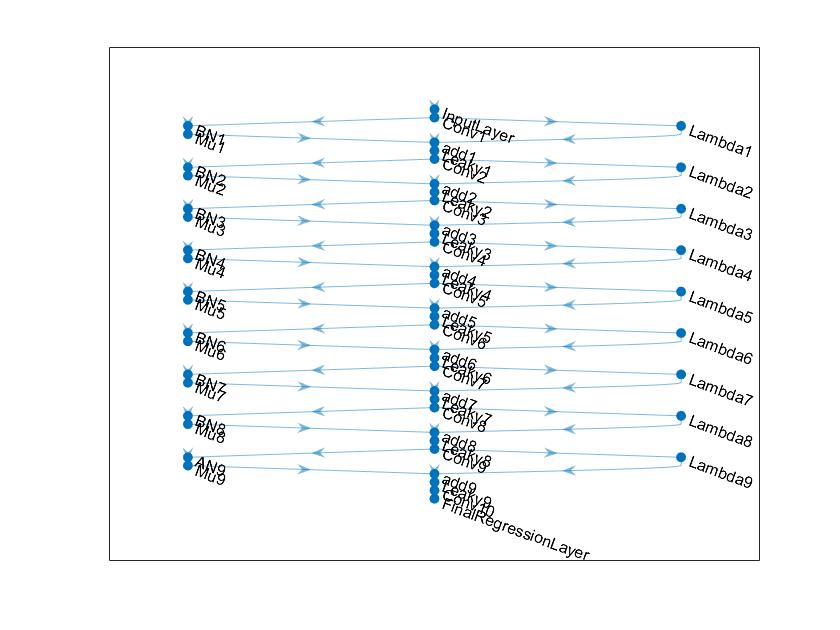

networkDepth = 10;
numberOfFilters = 32;
firstLayer = imageInputLayer([patch_size_x patch_size_y 3],'Name','InputLayer','Normalization','none');


Wgts = zeros(3,3,3,numberOfFilters); 
for ii = 1:3
    % Denne kan lekes med (senere). Bygget for RGB-bilder.
    Wgts(2,2,ii,ii) = 1;
end
convolutionLayer = convolution2dLayer(3,numberOfFilters,'Padding',1, ...
    'Weights',Wgts,'Name','Conv1');


batchNorm = batchNormalizationLayer('Name','BN1');
adaptiveMu = adaptiveNormalizationMu(numberOfFilters,'Mu1');
addLayer = additionLayer(2,'Name','add1');
leakyrelLayer = leakyReluLayer(0.2,'Name','Leaky1');


middleLayers = [convolutionLayer batchNorm adaptiveMu addLayer leakyrelLayer];

Wgts = zeros(3,3,numberOfFilters,numberOfFilters);
for ii = 1:numberOfFilters
    Wgts(2,2,ii,ii) = 1;
end
    
for layerNumber = 2:networkDepth-2
    dilationFactor = 2^(layerNumber-1);
    padding = dilationFactor;
    conv2dLayer = convolution2dLayer(3,numberOfFilters, ...
        'Padding',padding,'DilationFactor',dilationFactor, ...
        'Weights',Wgts,'Name',['Conv' num2str(layerNumber)]);
    batchNorm = batchNormalizationLayer('Name',['BN' num2str(layerNumber)]);
    adaptiveMu = adaptiveNormalizationMu(numberOfFilters,['Mu' num2str(layerNumber)]);
    addLayer = additionLayer(2,'Name',['add' num2str(layerNumber)]);
    leakyrelLayer = leakyReluLayer(0.2, 'Name', ['Leaky' num2str(layerNumber)]);
    middleLayers = [middleLayers conv2dLayer batchNorm adaptiveMu addLayer leakyrelLayer];    
end


conv2dLayer = convolution2dLayer(3,numberOfFilters, ...
    'Padding',1,'Weights',Wgts,'Name','Conv9');

batchNorm = batchNormalizationLayer('Name','AN9');
adaptiveMu = adaptiveNormalizationMu(numberOfFilters,'Mu9');
addLayer = additionLayer(2,'Name','add9');
leakyrelLayer = leakyReluLayer(0.2,'Name','Leaky9');
middleLayers = [middleLayers conv2dLayer batchNorm adaptiveMu addLayer leakyrelLayer];


Wgts = sqrt(2/(9*numberOfFilters))*randn(1,1,numberOfFilters,3);
conv2dLayer = convolution2dLayer(1,3,'NumChannels',numberOfFilters, ...
    'Weights',Wgts,'Name','Conv10');


finalLayers = [conv2dLayer 
    regressionLayer('Name','FinalRegressionLayer')
];


layers = [firstLayer middleLayers finalLayers'];
lgraph = layerGraph(layers);


skipConv1 = adaptiveNormalizationLambda(numberOfFilters,'Lambda1');
skipConv2 = adaptiveNormalizationLambda(numberOfFilters,'Lambda2');
skipConv3 = adaptiveNormalizationLambda(numberOfFilters,'Lambda3');
skipConv4 = adaptiveNormalizationLambda(numberOfFilters,'Lambda4');
skipConv5 = adaptiveNormalizationLambda(numberOfFilters,'Lambda5');
skipConv6 = adaptiveNormalizationLambda(numberOfFilters,'Lambda6');
skipConv7 = adaptiveNormalizationLambda(numberOfFilters,'Lambda7');
skipConv8 = adaptiveNormalizationLambda(numberOfFilters,'Lambda8');
skipConv9 = adaptiveNormalizationLambda(numberOfFilters,'Lambda9');

lgraph = addLayers(lgraph,skipConv1);
lgraph = connectLayers(lgraph,'Conv1','Lambda1');
lgraph = connectLayers(lgraph,'Lambda1','add1/in2');

lgraph = addLayers(lgraph,skipConv2);
lgraph = connectLayers(lgraph,'Conv2','Lambda2');
lgraph = connectLayers(lgraph,'Lambda2','add2/in2');

lgraph = addLayers(lgraph,skipConv3);
lgraph = connectLayers(lgraph,'Conv3','Lambda3');
lgraph = connectLayers(lgraph,'Lambda3','add3/in2');

lgraph = addLayers(lgraph,skipConv4);
lgraph = connectLayers(lgraph,'Conv4','Lambda4');
lgraph = connectLayers(lgraph,'Lambda4','add4/in2');

lgraph = addLayers(lgraph,skipConv5);
lgraph = connectLayers(lgraph,'Conv5','Lambda5');
lgraph = connectLayers(lgraph,'Lambda5','add5/in2');

lgraph = addLayers(lgraph,skipConv6);
lgraph = connectLayers(lgraph,'Conv6','Lambda6');
lgraph = connectLayers(lgraph,'Lambda6','add6/in2');

lgraph = addLayers(lgraph,skipConv7);
lgraph = connectLayers(lgraph,'Conv7','Lambda7');
lgraph = connectLayers(lgraph,'Lambda7','add7/in2');

lgraph = addLayers(lgraph,skipConv8);
lgraph = connectLayers(lgraph,'Conv8','Lambda8');
lgraph = connectLayers(lgraph,'Lambda8','add8/in2');

lgraph = addLayers(lgraph,skipConv9);
lgraph = connectLayers(lgraph,'Conv9','Lambda9');
lgraph = connectLayers(lgraph,'Lambda9','add9/in2');


plot(lgraph)

## Specify Training Options

maxEpochs = 100;
initLearningRate = 0.01; % Lek!
miniBatchSize = 1; % Iterasjoner = len(bilder) / miniBatchSize

options = trainingOptions('adam', ...
    'InitialLearnRate',initLearningRate, ...
    'MaxEpochs',maxEpochs, ...
    'MiniBatchSize',miniBatchSize, ...
    'Plots','training-progress', ...
    'Verbose',true);

## Train the Network

doTraining = true;
if doTraining
    modelDateTime = datestr(now,'dd-mmm-yyyy-HH-MM-SS');
    net = trainNetwork(dsTrain,lgraph,options);
    save(['models/trainedOperatorLearning-' modelDateTime '-Epoch-' num2str(maxEpochs) '.mat'],'net');
else
    load('models/trainedOperatorLearning-Epoch-181.mat');
end

Training on single GPU.


|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|


|       1 |           1 |       00:00:04 |      7344.80 |      2.7e+07 |          0.0100 |


|       1 |          50 |       00:00:11 |       811.41 |     329196.4 |          0.0100 |


|       1 |         100 |       00:00:18 |      7388.42 |      2.7e+07 |          0.0100 |


|       1 |         150 |       00:00:25 |      7743.84 |      3.0e+07 |          0.0100 |


|       1 |         200 |       00:00:32 |      4081.40 |      8.3e+06 |          0.0100 |


|       1 |         250 |       00:00:39 |      3688.47 |      6.8e+06 |          0.0100 |


|       1 |         300 |       00:00:47 |      4024.00 |      8.1e+06 |          0.0100 |


|       1 |         350 |       00:00:54 |      5689.43 |      1.6e+07 |          0.0100 |


|       1 |         400 |       00:01:01 |      8231.38 |      3.4e+07 |          0.0100 |


|       1 |         450 |       00:01:09 |      5412.13 |      1.5e+07 |          0.0100 |


|       1 |         500 |       00:01:17 |      5630.06 |      1.6e+07 |          0.0100 |


|       1 |         550 |       00:01:24 |      4515.40 |      1.0e+07 |          0.0100 |


|       1 |         600 |       00:01:32 |      6359.57 |      2.0e+07 |          0.0100 |


|       1 |         650 |       00:01:39 |      6033.69 |      1.8e+07 |          0.0100 |


|       1 |         700 |       00:01:46 |      7555.12 |      2.9e+07 |          0.0100 |


|       1 |         750 |       00:01:54 |      5076.55 |      1.3e+07 |          0.0100 |


|       1 |         800 |       00:02:01 |      4073.42 |      8.3e+06 |          0.0100 |


|       1 |         850 |       00:02:08 |      3973.41 |      7.9e+06 |          0.0100 |


|       1 |         900 |       00:02:15 |       824.58 |     339963.9 |          0.0100 |


|       1 |         950 |       00:02:21 |      5827.36 |      1.7e+07 |          0.0100 |


|       1 |        1000 |       00:02:29 |      2756.11 |      3.8e+06 |          0.0100 |


|       2 |        1050 |       00:02:36 |      6852.71 |      2.3e+07 |          0.0100 |


|       2 |        1100 |       00:02:44 |      7613.56 |      2.9e+07 |          0.0100 |


|       2 |        1150 |       00:02:51 |      1978.14 |      2.0e+06 |          0.0100 |


|       2 |        1200 |       00:02:58 |      3547.57 |      6.3e+06 |          0.0100 |


|       2 |        1250 |       00:03:05 |      3007.45 |      4.5e+06 |          0.0100 |


|       2 |        1300 |       00:03:12 |      4313.71 |      9.3e+06 |          0.0100 |


|       2 |        1350 |       00:03:19 |      5770.54 |      1.7e+07 |          0.0100 |


|       2 |        1400 |       00:03:26 |      2817.35 |      4.0e+06 |          0.0100 |


|       2 |        1450 |       00:03:33 |      6839.28 |      2.3e+07 |          0.0100 |


|       2 |        1500 |       00:03:40 |      5197.40 |      1.4e+07 |          0.0100 |


|       2 |        1550 |       00:03:48 |      5441.84 |      1.5e+07 |          0.0100 |


|       2 |        1600 |       00:03:55 |      3491.41 |      6.1e+06 |          0.0100 |


|       2 |        1650 |       00:04:01 |      6354.81 |      2.0e+07 |          0.0100 |


|       2 |        1700 |       00:04:08 |      2826.19 |      4.0e+06 |          0.0100 |


|       2 |        1750 |       00:04:15 |      5773.44 |      1.7e+07 |          0.0100 |


|       2 |        1800 |       00:04:21 |      3688.04 |      6.8e+06 |          0.0100 |


|       2 |        1850 |       00:04:27 |      6728.31 |      2.3e+07 |          0.0100 |


|       2 |        1900 |       00:04:33 |      5961.37 |      1.8e+07 |          0.0100 |


|       2 |        1950 |       00:04:39 |      6847.27 |      2.3e+07 |          0.0100 |


|       2 |        2000 |       00:04:45 |      5588.81 |      1.6e+07 |          0.0100 |


|       3 |        2050 |       00:04:51 |      5830.02 |      1.7e+07 |          0.0100 |


|       3 |        2100 |       00:04:57 |      3164.42 |      5.0e+06 |          0.0100 |


|       3 |        2150 |       00:05:04 |      3742.17 |      7.0e+06 |          0.0100 |


|       3 |        2200 |       00:05:13 |      4502.00 |      1.0e+07 |          0.0100 |


|       3 |        2250 |       00:05:19 |      3613.33 |      6.5e+06 |          0.0100 |


|       3 |        2300 |       00:05:25 |      4589.81 |      1.1e+07 |          0.0100 |


|       3 |        2350 |       00:05:31 |      3670.86 |      6.7e+06 |          0.0100 |


|       3 |        2400 |       00:05:37 |      6333.61 |      2.0e+07 |          0.0100 |


|       3 |        2450 |       00:05:43 |      3127.38 |      4.9e+06 |          0.0100 |


|       3 |        2500 |       00:05:49 |      6058.16 |      1.8e+07 |          0.0100 |


|       3 |        2550 |       00:05:55 |      6817.23 |      2.3e+07 |          0.0100 |


|       3 |        2600 |       00:06:01 |      5051.46 |      1.3e+07 |          0.0100 |


|       3 |        2650 |       00:06:07 |      2705.08 |      3.7e+06 |          0.0100 |


|       3 |        2700 |       00:06:13 |      6454.88 |      2.1e+07 |          0.0100 |


|       3 |        2750 |       00:06:19 |      3955.01 |      7.8e+06 |          0.0100 |


|       3 |        2800 |       00:06:25 |      6271.07 |      2.0e+07 |          0.0100 |


|       3 |        2850 |       00:06:31 |      5801.66 |      1.7e+07 |          0.0100 |


|       3 |        2900 |       00:06:37 |      4264.17 |      9.1e+06 |          0.0100 |


|       3 |        2950 |       00:06:43 |      3225.97 |      5.2e+06 |          0.0100 |


|       3 |        3000 |       00:06:49 |      3660.62 |      6.7e+06 |          0.0100 |


|       4 |        3050 |       00:06:55 |      3118.19 |      4.9e+06 |          0.0100 |


|       4 |        3100 |       00:07:01 |      6173.10 |      1.9e+07 |          0.0100 |


|       4 |        3150 |       00:07:07 |      4327.60 |      9.4e+06 |          0.0100 |


|       4 |        3200 |       00:07:13 |      3925.24 |      7.7e+06 |          0.0100 |


|       4 |        3250 |       00:07:20 |      3282.23 |      5.4e+06 |          0.0100 |


|       4 |        3300 |       00:07:26 |      5822.90 |      1.7e+07 |          0.0100 |


|       4 |        3350 |       00:07:32 |      3084.83 |      4.8e+06 |          0.0100 |


|       4 |        3400 |       00:07:38 |      3209.28 |      5.1e+06 |          0.0100 |


|       4 |        3450 |       00:07:44 |      3744.90 |      7.0e+06 |          0.0100 |


|       4 |        3500 |       00:07:51 |      6239.73 |      1.9e+07 |          0.0100 |


|       4 |        3550 |       00:07:57 |      6702.06 |      2.2e+07 |          0.0100 |


|       4 |        3600 |       00:08:04 |      3725.82 |      6.9e+06 |          0.0100 |


|       4 |        3650 |       00:08:10 |      6367.02 |      2.0e+07 |          0.0100 |


|       4 |        3700 |       00:08:17 |      3729.87 |      7.0e+06 |          0.0100 |


|       4 |        3750 |       00:08:23 |      5939.97 |      1.8e+07 |          0.0100 |


|       4 |        3800 |       00:08:29 |      6338.41 |      2.0e+07 |          0.0100 |


|       4 |        3850 |       00:08:36 |      6509.42 |      2.1e+07 |          0.0100 |


|       4 |        3900 |       00:08:42 |      3421.48 |      5.9e+06 |          0.0100 |


|       4 |        3950 |       00:08:49 |      3623.88 |      6.6e+06 |          0.0100 |


|       4 |        4000 |       00:08:55 |      3707.09 |      6.9e+06 |          0.0100 |


|       5 |        4050 |       00:09:02 |      6082.55 |      1.8e+07 |          0.0100 |


|       5 |        4100 |       00:09:09 |      6029.21 |      1.8e+07 |          0.0100 |


|       5 |        4150 |       00:09:15 |      3819.56 |      7.3e+06 |          0.0100 |


|       5 |        4200 |       00:09:21 |      3227.75 |      5.2e+06 |          0.0100 |


|       5 |        4250 |       00:09:28 |      3016.52 |      4.5e+06 |          0.0100 |


|       5 |        4300 |       00:09:34 |      5825.22 |      1.7e+07 |          0.0100 |


|       5 |        4350 |       00:09:41 |      5092.90 |      1.3e+07 |          0.0100 |


|       5 |        4400 |       00:09:47 |      4080.27 |      8.3e+06 |          0.0100 |


|       5 |        4450 |       00:09:54 |      6222.57 |      1.9e+07 |          0.0100 |


|       5 |        4500 |       00:10:01 |      5806.18 |      1.7e+07 |          0.0100 |


|       5 |        4550 |       00:10:08 |      4636.05 |      1.1e+07 |          0.0100 |


|       5 |        4600 |       00:10:14 |      3898.87 |      7.6e+06 |          0.0100 |


|       5 |        4650 |       00:10:21 |      3748.18 |      7.0e+06 |          0.0100 |


|       5 |        4700 |       00:10:27 |      3915.87 |      7.7e+06 |          0.0100 |


|       5 |        4750 |       00:10:35 |      6250.34 |      2.0e+07 |          0.0100 |


|       5 |        4800 |       00:10:42 |      5808.61 |      1.7e+07 |          0.0100 |


|       5 |        4850 |       00:10:49 |      4728.65 |      1.1e+07 |          0.0100 |


|       5 |        4900 |       00:10:56 |      3382.30 |      5.7e+06 |          0.0100 |


|       5 |        4950 |       00:11:04 |      5262.92 |      1.4e+07 |          0.0100 |


|       5 |        5000 |       00:11:13 |      6044.27 |      1.8e+07 |          0.0100 |


|       6 |        5050 |       00:11:21 |      3689.57 |      6.8e+06 |          0.0100 |


|       6 |        5100 |       00:11:29 |      3046.83 |      4.6e+06 |          0.0100 |


|       6 |        5150 |       00:11:37 |      5869.15 |      1.7e+07 |          0.0100 |


|       6 |        5200 |       00:11:46 |      6003.25 |      1.8e+07 |          0.0100 |


|       6 |        5250 |       00:11:53 |      5321.01 |      1.4e+07 |          0.0100 |


|       6 |        5300 |       00:12:04 |      5312.46 |      1.4e+07 |          0.0100 |


|       6 |        5350 |       00:12:10 |      3519.21 |      6.2e+06 |          0.0100 |


|       6 |        5400 |       00:12:18 |      3676.81 |      6.8e+06 |          0.0100 |


|       6 |        5450 |       00:12:25 |      3771.61 |      7.1e+06 |          0.0100 |


|       6 |        5500 |       00:12:34 |      5976.68 |      1.8e+07 |          0.0100 |


|       6 |        5550 |       00:12:41 |      6100.12 |      1.9e+07 |          0.0100 |


|       6 |        5600 |       00:12:49 |      3884.42 |      7.5e+06 |          0.0100 |


|       6 |        5650 |       00:12:58 |      3020.33 |      4.6e+06 |          0.0100 |


|       6 |        5700 |       00:13:06 |      6123.19 |      1.9e+07 |          0.0100 |


|       6 |        5750 |       00:13:14 |      4435.45 |      9.8e+06 |          0.0100 |


|       6 |        5800 |       00:13:23 |      5987.97 |      1.8e+07 |          0.0100 |


|       6 |        5850 |       00:13:31 |      5339.71 |      1.4e+07 |          0.0100 |


|       6 |        5900 |       00:13:39 |      6834.05 |      2.3e+07 |          0.0100 |


|       6 |        5950 |       00:13:46 |      5586.41 |      1.6e+07 |          0.0100 |


|       6 |        6000 |       00:13:54 |      5565.27 |      1.5e+07 |          0.0100 |


|       7 |        6050 |       00:14:02 |      3138.44 |      4.9e+06 |          0.0100 |


|       7 |        6100 |       00:14:11 |      5187.82 |      1.3e+07 |          0.0100 |


|       7 |        6150 |       00:14:19 |      3043.81 |      4.6e+06 |          0.0100 |


|       7 |        6200 |       00:14:27 |      3823.25 |      7.3e+06 |          0.0100 |


|       7 |        6250 |       00:14:34 |      6532.40 |      2.1e+07 |          0.0100 |


|       7 |        6300 |       00:14:41 |      6173.69 |      1.9e+07 |          0.0100 |


|       7 |        6350 |       00:14:48 |      4263.78 |      9.1e+06 |          0.0100 |


|       7 |        6400 |       00:14:55 |      4327.33 |      9.4e+06 |          0.0100 |


|       7 |        6450 |       00:15:02 |      6205.75 |      1.9e+07 |          0.0100 |


|       7 |        6500 |       00:15:08 |      4119.92 |      8.5e+06 |          0.0100 |


|       7 |        6550 |       00:15:17 |      3967.20 |      7.9e+06 |          0.0100 |


|       7 |        6600 |       00:15:25 |      4012.30 |      8.0e+06 |          0.0100 |


|       7 |        6650 |       00:15:33 |      4748.16 |      1.1e+07 |          0.0100 |


|       7 |        6700 |       00:15:41 |      3745.26 |      7.0e+06 |          0.0100 |


|       7 |        6750 |       00:15:49 |      4508.00 |      1.0e+07 |          0.0100 |


|       7 |        6800 |       00:15:57 |      5956.97 |      1.8e+07 |          0.0100 |


|       7 |        6850 |       00:16:05 |      6038.99 |      1.8e+07 |          0.0100 |


|       7 |        6900 |       00:16:13 |      5485.44 |      1.5e+07 |          0.0100 |


|       7 |        6950 |       00:16:20 |      5948.29 |      1.8e+07 |          0.0100 |


|       7 |        7000 |       00:16:27 |      3598.52 |      6.5e+06 |          0.0100 |


|       8 |        7050 |       00:16:34 |      3639.55 |      6.6e+06 |          0.0100 |


|       8 |        7100 |       00:16:40 |      4967.09 |      1.2e+07 |          0.0100 |


|       8 |        7150 |       00:16:47 |      3595.44 |      6.5e+06 |          0.0100 |


|       8 |        7200 |       00:16:54 |      5333.84 |      1.4e+07 |          0.0100 |


|       8 |        7250 |       00:17:01 |      3647.82 |      6.7e+06 |          0.0100 |


|       8 |        7300 |       00:17:08 |      4667.37 |      1.1e+07 |          0.0100 |


|       8 |        7350 |       00:17:14 |      3225.94 |      5.2e+06 |          0.0100 |


|       8 |        7400 |       00:17:22 |      3237.09 |      5.2e+06 |          0.0100 |


|       8 |        7450 |       00:17:29 |      5829.50 |      1.7e+07 |          0.0100 |


|       8 |        7500 |       00:17:35 |      3752.23 |      7.0e+06 |          0.0100 |


|       8 |        7550 |       00:17:42 |      6442.19 |      2.1e+07 |          0.0100 |


|       8 |        7600 |       00:17:49 |      6384.48 |      2.0e+07 |          0.0100 |


|       8 |        7650 |       00:17:56 |      3511.43 |      6.2e+06 |          0.0100 |


|       8 |        7700 |       00:18:03 |      2573.64 |      3.3e+06 |          0.0100 |


|       8 |        7750 |       00:18:10 |      5730.79 |      1.6e+07 |          0.0100 |


|       8 |        7800 |       00:18:17 |      6541.16 |      2.1e+07 |          0.0100 |


|       8 |        7850 |       00:18:24 |      3791.45 |      7.2e+06 |          0.0100 |


|       8 |        7900 |       00:18:31 |      3534.67 |      6.2e+06 |          0.0100 |


|       8 |        7950 |       00:18:39 |      5835.86 |      1.7e+07 |          0.0100 |


|       8 |        8000 |       00:18:46 |      6135.52 |      1.9e+07 |          0.0100 |


|       9 |        8050 |       00:18:53 |      5326.19 |      1.4e+07 |          0.0100 |


|       9 |        8100 |       00:19:00 |      3081.60 |      4.7e+06 |          0.0100 |


|       9 |        8150 |       00:19:07 |      3836.66 |      7.4e+06 |          0.0100 |


|       9 |        8200 |       00:19:14 |      5316.45 |      1.4e+07 |          0.0100 |


|       9 |        8250 |       00:19:20 |      3583.52 |      6.4e+06 |          0.0100 |


|       9 |        8300 |       00:19:27 |      4057.05 |      8.2e+06 |          0.0100 |


|       9 |        8350 |       00:19:34 |      3584.29 |      6.4e+06 |          0.0100 |


|       9 |        8400 |       00:19:42 |      3404.40 |      5.8e+06 |          0.0100 |


|       9 |        8450 |       00:19:51 |      3118.95 |      4.9e+06 |          0.0100 |


|       9 |        8500 |       00:20:02 |      6029.72 |      1.8e+07 |          0.0100 |


|       9 |        8550 |       00:20:10 |      4327.12 |      9.4e+06 |          0.0100 |


|       9 |        8600 |       00:20:18 |      3919.72 |      7.7e+06 |          0.0100 |


|       9 |        8650 |       00:20:26 |      3482.84 |      6.1e+06 |          0.0100 |


|       9 |        8700 |       00:20:34 |      5628.27 |      1.6e+07 |          0.0100 |


|       9 |        8750 |       00:20:42 |      3036.50 |      4.6e+06 |          0.0100 |


|       9 |        8800 |       00:20:49 |      6680.90 |      2.2e+07 |          0.0100 |


|       9 |        8850 |       00:20:58 |      7026.70 |      2.5e+07 |          0.0100 |


|       9 |        8900 |       00:21:06 |      4456.11 |      9.9e+06 |          0.0100 |


|       9 |        8950 |       00:21:13 |      5746.00 |      1.7e+07 |          0.0100 |


|       9 |        9000 |       00:21:19 |      3798.14 |      7.2e+06 |          0.0100 |


|      10 |        9050 |       00:21:27 |      5378.64 |      1.4e+07 |          0.0100 |


|      10 |        9100 |       00:21:34 |      5553.92 |      1.5e+07 |          0.0100 |


|      10 |        9150 |       00:21:42 |      5087.21 |      1.3e+07 |          0.0100 |


|      10 |        9200 |       00:21:49 |      5655.30 |      1.6e+07 |          0.0100 |


|      10 |        9250 |       00:21:56 |      6183.20 |      1.9e+07 |          0.0100 |


|      10 |        9300 |       00:22:04 |      3799.03 |      7.2e+06 |          0.0100 |


|      10 |        9350 |       00:22:12 |      5226.82 |      1.4e+07 |          0.0100 |


|      10 |        9400 |       00:22:19 |      3351.42 |      5.6e+06 |          0.0100 |


|      10 |        9450 |       00:22:26 |      3824.58 |      7.3e+06 |          0.0100 |


|      10 |        9500 |       00:22:33 |      3561.26 |      6.3e+06 |          0.0100 |


|      10 |        9550 |       00:22:40 |      3599.50 |      6.5e+06 |          0.0100 |


|      10 |        9600 |       00:22:47 |      6371.91 |      2.0e+07 |          0.0100 |


|      10 |        9650 |       00:22:54 |      2993.43 |      4.5e+06 |          0.0100 |


|      10 |        9700 |       00:23:01 |      5729.38 |      1.6e+07 |          0.0100 |


|      10 |        9750 |       00:23:07 |      6062.50 |      1.8e+07 |          0.0100 |


|      10 |        9800 |       00:23:14 |      6342.35 |      2.0e+07 |          0.0100 |


|      10 |        9850 |       00:23:21 |      5561.84 |      1.5e+07 |          0.0100 |


|      10 |        9900 |       00:23:28 |      5782.04 |      1.7e+07 |          0.0100 |


|      10 |        9950 |       00:23:34 |      3602.22 |      6.5e+06 |          0.0100 |


|      10 |       10000 |       00:23:41 |      5450.61 |      1.5e+07 |          0.0100 |


|      11 |       10050 |       00:23:48 |      5613.21 |      1.6e+07 |          0.0100 |


|      11 |       10100 |       00:23:54 |      3591.05 |      6.4e+06 |          0.0100 |


|      11 |       10150 |       00:24:01 |      3693.37 |      6.8e+06 |          0.0100 |


|      11 |       10200 |       00:24:07 |      4594.28 |      1.1e+07 |          0.0100 |


|      11 |       10250 |       00:24:14 |      5291.91 |      1.4e+07 |          0.0100 |


|      11 |       10300 |       00:24:21 |      3713.73 |      6.9e+06 |          0.0100 |


|      11 |       10350 |       00:24:27 |      5641.80 |      1.6e+07 |          0.0100 |


|      11 |       10400 |       00:24:34 |      3642.59 |      6.6e+06 |          0.0100 |


|      11 |       10450 |       00:24:40 |      3865.64 |      7.5e+06 |          0.0100 |


|      11 |       10500 |       00:24:47 |      3975.18 |      7.9e+06 |          0.0100 |


|      11 |       10550 |       00:24:53 |      2851.24 |      4.1e+06 |          0.0100 |


|      11 |       10600 |       00:25:00 |      3678.09 |      6.8e+06 |          0.0100 |


|      11 |       10650 |       00:25:07 |      6056.86 |      1.8e+07 |          0.0100 |


|      11 |       10700 |       00:25:13 |      4880.80 |      1.2e+07 |          0.0100 |


|      11 |       10750 |       00:25:20 |      3517.51 |      6.2e+06 |          0.0100 |


|      11 |       10800 |       00:25:26 |      6409.48 |      2.1e+07 |          0.0100 |


|      11 |       10850 |       00:25:32 |      5935.25 |      1.8e+07 |          0.0100 |


|      11 |       10900 |       00:25:39 |      3509.83 |      6.2e+06 |          0.0100 |


|      11 |       10950 |       00:25:45 |      2921.73 |      4.3e+06 |          0.0100 |


|      11 |       11000 |       00:25:52 |      6101.90 |      1.9e+07 |          0.0100 |


|      12 |       11050 |       00:25:58 |      5522.78 |      1.5e+07 |          0.0100 |


|      12 |       11100 |       00:26:05 |      5481.36 |      1.5e+07 |          0.0100 |


|      12 |       11150 |       00:26:11 |      3867.37 |      7.5e+06 |          0.0100 |


|      12 |       11200 |       00:26:18 |      5789.11 |      1.7e+07 |          0.0100 |


|      12 |       11250 |       00:26:24 |      5056.56 |      1.3e+07 |          0.0100 |


|      12 |       11300 |       00:26:31 |      3356.57 |      5.6e+06 |          0.0100 |


|      12 |       11350 |       00:26:38 |      4262.15 |      9.1e+06 |          0.0100 |


|      12 |       11400 |       00:26:44 |      5664.91 |      1.6e+07 |          0.0100 |


|      12 |       11450 |       00:26:51 |      6078.24 |      1.8e+07 |          0.0100 |


|      12 |       11500 |       00:26:57 |      5297.05 |      1.4e+07 |          0.0100 |


|      12 |       11550 |       00:27:04 |      6302.69 |      2.0e+07 |          0.0100 |


|      12 |       11600 |       00:27:11 |      2947.89 |      4.3e+06 |          0.0100 |


|      12 |       11650 |       00:27:17 |      3532.91 |      6.2e+06 |          0.0100 |


|      12 |       11700 |       00:27:24 |      5052.49 |      1.3e+07 |          0.0100 |


|      12 |       11750 |       00:27:30 |      6090.41 |      1.9e+07 |          0.0100 |


|      12 |       11800 |       00:27:37 |      5802.98 |      1.7e+07 |          0.0100 |


|      12 |       11850 |       00:27:44 |      3172.84 |      5.0e+06 |          0.0100 |


|      12 |       11900 |       00:27:50 |      3367.81 |      5.7e+06 |          0.0100 |


|      12 |       11950 |       00:27:57 |      3132.44 |      4.9e+06 |          0.0100 |


|      12 |       12000 |       00:28:03 |      3567.82 |      6.4e+06 |          0.0100 |


|      13 |       12050 |       00:28:10 |      4341.82 |      9.4e+06 |          0.0100 |


|      13 |       12100 |       00:28:17 |      3980.89 |      7.9e+06 |          0.0100 |


|      13 |       12150 |       00:28:24 |      3580.67 |      6.4e+06 |          0.0100 |


|      13 |       12200 |       00:28:31 |      5568.30 |      1.6e+07 |          0.0100 |


|      13 |       12250 |       00:28:39 |      3204.99 |      5.1e+06 |          0.0100 |


|      13 |       12300 |       00:28:47 |      6416.47 |      2.1e+07 |          0.0100 |


|      13 |       12350 |       00:28:54 |      3098.50 |      4.8e+06 |          0.0100 |


|      13 |       12400 |       00:29:02 |      3731.02 |      7.0e+06 |          0.0100 |


|      13 |       12450 |       00:29:09 |      4723.39 |      1.1e+07 |          0.0100 |


|      13 |       12500 |       00:29:17 |      3141.55 |      4.9e+06 |          0.0100 |


|      13 |       12550 |       00:29:24 |      5778.79 |      1.7e+07 |          0.0100 |


|      13 |       12600 |       00:29:31 |      3493.89 |      6.1e+06 |          0.0100 |


|      13 |       12650 |       00:29:38 |      3988.17 |      8.0e+06 |          0.0100 |


|      13 |       12700 |       00:29:44 |      3798.41 |      7.2e+06 |          0.0100 |


|      13 |       12750 |       00:29:51 |      5819.56 |      1.7e+07 |          0.0100 |


|      13 |       12800 |       00:29:58 |      3941.66 |      7.8e+06 |          0.0100 |


|      13 |       12850 |       00:30:06 |      3841.73 |      7.4e+06 |          0.0100 |


|      13 |       12900 |       00:30:12 |      5372.86 |      1.4e+07 |          0.0100 |


|      13 |       12950 |       00:30:19 |      5282.10 |      1.4e+07 |          0.0100 |


|      13 |       13000 |       00:30:26 |      5748.80 |      1.7e+07 |          0.0100 |


|      14 |       13050 |       00:30:34 |      5845.98 |      1.7e+07 |          0.0100 |


|      14 |       13100 |       00:30:41 |      3665.88 |      6.7e+06 |          0.0100 |


|      14 |       13150 |       00:30:48 |      3805.25 |      7.2e+06 |          0.0100 |


|      14 |       13200 |       00:30:55 |      3975.71 |      7.9e+06 |          0.0100 |


|      14 |       13250 |       00:31:02 |      4633.60 |      1.1e+07 |          0.0100 |


|      14 |       13300 |       00:31:09 |      5854.01 |      1.7e+07 |          0.0100 |


|      14 |       13350 |       00:31:16 |      5112.60 |      1.3e+07 |          0.0100 |


|      14 |       13400 |       00:31:23 |      6023.54 |      1.8e+07 |          0.0100 |


|      14 |       13450 |       00:31:30 |      3878.36 |      7.5e+06 |          0.0100 |


|      14 |       13500 |       00:31:37 |      4089.23 |      8.4e+06 |          0.0100 |


|      14 |       13550 |       00:31:44 |      3878.43 |      7.5e+06 |          0.0100 |


|      14 |       13600 |       00:31:51 |      3719.62 |      6.9e+06 |          0.0100 |


|      14 |       13650 |       00:31:58 |      3184.73 |      5.1e+06 |          0.0100 |


|      14 |       13700 |       00:32:05 |      5403.04 |      1.5e+07 |          0.0100 |


|      14 |       13750 |       00:32:12 |      3325.37 |      5.5e+06 |          0.0100 |


|      14 |       13800 |       00:32:20 |      6044.68 |      1.8e+07 |          0.0100 |


|      14 |       13850 |       00:32:26 |      3098.49 |      4.8e+06 |          0.0100 |


|      14 |       13900 |       00:32:34 |      6040.49 |      1.8e+07 |          0.0100 |


|      14 |       13950 |       00:32:41 |      4172.97 |      8.7e+06 |          0.0100 |


|      14 |       14000 |       00:32:48 |      5565.58 |      1.5e+07 |          0.0100 |


|      15 |       14050 |       00:32:55 |      3324.91 |      5.5e+06 |          0.0100 |


|      15 |       14100 |       00:33:02 |      3429.93 |      5.9e+06 |          0.0100 |


|      15 |       14150 |       00:33:08 |      5561.59 |      1.5e+07 |          0.0100 |


|      15 |       14200 |       00:33:15 |      5400.41 |      1.5e+07 |          0.0100 |


|      15 |       14250 |       00:33:21 |      3555.63 |      6.3e+06 |          0.0100 |


|      15 |       14300 |       00:33:28 |      4113.54 |      8.5e+06 |          0.0100 |


|      15 |       14350 |       00:33:34 |      5974.75 |      1.8e+07 |          0.0100 |


|      15 |       14400 |       00:33:41 |      5148.39 |      1.3e+07 |          0.0100 |


|      15 |       14450 |       00:33:48 |      5549.20 |      1.5e+07 |          0.0100 |


|      15 |       14500 |       00:33:54 |      4115.85 |      8.5e+06 |          0.0100 |


|      15 |       14550 |       00:34:01 |      4104.87 |      8.4e+06 |          0.0100 |


|      15 |       14600 |       00:34:07 |      5335.31 |      1.4e+07 |          0.0100 |


|      15 |       14650 |       00:34:14 |      3849.91 |      7.4e+06 |          0.0100 |


|      15 |       14700 |       00:34:20 |      3285.95 |      5.4e+06 |          0.0100 |


|      15 |       14750 |       00:34:27 |      6180.84 |      1.9e+07 |          0.0100 |


|      15 |       14800 |       00:34:33 |      3272.34 |      5.4e+06 |          0.0100 |


|      15 |       14850 |       00:34:40 |      5933.92 |      1.8e+07 |          0.0100 |


|      15 |       14900 |       00:34:46 |      4016.64 |      8.1e+06 |          0.0100 |


|      15 |       14950 |       00:34:53 |      2810.36 |      3.9e+06 |          0.0100 |


|      15 |       15000 |       00:34:59 |      3287.31 |      5.4e+06 |          0.0100 |


|      16 |       15050 |       00:35:05 |      4143.27 |      8.6e+06 |          0.0100 |


|      16 |       15100 |       00:35:12 |      4761.25 |      1.1e+07 |          0.0100 |


|      16 |       15150 |       00:35:18 |      3695.31 |      6.8e+06 |          0.0100 |


|      16 |       15200 |       00:35:25 |      5722.62 |      1.6e+07 |          0.0100 |


|      16 |       15250 |       00:35:31 |      5794.99 |      1.7e+07 |          0.0100 |


|      16 |       15300 |       00:35:37 |      6137.84 |      1.9e+07 |          0.0100 |


|      16 |       15350 |       00:35:44 |      3409.09 |      5.8e+06 |          0.0100 |


|      16 |       15400 |       00:35:50 |      3711.60 |      6.9e+06 |          0.0100 |


|      16 |       15450 |       00:35:57 |      3882.51 |      7.5e+06 |          0.0100 |


|      16 |       15500 |       00:36:03 |      5612.93 |      1.6e+07 |          0.0100 |


|      16 |       15550 |       00:36:10 |      6566.24 |      2.2e+07 |          0.0100 |


|      16 |       15600 |       00:36:16 |      6163.30 |      1.9e+07 |          0.0100 |


|      16 |       15650 |       00:36:22 |      2929.36 |      4.3e+06 |          0.0100 |


|      16 |       15700 |       00:36:29 |      3240.05 |      5.2e+06 |          0.0100 |


|      16 |       15750 |       00:36:35 |      6077.85 |      1.8e+07 |          0.0100 |


|      16 |       15800 |       00:36:41 |      4133.22 |      8.5e+06 |          0.0100 |


|      16 |       15850 |       00:36:48 |      3482.87 |      6.1e+06 |          0.0100 |


|      16 |       15900 |       00:36:54 |      2983.34 |      4.5e+06 |          0.0100 |


|      16 |       15950 |       00:37:01 |      6363.81 |      2.0e+07 |          0.0100 |


|      16 |       16000 |       00:37:07 |      4237.09 |      9.0e+06 |          0.0100 |


|      17 |       16050 |       00:37:14 |      5576.55 |      1.6e+07 |          0.0100 |


|      17 |       16100 |       00:37:20 |      4852.94 |      1.2e+07 |          0.0100 |


|      17 |       16150 |       00:37:27 |      4047.83 |      8.2e+06 |          0.0100 |


|      17 |       16200 |       00:37:33 |      3411.14 |      5.8e+06 |          0.0100 |


|      17 |       16250 |       00:37:40 |      5992.41 |      1.8e+07 |          0.0100 |


|      17 |       16300 |       00:37:46 |      4054.46 |      8.2e+06 |          0.0100 |


|      17 |       16350 |       00:37:53 |      3724.68 |      6.9e+06 |          0.0100 |


|      17 |       16400 |       00:37:59 |      3831.99 |      7.3e+06 |          0.0100 |


|      17 |       16450 |       00:38:06 |      3741.72 |      7.0e+06 |          0.0100 |


|      17 |       16500 |       00:38:12 |      6557.22 |      2.1e+07 |          0.0100 |


|      17 |       16550 |       00:38:18 |      4447.48 |      9.9e+06 |          0.0100 |


|      17 |       16600 |       00:38:25 |      5797.78 |      1.7e+07 |          0.0100 |


|      17 |       16650 |       00:38:32 |      6199.48 |      1.9e+07 |          0.0100 |


|      17 |       16700 |       00:38:38 |      4094.14 |      8.4e+06 |          0.0100 |


|      17 |       16750 |       00:38:45 |      3802.96 |      7.2e+06 |          0.0100 |


|      17 |       16800 |       00:38:51 |      5740.83 |      1.6e+07 |          0.0100 |


|      17 |       16850 |       00:38:58 |      3330.80 |      5.5e+06 |          0.0100 |


|      17 |       16900 |       00:39:04 |      6006.07 |      1.8e+07 |          0.0100 |


|      17 |       16950 |       00:39:11 |      6126.22 |      1.9e+07 |          0.0100 |


|      17 |       17000 |       00:39:18 |      5009.10 |      1.3e+07 |          0.0100 |


|      18 |       17050 |       00:39:24 |      3663.46 |      6.7e+06 |          0.0100 |


|      18 |       17100 |       00:39:31 |      3498.41 |      6.1e+06 |          0.0100 |


|      18 |       17150 |       00:39:38 |      5759.04 |      1.7e+07 |          0.0100 |


|      18 |       17200 |       00:39:44 |      4728.73 |      1.1e+07 |          0.0100 |


|      18 |       17250 |       00:39:51 |      3538.98 |      6.3e+06 |          0.0100 |


|      18 |       17300 |       00:39:58 |      3019.30 |      4.6e+06 |          0.0100 |


|      18 |       17350 |       00:40:04 |      5546.63 |      1.5e+07 |          0.0100 |


|      18 |       17400 |       00:40:11 |      3318.51 |      5.5e+06 |          0.0100 |


|      18 |       17450 |       00:40:18 |      5746.14 |      1.7e+07 |          0.0100 |


|      18 |       17500 |       00:40:24 |      6112.41 |      1.9e+07 |          0.0100 |


|      18 |       17550 |       00:40:31 |      3291.51 |      5.4e+06 |          0.0100 |


|      18 |       17600 |       00:40:37 |      6422.19 |      2.1e+07 |          0.0100 |


|      18 |       17650 |       00:40:44 |      5955.63 |      1.8e+07 |          0.0100 |


|      18 |       17700 |       00:40:51 |      3661.16 |      6.7e+06 |          0.0100 |


|      18 |       17750 |       00:40:57 |      6031.08 |      1.8e+07 |          0.0100 |


|      18 |       17800 |       00:41:04 |      4535.65 |      1.0e+07 |          0.0100 |


|      18 |       17850 |       00:41:11 |      3339.69 |      5.6e+06 |          0.0100 |


|      18 |       17900 |       00:41:17 |      5533.13 |      1.5e+07 |          0.0100 |


|      18 |       17950 |       00:41:24 |      4135.25 |      8.6e+06 |          0.0100 |


|      18 |       18000 |       00:41:31 |      3827.40 |      7.3e+06 |          0.0100 |


|      19 |       18050 |       00:41:38 |      5856.39 |      1.7e+07 |          0.0100 |


|      19 |       18100 |       00:41:44 |      3302.27 |      5.5e+06 |          0.0100 |


|      19 |       18150 |       00:41:51 |      5031.84 |      1.3e+07 |          0.0100 |


|      19 |       18200 |       00:41:58 |      2965.31 |      4.4e+06 |          0.0100 |


|      19 |       18250 |       00:42:04 |      5817.01 |      1.7e+07 |          0.0100 |


|      19 |       18300 |       00:42:11 |      5685.60 |      1.6e+07 |          0.0100 |


|      19 |       18350 |       00:42:18 |      4469.31 |      1.0e+07 |          0.0100 |


|      19 |       18400 |       00:42:24 |      5571.11 |      1.6e+07 |          0.0100 |


|      19 |       18450 |       00:42:31 |      3132.13 |      4.9e+06 |          0.0100 |


|      19 |       18500 |       00:42:38 |      5626.19 |      1.6e+07 |          0.0100 |


|      19 |       18550 |       00:42:44 |      5982.35 |      1.8e+07 |          0.0100 |


|      19 |       18600 |       00:42:51 |      6067.39 |      1.8e+07 |          0.0100 |


|      19 |       18650 |       00:42:58 |      3788.76 |      7.2e+06 |          0.0100 |


|      19 |       18700 |       00:43:04 |      5256.00 |      1.4e+07 |          0.0100 |


|      19 |       18750 |       00:43:11 |      3629.39 |      6.6e+06 |          0.0100 |


|      19 |       18800 |       00:43:18 |      3840.03 |      7.4e+06 |          0.0100 |


|      19 |       18850 |       00:43:24 |      3686.42 |      6.8e+06 |          0.0100 |


|      19 |       18900 |       00:43:31 |      3943.86 |      7.8e+06 |          0.0100 |


|      19 |       18950 |       00:43:38 |      6068.50 |      1.8e+07 |          0.0100 |


|      19 |       19000 |       00:43:45 |      3749.63 |      7.0e+06 |          0.0100 |


|      20 |       19050 |       00:43:51 |      3200.03 |      5.1e+06 |          0.0100 |


|      20 |       19100 |       00:43:58 |      5896.53 |      1.7e+07 |          0.0100 |


|      20 |       19150 |       00:44:05 |      6195.85 |      1.9e+07 |          0.0100 |


|      20 |       19200 |       00:44:12 |      3687.47 |      6.8e+06 |          0.0100 |


|      20 |       19250 |       00:44:18 |      5345.76 |      1.4e+07 |          0.0100 |


|      20 |       19300 |       00:44:25 |      5381.62 |      1.4e+07 |          0.0100 |


|      20 |       19350 |       00:44:32 |      3424.19 |      5.9e+06 |          0.0100 |


|      20 |       19400 |       00:44:38 |      6073.39 |      1.8e+07 |          0.0100 |


|      20 |       19450 |       00:44:45 |      6653.25 |      2.2e+07 |          0.0100 |


|      20 |       19500 |       00:44:52 |      5970.88 |      1.8e+07 |          0.0100 |


|      20 |       19550 |       00:44:59 |      5580.58 |      1.6e+07 |          0.0100 |


|      20 |       19600 |       00:45:05 |      3542.15 |      6.3e+06 |          0.0100 |


|      20 |       19650 |       00:45:12 |      3361.25 |      5.6e+06 |          0.0100 |


|      20 |       19700 |       00:45:19 |      3106.69 |      4.8e+06 |          0.0100 |


|      20 |       19750 |       00:45:25 |      4293.50 |      9.2e+06 |          0.0100 |


|      20 |       19800 |       00:45:32 |      3156.26 |      5.0e+06 |          0.0100 |


|      20 |       19850 |       00:45:39 |      3561.31 |      6.3e+06 |          0.0100 |


|      20 |       19900 |       00:45:46 |      3340.81 |      5.6e+06 |          0.0100 |


|      20 |       19950 |       00:45:53 |      5931.17 |      1.8e+07 |          0.0100 |


|      20 |       20000 |       00:45:59 |      5163.23 |      1.3e+07 |          0.0100 |


|      21 |       20050 |       00:46:06 |      6278.77 |      2.0e+07 |          0.0100 |


|      21 |       20100 |       00:46:13 |      3259.48 |      5.3e+06 |          0.0100 |


|      21 |       20150 |       00:46:20 |      3962.92 |      7.9e+06 |          0.0100 |


|      21 |       20200 |       00:46:27 |      5475.80 |      1.5e+07 |          0.0100 |


|      21 |       20250 |       00:46:34 |      3411.51 |      5.8e+06 |          0.0100 |


|      21 |       20300 |       00:46:41 |      2827.32 |      4.0e+06 |          0.0100 |


|      21 |       20350 |       00:46:48 |      3627.54 |      6.6e+06 |          0.0100 |


|      21 |       20400 |       00:46:55 |      2868.70 |      4.1e+06 |          0.0100 |


|      21 |       20450 |       00:47:01 |      5166.56 |      1.3e+07 |          0.0100 |


|      21 |       20500 |       00:47:08 |      3292.22 |      5.4e+06 |          0.0100 |


|      21 |       20550 |       00:47:15 |      5182.04 |      1.3e+07 |          0.0100 |


|      21 |       20600 |       00:47:22 |      3600.37 |      6.5e+06 |          0.0100 |


|      21 |       20650 |       00:47:29 |      3373.26 |      5.7e+06 |          0.0100 |


|      21 |       20700 |       00:47:37 |      6749.68 |      2.3e+07 |          0.0100 |


|      21 |       20750 |       00:47:45 |      5015.01 |      1.3e+07 |          0.0100 |


|      21 |       20800 |       00:47:52 |      4862.30 |      1.2e+07 |          0.0100 |


|      21 |       20850 |       00:47:59 |      5358.94 |      1.4e+07 |          0.0100 |


|      21 |       20900 |       00:48:06 |      3500.19 |      6.1e+06 |          0.0100 |


|      21 |       20950 |       00:48:13 |      5517.02 |      1.5e+07 |          0.0100 |


|      21 |       21000 |       00:48:20 |      4427.50 |      9.8e+06 |          0.0100 |


|      22 |       21050 |       00:48:27 |      6470.08 |      2.1e+07 |          0.0100 |


|      22 |       21100 |       00:48:34 |      3196.18 |      5.1e+06 |          0.0100 |


|      22 |       21150 |       00:48:42 |      3310.83 |      5.5e+06 |          0.0100 |


|      22 |       21200 |       00:48:48 |      5698.65 |      1.6e+07 |          0.0100 |


|      22 |       21250 |       00:48:55 |      6085.06 |      1.9e+07 |          0.0100 |


|      22 |       21300 |       00:49:02 |      5565.66 |      1.5e+07 |          0.0100 |


|      22 |       21350 |       00:49:09 |      3625.33 |      6.6e+06 |          0.0100 |


|      22 |       21400 |       00:49:16 |      4131.19 |      8.5e+06 |          0.0100 |


|      22 |       21450 |       00:49:23 |      4114.52 |      8.5e+06 |          0.0100 |


|      22 |       21500 |       00:49:30 |      5899.50 |      1.7e+07 |          0.0100 |


|      22 |       21550 |       00:49:37 |      5379.37 |      1.4e+07 |          0.0100 |


|      22 |       21600 |       00:49:44 |      6210.95 |      1.9e+07 |          0.0100 |


|      22 |       21650 |       00:49:50 |      6109.22 |      1.9e+07 |          0.0100 |


|      22 |       21700 |       00:49:57 |      3375.99 |      5.7e+06 |          0.0100 |


|      22 |       21750 |       00:50:05 |      7328.23 |      2.7e+07 |          0.0100 |


|      22 |       21800 |       00:50:12 |      6390.29 |      2.0e+07 |          0.0100 |


|      22 |       21850 |       00:50:19 |      5583.75 |      1.6e+07 |          0.0100 |


|      22 |       21900 |       00:50:26 |      3306.53 |      5.5e+06 |          0.0100 |


|      22 |       21950 |       00:50:33 |      3275.39 |      5.4e+06 |          0.0100 |


|      22 |       22000 |       00:50:40 |      3520.65 |      6.2e+06 |          0.0100 |


|      23 |       22050 |       00:50:46 |      3781.95 |      7.2e+06 |          0.0100 |


|      23 |       22100 |       00:50:54 |      5668.91 |      1.6e+07 |          0.0100 |


|      23 |       22150 |       00:51:01 |      6147.93 |      1.9e+07 |          0.0100 |


|      23 |       22200 |       00:51:08 |      5096.12 |      1.3e+07 |          0.0100 |


|      23 |       22250 |       00:51:16 |      4528.76 |      1.0e+07 |          0.0100 |


|      23 |       22300 |       00:51:24 |      6182.61 |      1.9e+07 |          0.0100 |


|      23 |       22350 |       00:51:31 |      3095.00 |      4.8e+06 |          0.0100 |


|      23 |       22400 |       00:51:38 |      6118.80 |      1.9e+07 |          0.0100 |


|      23 |       22450 |       00:51:45 |      3204.80 |      5.1e+06 |          0.0100 |


|      23 |       22500 |       00:51:51 |      2846.17 |      4.1e+06 |          0.0100 |


|      23 |       22550 |       00:51:58 |      4641.80 |      1.1e+07 |          0.0100 |


|      23 |       22600 |       00:52:05 |      3256.81 |      5.3e+06 |          0.0100 |


|      23 |       22650 |       00:52:12 |      5123.89 |      1.3e+07 |          0.0100 |


|      23 |       22700 |       00:52:19 |      3141.48 |      4.9e+06 |          0.0100 |


|      23 |       22750 |       00:52:26 |      2774.99 |      3.9e+06 |          0.0100 |


|      23 |       22800 |       00:52:33 |      5890.08 |      1.7e+07 |          0.0100 |


|      23 |       22850 |       00:52:40 |      6375.96 |      2.0e+07 |          0.0100 |


|      23 |       22900 |       00:52:46 |      6225.33 |      1.9e+07 |          0.0100 |


|      23 |       22950 |       00:52:53 |      6103.79 |      1.9e+07 |          0.0100 |


|      23 |       23000 |       00:53:00 |      5161.64 |      1.3e+07 |          0.0100 |


|      24 |       23050 |       00:53:07 |      6017.00 |      1.8e+07 |          0.0100 |


|      24 |       23100 |       00:53:14 |      6251.07 |      2.0e+07 |          0.0100 |


|      24 |       23150 |       00:53:22 |      3560.68 |      6.3e+06 |          0.0100 |


|      24 |       23200 |       00:53:29 |      5114.81 |      1.3e+07 |          0.0100 |


|      24 |       23250 |       00:53:36 |      5650.28 |      1.6e+07 |          0.0100 |


|      24 |       23300 |       00:53:43 |      5521.41 |      1.5e+07 |          0.0100 |


|      24 |       23350 |       00:53:50 |      3193.59 |      5.1e+06 |          0.0100 |


|      24 |       23400 |       00:53:57 |      3067.28 |      4.7e+06 |          0.0100 |


|      24 |       23450 |       00:54:04 |      5247.95 |      1.4e+07 |          0.0100 |


|      24 |       23500 |       00:54:10 |      6063.81 |      1.8e+07 |          0.0100 |


|      24 |       23550 |       00:54:18 |      5934.84 |      1.8e+07 |          0.0100 |


|      24 |       23600 |       00:54:24 |      3350.36 |      5.6e+06 |          0.0100 |


|      24 |       23650 |       00:54:31 |      3363.10 |      5.7e+06 |          0.0100 |


|      24 |       23700 |       00:54:38 |      3147.67 |      5.0e+06 |          0.0100 |


|      24 |       23750 |       00:54:45 |      5219.85 |      1.4e+07 |          0.0100 |


|      24 |       23800 |       00:54:52 |      4028.02 |      8.1e+06 |          0.0100 |


|      24 |       23850 |       00:54:58 |      5488.70 |      1.5e+07 |          0.0100 |


|      24 |       23900 |       00:55:05 |      5617.24 |      1.6e+07 |          0.0100 |


|      24 |       23950 |       00:55:12 |      3614.72 |      6.5e+06 |          0.0100 |


|      24 |       24000 |       00:55:19 |      6591.52 |      2.2e+07 |          0.0100 |


|      25 |       24050 |       00:55:26 |      5144.50 |      1.3e+07 |          0.0100 |


|      25 |       24100 |       00:55:32 |      3573.49 |      6.4e+06 |          0.0100 |


|      25 |       24150 |       00:55:39 |      3587.53 |      6.4e+06 |          0.0100 |


|      25 |       24200 |       00:55:46 |      3614.49 |      6.5e+06 |          0.0100 |


|      25 |       24250 |       00:55:53 |      3561.06 |      6.3e+06 |          0.0100 |


|      25 |       24300 |       00:56:00 |      3234.29 |      5.2e+06 |          0.0100 |


|      25 |       24350 |       00:56:08 |      3688.72 |      6.8e+06 |          0.0100 |


|      25 |       24400 |       00:56:15 |      3257.48 |      5.3e+06 |          0.0100 |


|      25 |       24450 |       00:56:22 |      5812.71 |      1.7e+07 |          0.0100 |


|      25 |       24500 |       00:56:29 |      6263.31 |      2.0e+07 |          0.0100 |


|      25 |       24550 |       00:56:37 |      2860.15 |      4.1e+06 |          0.0100 |


|      25 |       24600 |       00:56:45 |      6107.37 |      1.9e+07 |          0.0100 |


|      25 |       24650 |       00:56:52 |      3756.49 |      7.1e+06 |          0.0100 |


|      25 |       24700 |       00:56:59 |      5948.14 |      1.8e+07 |          0.0100 |


|      25 |       24750 |       00:57:06 |      5030.25 |      1.3e+07 |          0.0100 |


|      25 |       24800 |       00:57:13 |      3232.63 |      5.2e+06 |          0.0100 |


|      25 |       24850 |       00:57:20 |      6011.93 |      1.8e+07 |          0.0100 |


|      25 |       24900 |       00:57:27 |      5928.90 |      1.8e+07 |          0.0100 |


|      25 |       24950 |       00:57:34 |      3764.08 |      7.1e+06 |          0.0100 |


|      25 |       25000 |       00:57:41 |      3187.97 |      5.1e+06 |          0.0100 |


|      26 |       25050 |       00:57:48 |      6749.61 |      2.3e+07 |          0.0100 |


|      26 |       25100 |       00:57:54 |      6106.94 |      1.9e+07 |          0.0100 |


|      26 |       25150 |       00:58:02 |      6050.66 |      1.8e+07 |          0.0100 |


|      26 |       25200 |       00:58:09 |      6002.49 |      1.8e+07 |          0.0100 |


|      26 |       25250 |       00:58:16 |      3466.28 |      6.0e+06 |          0.0100 |


|      26 |       25300 |       00:58:23 |      6710.40 |      2.3e+07 |          0.0100 |


|      26 |       25350 |       00:58:30 |      3538.79 |      6.3e+06 |          0.0100 |


|      26 |       25400 |       00:58:37 |      3454.73 |      6.0e+06 |          0.0100 |


|      26 |       25450 |       00:58:44 |      6330.63 |      2.0e+07 |          0.0100 |


|      26 |       25500 |       00:58:51 |      6387.69 |      2.0e+07 |          0.0100 |


|      26 |       25550 |       00:58:58 |      5038.80 |      1.3e+07 |          0.0100 |


|      26 |       25600 |       00:59:05 |      5995.42 |      1.8e+07 |          0.0100 |


|      26 |       25650 |       00:59:12 |      5598.04 |      1.6e+07 |          0.0100 |


|      26 |       25700 |       00:59:19 |      3921.52 |      7.7e+06 |          0.0100 |


|      26 |       25750 |       00:59:27 |      5465.67 |      1.5e+07 |          0.0100 |


|      26 |       25800 |       00:59:34 |      4387.37 |      9.6e+06 |          0.0100 |


|      26 |       25850 |       00:59:41 |      5230.90 |      1.4e+07 |          0.0100 |


|      26 |       25900 |       00:59:48 |      5871.78 |      1.7e+07 |          0.0100 |


|      26 |       25950 |       00:59:55 |      3961.63 |      7.8e+06 |          0.0100 |


|      26 |       26000 |       01:00:02 |      3870.52 |      7.5e+06 |          0.0100 |


|      27 |       26050 |       01:00:09 |      5187.20 |      1.3e+07 |          0.0100 |


|      27 |       26100 |       01:00:16 |      4046.24 |      8.2e+06 |          0.0100 |


|      27 |       26150 |       01:00:23 |      6118.10 |      1.9e+07 |          0.0100 |


|      27 |       26200 |       01:00:30 |      3118.09 |      4.9e+06 |          0.0100 |


|      27 |       26250 |       01:00:37 |      6840.73 |      2.3e+07 |          0.0100 |


|      27 |       26300 |       01:00:44 |      3287.40 |      5.4e+06 |          0.0100 |


|      27 |       26350 |       01:00:51 |      5802.90 |      1.7e+07 |          0.0100 |


|      27 |       26400 |       01:00:58 |      4443.72 |      9.9e+06 |          0.0100 |


|      27 |       26450 |       01:01:05 |      3614.50 |      6.5e+06 |          0.0100 |


|      27 |       26500 |       01:01:12 |      3210.05 |      5.2e+06 |          0.0100 |


|      27 |       26550 |       01:01:19 |      5688.63 |      1.6e+07 |          0.0100 |


|      27 |       26600 |       01:01:26 |      6065.76 |      1.8e+07 |          0.0100 |


|      27 |       26650 |       01:01:33 |      3609.98 |      6.5e+06 |          0.0100 |


|      27 |       26700 |       01:01:40 |      3198.09 |      5.1e+06 |          0.0100 |


|      27 |       26750 |       01:01:47 |      3093.54 |      4.8e+06 |          0.0100 |


|      27 |       26800 |       01:01:54 |      2993.60 |      4.5e+06 |          0.0100 |


|      27 |       26850 |       01:02:01 |      5708.02 |      1.6e+07 |          0.0100 |


|      27 |       26900 |       01:02:08 |      3466.57 |      6.0e+06 |          0.0100 |


|      27 |       26950 |       01:02:15 |      6327.76 |      2.0e+07 |          0.0100 |


|      27 |       27000 |       01:02:22 |      5868.10 |      1.7e+07 |          0.0100 |


|      28 |       27050 |       01:02:28 |      6359.53 |      2.0e+07 |          0.0100 |


|      28 |       27100 |       01:02:35 |      5616.58 |      1.6e+07 |          0.0100 |


|      28 |       27150 |       01:02:42 |      6216.15 |      1.9e+07 |          0.0100 |


|      28 |       27200 |       01:02:50 |      3147.50 |      5.0e+06 |          0.0100 |


|      28 |       27250 |       01:02:56 |      6428.03 |      2.1e+07 |          0.0100 |


|      28 |       27300 |       01:03:03 |      5693.00 |      1.6e+07 |          0.0100 |


|      28 |       27350 |       01:03:10 |      3266.97 |      5.3e+06 |          0.0100 |


|      28 |       27400 |       01:03:17 |      3328.83 |      5.5e+06 |          0.0100 |


|      28 |       27450 |       01:03:24 |      3620.00 |      6.6e+06 |          0.0100 |


|      28 |       27500 |       01:03:31 |      5890.50 |      1.7e+07 |          0.0100 |


|      28 |       27550 |       01:03:38 |      3326.78 |      5.5e+06 |          0.0100 |


|      28 |       27600 |       01:03:45 |      3800.70 |      7.2e+06 |          0.0100 |


|      28 |       27650 |       01:03:52 |      6189.81 |      1.9e+07 |          0.0100 |


|      28 |       27700 |       01:03:59 |      5071.07 |      1.3e+07 |          0.0100 |


|      28 |       27750 |       01:04:06 |      4228.63 |      8.9e+06 |          0.0100 |


|      28 |       27800 |       01:04:13 |      4151.81 |      8.6e+06 |          0.0100 |


|      28 |       27850 |       01:04:20 |      4000.05 |      8.0e+06 |          0.0100 |


|      28 |       27900 |       01:04:27 |      5523.50 |      1.5e+07 |          0.0100 |


|      28 |       27950 |       01:04:35 |      3279.35 |      5.4e+06 |          0.0100 |


|      28 |       28000 |       01:04:44 |      6033.92 |      1.8e+07 |          0.0100 |


|      29 |       28050 |       01:04:52 |      2939.52 |      4.3e+06 |          0.0100 |


|      29 |       28100 |       01:05:00 |      5719.72 |      1.6e+07 |          0.0100 |


|      29 |       28150 |       01:05:08 |      3700.63 |      6.8e+06 |          0.0100 |


|      29 |       28200 |       01:05:17 |      5497.78 |      1.5e+07 |          0.0100 |


|      29 |       28250 |       01:05:25 |      6411.76 |      2.1e+07 |          0.0100 |


|      29 |       28300 |       01:05:32 |      5719.90 |      1.6e+07 |          0.0100 |


|      29 |       28350 |       01:05:39 |      5504.33 |      1.5e+07 |          0.0100 |


|      29 |       28400 |       01:05:46 |      6435.55 |      2.1e+07 |          0.0100 |


|      29 |       28450 |       01:05:53 |      5594.42 |      1.6e+07 |          0.0100 |


|      29 |       28500 |       01:05:59 |      4469.04 |      1.0e+07 |          0.0100 |


|      29 |       28550 |       01:06:06 |      5671.19 |      1.6e+07 |          0.0100 |


|      29 |       28600 |       01:06:13 |      3565.24 |      6.4e+06 |          0.0100 |


|      29 |       28650 |       01:06:20 |      3474.43 |      6.0e+06 |          0.0100 |


|      29 |       28700 |       01:06:27 |      5781.78 |      1.7e+07 |          0.0100 |


|      29 |       28750 |       01:06:34 |      6062.99 |      1.8e+07 |          0.0100 |


|      29 |       28800 |       01:06:42 |      4622.05 |      1.1e+07 |          0.0100 |


|      29 |       28850 |       01:06:49 |      3222.26 |      5.2e+06 |          0.0100 |


|      29 |       28900 |       01:06:56 |      3262.16 |      5.3e+06 |          0.0100 |


|      29 |       28950 |       01:07:04 |      3234.18 |      5.2e+06 |          0.0100 |


|      29 |       29000 |       01:07:11 |      3277.63 |      5.4e+06 |          0.0100 |


|      30 |       29050 |       01:07:18 |      3436.54 |      5.9e+06 |          0.0100 |


|      30 |       29100 |       01:07:25 |      5919.26 |      1.8e+07 |          0.0100 |


|      30 |       29150 |       01:07:32 |      5887.06 |      1.7e+07 |          0.0100 |


|      30 |       29200 |       01:07:39 |      4008.96 |      8.0e+06 |          0.0100 |


|      30 |       29250 |       01:07:46 |      3753.11 |      7.0e+06 |          0.0100 |


|      30 |       29300 |       01:07:53 |      3498.89 |      6.1e+06 |          0.0100 |


|      30 |       29350 |       01:08:02 |      5670.31 |      1.6e+07 |          0.0100 |


|      30 |       29400 |       01:08:11 |      3995.39 |      8.0e+06 |          0.0100 |


|      30 |       29450 |       01:08:21 |      3243.77 |      5.3e+06 |          0.0100 |


|      30 |       29500 |       01:08:29 |      4304.63 |      9.3e+06 |          0.0100 |


|      30 |       29550 |       01:08:36 |      6082.33 |      1.8e+07 |          0.0100 |


|      30 |       29600 |       01:08:44 |      6459.44 |      2.1e+07 |          0.0100 |


|      30 |       29650 |       01:08:51 |      6151.55 |      1.9e+07 |          0.0100 |


|      30 |       29700 |       01:08:59 |      4002.94 |      8.0e+06 |          0.0100 |


|      30 |       29750 |       01:09:07 |      3740.06 |      7.0e+06 |          0.0100 |


|      30 |       29800 |       01:09:14 |      5286.61 |      1.4e+07 |          0.0100 |


|      30 |       29850 |       01:09:21 |      5671.01 |      1.6e+07 |          0.0100 |


|      30 |       29900 |       01:09:28 |      5722.17 |      1.6e+07 |          0.0100 |


|      30 |       29950 |       01:09:34 |      2910.84 |      4.2e+06 |          0.0100 |


|      30 |       30000 |       01:09:41 |      3287.48 |      5.4e+06 |          0.0100 |


|      31 |       30050 |       01:09:48 |      5812.24 |      1.7e+07 |          0.0100 |


|      31 |       30100 |       01:09:55 |      5012.40 |      1.3e+07 |          0.0100 |


|      31 |       30150 |       01:10:02 |      5111.08 |      1.3e+07 |          0.0100 |


|      31 |       30200 |       01:10:09 |      3174.14 |      5.0e+06 |          0.0100 |


|      31 |       30250 |       01:10:16 |      3453.15 |      6.0e+06 |          0.0100 |


|      31 |       30300 |       01:10:23 |      3743.33 |      7.0e+06 |          0.0100 |


|      31 |       30350 |       01:10:30 |      3458.42 |      6.0e+06 |          0.0100 |


|      31 |       30400 |       01:10:37 |      3114.51 |      4.9e+06 |          0.0100 |


|      31 |       30450 |       01:10:44 |      4202.02 |      8.8e+06 |          0.0100 |


|      31 |       30500 |       01:10:51 |      6249.88 |      2.0e+07 |          0.0100 |


|      31 |       30550 |       01:10:58 |      3754.04 |      7.0e+06 |          0.0100 |


|      31 |       30600 |       01:11:05 |      6259.23 |      2.0e+07 |          0.0100 |


|      31 |       30650 |       01:11:12 |      3297.71 |      5.4e+06 |          0.0100 |


|      31 |       30700 |       01:11:19 |      6283.16 |      2.0e+07 |          0.0100 |


|      31 |       30750 |       01:11:26 |      6415.87 |      2.1e+07 |          0.0100 |


|      31 |       30800 |       01:11:34 |      6414.74 |      2.1e+07 |          0.0100 |


|      31 |       30850 |       01:11:43 |      3697.32 |      6.8e+06 |          0.0100 |


|      31 |       30900 |       01:11:51 |      3518.01 |      6.2e+06 |          0.0100 |


|      31 |       30950 |       01:12:00 |      6025.42 |      1.8e+07 |          0.0100 |


|      31 |       31000 |       01:12:09 |      3407.01 |      5.8e+06 |          0.0100 |


|      32 |       31050 |       01:12:18 |      6602.89 |      2.2e+07 |          0.0100 |


|      32 |       31100 |       01:12:25 |      3769.54 |      7.1e+06 |          0.0100 |


|      32 |       31150 |       01:12:33 |      3825.81 |      7.3e+06 |          0.0100 |


|      32 |       31200 |       01:12:39 |      6418.62 |      2.1e+07 |          0.0100 |


|      32 |       31250 |       01:12:46 |      6053.30 |      1.8e+07 |          0.0100 |


|      32 |       31300 |       01:12:53 |      3306.99 |      5.5e+06 |          0.0100 |


|      32 |       31350 |       01:13:00 |      3197.12 |      5.1e+06 |          0.0100 |


|      32 |       31400 |       01:13:07 |      3630.17 |      6.6e+06 |          0.0100 |


|      32 |       31450 |       01:13:14 |      3374.38 |      5.7e+06 |          0.0100 |


|      32 |       31500 |       01:13:21 |      6434.05 |      2.1e+07 |          0.0100 |


|      32 |       31550 |       01:13:28 |      2819.78 |      4.0e+06 |          0.0100 |


|      32 |       31600 |       01:13:35 |      6370.02 |      2.0e+07 |          0.0100 |


|      32 |       31650 |       01:13:42 |      6483.05 |      2.1e+07 |          0.0100 |


|      32 |       31700 |       01:13:51 |      5513.62 |      1.5e+07 |          0.0100 |


|      32 |       31750 |       01:13:59 |      5423.49 |      1.5e+07 |          0.0100 |


|      32 |       31800 |       01:14:07 |      3850.46 |      7.4e+06 |          0.0100 |


|      32 |       31850 |       01:14:15 |      5891.43 |      1.7e+07 |          0.0100 |


|      32 |       31900 |       01:14:24 |      3546.90 |      6.3e+06 |          0.0100 |


|      32 |       31950 |       01:14:32 |      5474.29 |      1.5e+07 |          0.0100 |


|      32 |       32000 |       01:14:40 |      5589.76 |      1.6e+07 |          0.0100 |


|      33 |       32050 |       01:14:48 |      3623.11 |      6.6e+06 |          0.0100 |


|      33 |       32100 |       01:14:56 |      3377.83 |      5.7e+06 |          0.0100 |


|      33 |       32150 |       01:15:03 |      3427.21 |      5.9e+06 |          0.0100 |


|      33 |       32200 |       01:15:11 |      3565.19 |      6.4e+06 |          0.0100 |


|      33 |       32250 |       01:15:18 |      5007.89 |      1.3e+07 |          0.0100 |


|      33 |       32300 |       01:15:26 |      3400.28 |      5.8e+06 |          0.0100 |


|      33 |       32350 |       01:15:34 |      3481.75 |      6.1e+06 |          0.0100 |


|      33 |       32400 |       01:15:42 |      3330.81 |      5.5e+06 |          0.0100 |


|      33 |       32450 |       01:15:49 |      5864.66 |      1.7e+07 |          0.0100 |


|      33 |       32500 |       01:15:57 |      3429.20 |      5.9e+06 |          0.0100 |


|      33 |       32550 |       01:16:05 |      3763.05 |      7.1e+06 |          0.0100 |


|      33 |       32600 |       01:16:12 |      3559.65 |      6.3e+06 |          0.0100 |


|      33 |       32650 |       01:16:20 |      6040.84 |      1.8e+07 |          0.0100 |


|      33 |       32700 |       01:16:27 |      5272.55 |      1.4e+07 |          0.0100 |


|      33 |       32750 |       01:16:34 |      4277.54 |      9.1e+06 |          0.0100 |


|      33 |       32800 |       01:16:42 |      5079.79 |      1.3e+07 |          0.0100 |


|      33 |       32850 |       01:16:49 |      3593.80 |      6.5e+06 |          0.0100 |


|      33 |       32900 |       01:16:56 |      3600.59 |      6.5e+06 |          0.0100 |


|      33 |       32950 |       01:17:03 |      6532.56 |      2.1e+07 |          0.0100 |


|      33 |       33000 |       01:17:11 |      3675.87 |      6.8e+06 |          0.0100 |


|      34 |       33050 |       01:17:18 |      4205.89 |      8.8e+06 |          0.0100 |


|      34 |       33100 |       01:17:26 |      5754.97 |      1.7e+07 |          0.0100 |


|      34 |       33150 |       01:17:33 |      3494.10 |      6.1e+06 |          0.0100 |


|      34 |       33200 |       01:17:40 |      3303.04 |      5.5e+06 |          0.0100 |


|      34 |       33250 |       01:17:48 |      3346.64 |      5.6e+06 |          0.0100 |


|      34 |       33300 |       01:17:55 |      6510.81 |      2.1e+07 |          0.0100 |


|      34 |       33350 |       01:18:02 |      5983.19 |      1.8e+07 |          0.0100 |


|      34 |       33400 |       01:18:10 |      5272.46 |      1.4e+07 |          0.0100 |


|      34 |       33450 |       01:18:17 |      6175.74 |      1.9e+07 |          0.0100 |


|      34 |       33500 |       01:18:25 |      3574.00 |      6.4e+06 |          0.0100 |


|      34 |       33550 |       01:18:32 |      3294.79 |      5.4e+06 |          0.0100 |


|      34 |       33600 |       01:18:39 |      3831.83 |      7.3e+06 |          0.0100 |


|      34 |       33650 |       01:18:47 |      6253.19 |      2.0e+07 |          0.0100 |


|      34 |       33700 |       01:18:54 |      3359.44 |      5.6e+06 |          0.0100 |


|      34 |       33750 |       01:19:02 |      5516.03 |      1.5e+07 |          0.0100 |


|      34 |       33800 |       01:19:09 |      4022.49 |      8.1e+06 |          0.0100 |


|      34 |       33850 |       01:19:16 |      3184.86 |      5.1e+06 |          0.0100 |


|      34 |       33900 |       01:19:24 |      3352.71 |      5.6e+06 |          0.0100 |


|      34 |       33950 |       01:19:31 |      5614.23 |      1.6e+07 |          0.0100 |


|      34 |       34000 |       01:19:39 |      3699.21 |      6.8e+06 |          0.0100 |


|      35 |       34050 |       01:19:46 |      4673.30 |      1.1e+07 |          0.0100 |


|      35 |       34100 |       01:19:53 |      3590.76 |      6.4e+06 |          0.0100 |


|      35 |       34150 |       01:20:01 |      6354.86 |      2.0e+07 |          0.0100 |


|      35 |       34200 |       01:20:08 |      4078.11 |      8.3e+06 |          0.0100 |


|      35 |       34250 |       01:20:16 |      3897.59 |      7.6e+06 |          0.0100 |


|      35 |       34300 |       01:20:23 |      3600.85 |      6.5e+06 |          0.0100 |


|      35 |       34350 |       01:20:30 |      6390.21 |      2.0e+07 |          0.0100 |


|      35 |       34400 |       01:20:38 |      3305.22 |      5.5e+06 |          0.0100 |


|      35 |       34450 |       01:20:45 |      3958.88 |      7.8e+06 |          0.0100 |


|      35 |       34500 |       01:20:53 |      3178.18 |      5.1e+06 |          0.0100 |


|      35 |       34550 |       01:21:00 |      6077.86 |      1.8e+07 |          0.0100 |


|      35 |       34600 |       01:21:07 |      6104.99 |      1.9e+07 |          0.0100 |


|      35 |       34650 |       01:21:15 |      3631.85 |      6.6e+06 |          0.0100 |


|      35 |       34700 |       01:21:22 |      4007.70 |      8.0e+06 |          0.0100 |


|      35 |       34750 |       01:21:30 |      5845.16 |      1.7e+07 |          0.0100 |


|      35 |       34800 |       01:21:37 |      6037.35 |      1.8e+07 |          0.0100 |


|      35 |       34850 |       01:21:45 |      3421.47 |      5.9e+06 |          0.0100 |


|      35 |       34900 |       01:21:52 |      4218.21 |      8.9e+06 |          0.0100 |


|      35 |       34950 |       01:22:00 |      5320.25 |      1.4e+07 |          0.0100 |


|      35 |       35000 |       01:22:07 |      4249.99 |      9.0e+06 |          0.0100 |


|      36 |       35050 |       01:22:15 |      3741.33 |      7.0e+06 |          0.0100 |


|      36 |       35100 |       01:22:22 |      5991.96 |      1.8e+07 |          0.0100 |


|      36 |       35150 |       01:22:29 |      4846.75 |      1.2e+07 |          0.0100 |


|      36 |       35200 |       01:22:37 |      5430.42 |      1.5e+07 |          0.0100 |


|      36 |       35250 |       01:22:44 |      3216.26 |      5.2e+06 |          0.0100 |


|      36 |       35300 |       01:22:51 |      3379.55 |      5.7e+06 |          0.0100 |


|      36 |       35350 |       01:22:59 |      3435.26 |      5.9e+06 |          0.0100 |


|      36 |       35400 |       01:23:06 |      6617.05 |      2.2e+07 |          0.0100 |


|      36 |       35450 |       01:23:14 |      3630.35 |      6.6e+06 |          0.0100 |


|      36 |       35500 |       01:23:21 |      5493.89 |      1.5e+07 |          0.0100 |


|      36 |       35550 |       01:23:28 |      3124.65 |      4.9e+06 |          0.0100 |


|      36 |       35600 |       01:23:36 |      6406.67 |      2.1e+07 |          0.0100 |


|      36 |       35650 |       01:23:43 |      3485.59 |      6.1e+06 |          0.0100 |


|      36 |       35700 |       01:23:51 |      3740.44 |      7.0e+06 |          0.0100 |


|      36 |       35750 |       01:23:58 |      3587.60 |      6.4e+06 |          0.0100 |


|      36 |       35800 |       01:24:06 |      3534.08 |      6.2e+06 |          0.0100 |


|      36 |       35850 |       01:24:13 |      3715.51 |      6.9e+06 |          0.0100 |


|      36 |       35900 |       01:24:20 |      3448.01 |      5.9e+06 |          0.0100 |


|      36 |       35950 |       01:24:28 |      3080.63 |      4.7e+06 |          0.0100 |


|      36 |       36000 |       01:24:36 |      4970.00 |      1.2e+07 |          0.0100 |


|      37 |       36050 |       01:24:43 |      3722.69 |      6.9e+06 |          0.0100 |


|      37 |       36100 |       01:24:51 |      6341.59 |      2.0e+07 |          0.0100 |


|      37 |       36150 |       01:24:58 |      5804.17 |      1.7e+07 |          0.0100 |


|      37 |       36200 |       01:25:05 |      4730.24 |      1.1e+07 |          0.0100 |


|      37 |       36250 |       01:25:12 |      3997.95 |      8.0e+06 |          0.0100 |


|      37 |       36300 |       01:25:19 |      5330.49 |      1.4e+07 |          0.0100 |


|      37 |       36350 |       01:25:26 |      5250.98 |      1.4e+07 |          0.0100 |


|      37 |       36400 |       01:25:34 |      3421.92 |      5.9e+06 |          0.0100 |


|      37 |       36450 |       01:25:42 |      6133.18 |      1.9e+07 |          0.0100 |


|      37 |       36500 |       01:25:51 |      5792.01 |      1.7e+07 |          0.0100 |


|      37 |       36550 |       01:25:58 |      4018.34 |      8.1e+06 |          0.0100 |


|      37 |       36600 |       01:26:05 |      3886.50 |      7.6e+06 |          0.0100 |


|      37 |       36650 |       01:26:12 |      6327.59 |      2.0e+07 |          0.0100 |


|      37 |       36700 |       01:26:21 |      3573.78 |      6.4e+06 |          0.0100 |


|      37 |       36750 |       01:26:28 |      5726.55 |      1.6e+07 |          0.0100 |


|      37 |       36800 |       01:26:36 |      4397.03 |      9.7e+06 |          0.0100 |


|      37 |       36850 |       01:26:43 |      3790.28 |      7.2e+06 |          0.0100 |


|      37 |       36900 |       01:26:50 |      3763.60 |      7.1e+06 |          0.0100 |


|      37 |       36950 |       01:26:57 |      3105.29 |      4.8e+06 |          0.0100 |


|      37 |       37000 |       01:27:04 |      3210.52 |      5.2e+06 |          0.0100 |


|      38 |       37050 |       01:27:11 |      3090.29 |      4.8e+06 |          0.0100 |


|      38 |       37100 |       01:27:18 |      3666.96 |      6.7e+06 |          0.0100 |


|      38 |       37150 |       01:27:25 |      6804.93 |      2.3e+07 |          0.0100 |


|      38 |       37200 |       01:27:33 |      5208.89 |      1.4e+07 |          0.0100 |


|      38 |       37250 |       01:27:40 |      3467.74 |      6.0e+06 |          0.0100 |


|      38 |       37300 |       01:27:47 |      5819.50 |      1.7e+07 |          0.0100 |


|      38 |       37350 |       01:27:54 |      3740.80 |      7.0e+06 |          0.0100 |


|      38 |       37400 |       01:28:02 |      3285.05 |      5.4e+06 |          0.0100 |


|      38 |       37450 |       01:28:09 |      3423.16 |      5.9e+06 |          0.0100 |


|      38 |       37500 |       01:28:16 |      6999.50 |      2.4e+07 |          0.0100 |


|      38 |       37550 |       01:28:23 |      5925.59 |      1.8e+07 |          0.0100 |


|      38 |       37600 |       01:28:31 |      5134.66 |      1.3e+07 |          0.0100 |


|      38 |       37650 |       01:28:38 |      6141.79 |      1.9e+07 |          0.0100 |


|      38 |       37700 |       01:28:45 |      3564.25 |      6.4e+06 |          0.0100 |


|      38 |       37750 |       01:28:52 |      6087.29 |      1.9e+07 |          0.0100 |


|      38 |       37800 |       01:28:59 |      3228.41 |      5.2e+06 |          0.0100 |


|      38 |       37850 |       01:29:07 |      4052.96 |      8.2e+06 |          0.0100 |


|      38 |       37900 |       01:29:14 |      4783.75 |      1.1e+07 |          0.0100 |


|      38 |       37950 |       01:29:21 |      4155.24 |      8.6e+06 |          0.0100 |


|      38 |       38000 |       01:29:28 |      5754.02 |      1.7e+07 |          0.0100 |


|      39 |       38050 |       01:29:35 |      3465.37 |      6.0e+06 |          0.0100 |


|      39 |       38100 |       01:29:43 |      5216.37 |      1.4e+07 |          0.0100 |


|      39 |       38150 |       01:29:50 |      3073.28 |      4.7e+06 |          0.0100 |


|      39 |       38200 |       01:29:57 |      6084.17 |      1.9e+07 |          0.0100 |


|      39 |       38250 |       01:30:04 |      5810.24 |      1.7e+07 |          0.0100 |


|      39 |       38300 |       01:30:11 |      4441.39 |      9.9e+06 |          0.0100 |


|      39 |       38350 |       01:30:18 |      3792.91 |      7.2e+06 |          0.0100 |


|      39 |       38400 |       01:30:24 |      4169.86 |      8.7e+06 |          0.0100 |


|      39 |       38450 |       01:30:32 |      3689.48 |      6.8e+06 |          0.0100 |


|      39 |       38500 |       01:30:38 |      3491.10 |      6.1e+06 |          0.0100 |


|      39 |       38550 |       01:30:45 |      3678.98 |      6.8e+06 |          0.0100 |


|      39 |       38600 |       01:30:52 |      5238.74 |      1.4e+07 |          0.0100 |


|      39 |       38650 |       01:30:59 |      3551.81 |      6.3e+06 |          0.0100 |


|      39 |       38700 |       01:31:06 |      3430.88 |      5.9e+06 |          0.0100 |


|      39 |       38750 |       01:31:13 |      3469.20 |      6.0e+06 |          0.0100 |


|      39 |       38800 |       01:31:20 |      6017.33 |      1.8e+07 |          0.0100 |


|      39 |       38850 |       01:31:27 |      5283.07 |      1.4e+07 |          0.0100 |


|      39 |       38900 |       01:31:34 |      5786.98 |      1.7e+07 |          0.0100 |


|      39 |       38950 |       01:31:41 |      5819.26 |      1.7e+07 |          0.0100 |


|      39 |       39000 |       01:31:48 |      3518.14 |      6.2e+06 |          0.0100 |


|      40 |       39050 |       01:31:55 |      6308.23 |      2.0e+07 |          0.0100 |


|      40 |       39100 |       01:32:02 |      4336.19 |      9.4e+06 |          0.0100 |


|      40 |       39150 |       01:32:08 |      3695.59 |      6.8e+06 |          0.0100 |


|      40 |       39200 |       01:32:16 |      5643.77 |      1.6e+07 |          0.0100 |


|      40 |       39250 |       01:32:22 |      3479.73 |      6.1e+06 |          0.0100 |


|      40 |       39300 |       01:32:29 |      6099.47 |      1.9e+07 |          0.0100 |


|      40 |       39350 |       01:32:36 |      3705.78 |      6.9e+06 |          0.0100 |


|      40 |       39400 |       01:32:43 |      6260.02 |      2.0e+07 |          0.0100 |


|      40 |       39450 |       01:32:50 |      3813.86 |      7.3e+06 |          0.0100 |


|      40 |       39500 |       01:32:57 |      3750.70 |      7.0e+06 |          0.0100 |


|      40 |       39550 |       01:33:04 |      3255.31 |      5.3e+06 |          0.0100 |


|      40 |       39600 |       01:33:11 |      5691.43 |      1.6e+07 |          0.0100 |


|      40 |       39650 |       01:33:18 |      6142.98 |      1.9e+07 |          0.0100 |


|      40 |       39700 |       01:33:25 |      5851.44 |      1.7e+07 |          0.0100 |


|      40 |       39750 |       01:33:32 |      3297.21 |      5.4e+06 |          0.0100 |


|      40 |       39800 |       01:33:39 |      3836.69 |      7.4e+06 |          0.0100 |


|      40 |       39850 |       01:33:46 |      5143.76 |      1.3e+07 |          0.0100 |


|      40 |       39900 |       01:33:53 |      5291.03 |      1.4e+07 |          0.0100 |


|      40 |       39950 |       01:34:00 |      6696.58 |      2.2e+07 |          0.0100 |


|      40 |       40000 |       01:34:07 |      3657.28 |      6.7e+06 |          0.0100 |


|      41 |       40050 |       01:34:14 |      3644.56 |      6.6e+06 |          0.0100 |


|      41 |       40100 |       01:34:21 |      3273.47 |      5.4e+06 |          0.0100 |


|      41 |       40150 |       01:34:28 |      3340.58 |      5.6e+06 |          0.0100 |


|      41 |       40200 |       01:34:35 |      3296.59 |      5.4e+06 |          0.0100 |


|      41 |       40250 |       01:34:42 |      3819.18 |      7.3e+06 |          0.0100 |


|      41 |       40300 |       01:34:49 |      2830.86 |      4.0e+06 |          0.0100 |


|      41 |       40350 |       01:34:56 |      1693.26 |      1.4e+06 |          0.0100 |


|      41 |       40400 |       01:35:03 |      3048.68 |      4.6e+06 |          0.0100 |


|      41 |       40450 |       01:35:10 |      6488.12 |      2.1e+07 |          0.0100 |


|      41 |       40500 |       01:35:16 |      6141.53 |      1.9e+07 |          0.0100 |


|      41 |       40550 |       01:35:23 |      5011.15 |      1.3e+07 |          0.0100 |


|      41 |       40600 |       01:35:30 |      6761.37 |      2.3e+07 |          0.0100 |


|      41 |       40650 |       01:35:37 |      3213.51 |      5.2e+06 |          0.0100 |


|      41 |       40700 |       01:35:44 |      3226.02 |      5.2e+06 |          0.0100 |


|      41 |       40750 |       01:35:51 |      2846.25 |      4.1e+06 |          0.0100 |


|      41 |       40800 |       01:35:58 |      3055.10 |      4.7e+06 |          0.0100 |


|      41 |       40850 |       01:36:05 |      6513.41 |      2.1e+07 |          0.0100 |


|      41 |       40900 |       01:36:12 |      4222.90 |      8.9e+06 |          0.0100 |


|      41 |       40950 |       01:36:19 |      6809.11 |      2.3e+07 |          0.0100 |


|      41 |       41000 |       01:36:26 |      3855.74 |      7.4e+06 |          0.0100 |


|      42 |       41050 |       01:36:33 |      3157.80 |      5.0e+06 |          0.0100 |


|      42 |       41100 |       01:36:40 |      3418.82 |      5.8e+06 |          0.0100 |


|      42 |       41150 |       01:36:47 |      5093.60 |      1.3e+07 |          0.0100 |


|      42 |       41200 |       01:36:54 |      3740.28 |      7.0e+06 |          0.0100 |


|      42 |       41250 |       01:37:01 |      3378.03 |      5.7e+06 |          0.0100 |


|      42 |       41300 |       01:37:08 |      6534.67 |      2.1e+07 |          0.0100 |


|      42 |       41350 |       01:37:15 |      5684.44 |      1.6e+07 |          0.0100 |


|      42 |       41400 |       01:37:22 |      6564.72 |      2.2e+07 |          0.0100 |


|      42 |       41450 |       01:37:29 |      5633.07 |      1.6e+07 |          0.0100 |


|      42 |       41500 |       01:37:36 |      3557.87 |      6.3e+06 |          0.0100 |


|      42 |       41550 |       01:37:43 |      5442.81 |      1.5e+07 |          0.0100 |


|      42 |       41600 |       01:37:51 |      3328.37 |      5.5e+06 |          0.0100 |


|      42 |       41650 |       01:37:58 |      3617.25 |      6.5e+06 |          0.0100 |


|      42 |       41700 |       01:38:05 |      6278.49 |      2.0e+07 |          0.0100 |


|      42 |       41750 |       01:38:12 |      3348.27 |      5.6e+06 |          0.0100 |


|      42 |       41800 |       01:38:18 |      5303.39 |      1.4e+07 |          0.0100 |


|      42 |       41850 |       01:38:25 |      3071.73 |      4.7e+06 |          0.0100 |


|      42 |       41900 |       01:38:32 |      6027.58 |      1.8e+07 |          0.0100 |


|      42 |       41950 |       01:38:39 |      6258.84 |      2.0e+07 |          0.0100 |


|      42 |       42000 |       01:38:46 |      6230.99 |      1.9e+07 |          0.0100 |


|      43 |       42050 |       01:38:53 |      5542.63 |      1.5e+07 |          0.0100 |


|      43 |       42100 |       01:39:00 |      3495.86 |      6.1e+06 |          0.0100 |


|      43 |       42150 |       01:39:07 |      6047.56 |      1.8e+07 |          0.0100 |


|      43 |       42200 |       01:39:14 |      4268.83 |      9.1e+06 |          0.0100 |


|      43 |       42250 |       01:39:21 |      3069.53 |      4.7e+06 |          0.0100 |


|      43 |       42300 |       01:39:28 |      3313.46 |      5.5e+06 |          0.0100 |


|      43 |       42350 |       01:39:35 |      5171.46 |      1.3e+07 |          0.0100 |


|      43 |       42400 |       01:39:42 |      3406.97 |      5.8e+06 |          0.0100 |


|      43 |       42450 |       01:39:49 |      3930.68 |      7.7e+06 |          0.0100 |


|      43 |       42500 |       01:39:56 |      3483.65 |      6.1e+06 |          0.0100 |


|      43 |       42550 |       01:40:03 |      3374.29 |      5.7e+06 |          0.0100 |


|      43 |       42600 |       01:40:10 |      3526.52 |      6.2e+06 |          0.0100 |


|      43 |       42650 |       01:40:17 |      6195.00 |      1.9e+07 |          0.0100 |


|      43 |       42700 |       01:40:24 |      4332.79 |      9.4e+06 |          0.0100 |


|      43 |       42750 |       01:40:31 |      6165.96 |      1.9e+07 |          0.0100 |


|      43 |       42800 |       01:40:38 |      3076.96 |      4.7e+06 |          0.0100 |


|      43 |       42850 |       01:40:45 |      6852.77 |      2.3e+07 |          0.0100 |


|      43 |       42900 |       01:40:52 |      5006.89 |      1.3e+07 |          0.0100 |


|      43 |       42950 |       01:40:59 |      2939.70 |      4.3e+06 |          0.0100 |


|      43 |       43000 |       01:41:06 |      3043.99 |      4.6e+06 |          0.0100 |


|      44 |       43050 |       01:41:12 |      3456.35 |      6.0e+06 |          0.0100 |


|      44 |       43100 |       01:41:20 |      4038.31 |      8.2e+06 |          0.0100 |


|      44 |       43150 |       01:41:26 |      3614.20 |      6.5e+06 |          0.0100 |


|      44 |       43200 |       01:41:33 |      3748.84 |      7.0e+06 |          0.0100 |


|      44 |       43250 |       01:41:40 |      6177.94 |      1.9e+07 |          0.0100 |


|      44 |       43300 |       01:41:47 |      5962.71 |      1.8e+07 |          0.0100 |


|      44 |       43350 |       01:41:54 |      5943.01 |      1.8e+07 |          0.0100 |


|      44 |       43400 |       01:42:01 |      5413.26 |      1.5e+07 |          0.0100 |


|      44 |       43450 |       01:42:08 |      4218.36 |      8.9e+06 |          0.0100 |


|      44 |       43500 |       01:42:15 |      3634.07 |      6.6e+06 |          0.0100 |


|      44 |       43550 |       01:42:22 |      6633.52 |      2.2e+07 |          0.0100 |


|      44 |       43600 |       01:42:29 |      3512.60 |      6.2e+06 |          0.0100 |


|      44 |       43650 |       01:42:36 |      6339.22 |      2.0e+07 |          0.0100 |


|      44 |       43700 |       01:42:43 |      4486.85 |      1.0e+07 |          0.0100 |


|      44 |       43750 |       01:42:50 |      4165.01 |      8.7e+06 |          0.0100 |


|      44 |       43800 |       01:42:57 |      5567.27 |      1.5e+07 |          0.0100 |


|      44 |       43850 |       01:43:04 |      5962.24 |      1.8e+07 |          0.0100 |


|      44 |       43900 |       01:43:10 |      5784.35 |      1.7e+07 |          0.0100 |


|      44 |       43950 |       01:43:17 |      3495.45 |      6.1e+06 |          0.0100 |


|      44 |       44000 |       01:43:24 |      3740.66 |      7.0e+06 |          0.0100 |


|      45 |       44050 |       01:43:31 |      3673.85 |      6.7e+06 |          0.0100 |


|      45 |       44100 |       01:43:38 |      3011.42 |      4.5e+06 |          0.0100 |


|      45 |       44150 |       01:43:45 |      3262.92 |      5.3e+06 |          0.0100 |


|      45 |       44200 |       01:43:52 |      5427.90 |      1.5e+07 |          0.0100 |


|      45 |       44250 |       01:43:59 |      6907.22 |      2.4e+07 |          0.0100 |


|      45 |       44300 |       01:44:06 |      6176.44 |      1.9e+07 |          0.0100 |


|      45 |       44350 |       01:44:13 |      3533.25 |      6.2e+06 |          0.0100 |


|      45 |       44400 |       01:44:19 |      3331.54 |      5.5e+06 |          0.0100 |


|      45 |       44450 |       01:44:26 |      3337.95 |      5.6e+06 |          0.0100 |


|      45 |       44500 |       01:44:33 |      3797.32 |      7.2e+06 |          0.0100 |


|      45 |       44550 |       01:44:40 |      3182.40 |      5.1e+06 |          0.0100 |


|      45 |       44600 |       01:44:47 |      5517.26 |      1.5e+07 |          0.0100 |


|      45 |       44650 |       01:44:54 |      6089.24 |      1.9e+07 |          0.0100 |


|      45 |       44700 |       01:45:01 |      3147.08 |      5.0e+06 |          0.0100 |


|      45 |       44750 |       01:45:08 |      6953.15 |      2.4e+07 |          0.0100 |


|      45 |       44800 |       01:45:15 |      3819.50 |      7.3e+06 |          0.0100 |


|      45 |       44850 |       01:45:22 |      5849.71 |      1.7e+07 |          0.0100 |


|      45 |       44900 |       01:45:29 |      3575.03 |      6.4e+06 |          0.0100 |


|      45 |       44950 |       01:45:36 |      3739.09 |      7.0e+06 |          0.0100 |


|      45 |       45000 |       01:45:43 |      5820.10 |      1.7e+07 |          0.0100 |


|      46 |       45050 |       01:45:50 |      4141.40 |      8.6e+06 |          0.0100 |


|      46 |       45100 |       01:45:57 |      3738.66 |      7.0e+06 |          0.0100 |


|      46 |       45150 |       01:46:04 |      3370.02 |      5.7e+06 |          0.0100 |


|      46 |       45200 |       01:46:11 |      5319.03 |      1.4e+07 |          0.0100 |


|      46 |       45250 |       01:46:17 |      5092.08 |      1.3e+07 |          0.0100 |


|      46 |       45300 |       01:46:24 |      6464.06 |      2.1e+07 |          0.0100 |


|      46 |       45350 |       01:46:31 |      4033.97 |      8.1e+06 |          0.0100 |


|      46 |       45400 |       01:46:38 |      5425.30 |      1.5e+07 |          0.0100 |


|      46 |       45450 |       01:46:45 |      6246.08 |      2.0e+07 |          0.0100 |


|      46 |       45500 |       01:46:52 |      3908.37 |      7.6e+06 |          0.0100 |


|      46 |       45550 |       01:46:59 |      6046.14 |      1.8e+07 |          0.0100 |


|      46 |       45600 |       01:47:06 |      4948.42 |      1.2e+07 |          0.0100 |


|      46 |       45650 |       01:47:13 |      4934.74 |      1.2e+07 |          0.0100 |


|      46 |       45700 |       01:47:20 |      3435.79 |      5.9e+06 |          0.0100 |


|      46 |       45750 |       01:47:27 |      5446.12 |      1.5e+07 |          0.0100 |


|      46 |       45800 |       01:47:34 |      3287.47 |      5.4e+06 |          0.0100 |


|      46 |       45850 |       01:47:41 |      3842.96 |      7.4e+06 |          0.0100 |


|      46 |       45900 |       01:47:48 |      6400.64 |      2.0e+07 |          0.0100 |


|      46 |       45950 |       01:47:55 |      2834.73 |      4.0e+06 |          0.0100 |


|      46 |       46000 |       01:48:02 |      2804.02 |      3.9e+06 |          0.0100 |


|      47 |       46050 |       01:48:08 |      6187.37 |      1.9e+07 |          0.0100 |


|      47 |       46100 |       01:48:16 |      5952.36 |      1.8e+07 |          0.0100 |


|      47 |       46150 |       01:48:22 |      4864.33 |      1.2e+07 |          0.0100 |


|      47 |       46200 |       01:48:29 |      3310.67 |      5.5e+06 |          0.0100 |


|      47 |       46250 |       01:48:36 |      3577.62 |      6.4e+06 |          0.0100 |


|      47 |       46300 |       01:48:43 |      3541.62 |      6.3e+06 |          0.0100 |


|      47 |       46350 |       01:48:50 |      3655.23 |      6.7e+06 |          0.0100 |


|      47 |       46400 |       01:48:57 |      3411.09 |      5.8e+06 |          0.0100 |


|      47 |       46450 |       01:49:04 |      6386.79 |      2.0e+07 |          0.0100 |


|      47 |       46500 |       01:49:11 |      3443.80 |      5.9e+06 |          0.0100 |


|      47 |       46550 |       01:49:18 |      3433.27 |      5.9e+06 |          0.0100 |


|      47 |       46600 |       01:49:25 |      3527.93 |      6.2e+06 |          0.0100 |


|      47 |       46650 |       01:49:32 |      3554.56 |      6.3e+06 |          0.0100 |


|      47 |       46700 |       01:49:39 |      3194.27 |      5.1e+06 |          0.0100 |


|      47 |       46750 |       01:49:46 |      3397.27 |      5.8e+06 |          0.0100 |


|      47 |       46800 |       01:49:53 |      3654.52 |      6.7e+06 |          0.0100 |


|      47 |       46850 |       01:50:00 |      5817.28 |      1.7e+07 |          0.0100 |


|      47 |       46900 |       01:50:07 |      3654.64 |      6.7e+06 |          0.0100 |


|      47 |       46950 |       01:50:13 |      3308.80 |      5.5e+06 |          0.0100 |


|      47 |       47000 |       01:50:21 |      6086.98 |      1.9e+07 |          0.0100 |


|      48 |       47050 |       01:50:27 |      3498.73 |      6.1e+06 |          0.0100 |


|      48 |       47100 |       01:50:34 |      3128.25 |      4.9e+06 |          0.0100 |


|      48 |       47150 |       01:50:42 |      5929.08 |      1.8e+07 |          0.0100 |


|      48 |       47200 |       01:50:48 |      5300.43 |      1.4e+07 |          0.0100 |


|      48 |       47250 |       01:50:55 |      5446.28 |      1.5e+07 |          0.0100 |


|      48 |       47300 |       01:51:02 |      3182.54 |      5.1e+06 |          0.0100 |


|      48 |       47350 |       01:51:09 |      3354.18 |      5.6e+06 |          0.0100 |


|      48 |       47400 |       01:51:16 |      3186.60 |      5.1e+06 |          0.0100 |


|      48 |       47450 |       01:51:23 |      2696.32 |      3.6e+06 |          0.0100 |


|      48 |       47500 |       01:51:30 |      6098.18 |      1.9e+07 |          0.0100 |


|      48 |       47550 |       01:51:37 |      4887.23 |      1.2e+07 |          0.0100 |


|      48 |       47600 |       01:51:44 |      5998.45 |      1.8e+07 |          0.0100 |


|      48 |       47650 |       01:51:51 |      3532.45 |      6.2e+06 |          0.0100 |


|      48 |       47700 |       01:51:58 |      6064.62 |      1.8e+07 |          0.0100 |


|      48 |       47750 |       01:52:05 |      4057.31 |      8.2e+06 |          0.0100 |


|      48 |       47800 |       01:52:12 |      3396.55 |      5.8e+06 |          0.0100 |


|      48 |       47850 |       01:52:19 |      5913.92 |      1.7e+07 |          0.0100 |


|      48 |       47900 |       01:52:26 |      3654.88 |      6.7e+06 |          0.0100 |


|      48 |       47950 |       01:52:33 |      3570.30 |      6.4e+06 |          0.0100 |


|      48 |       48000 |       01:52:40 |      5735.62 |      1.6e+07 |          0.0100 |


|      49 |       48050 |       01:52:47 |      3770.40 |      7.1e+06 |          0.0100 |


|      49 |       48100 |       01:52:54 |      3712.70 |      6.9e+06 |          0.0100 |


|      49 |       48150 |       01:53:00 |      3717.47 |      6.9e+06 |          0.0100 |


|      49 |       48200 |       01:53:08 |      5334.46 |      1.4e+07 |          0.0100 |


|      49 |       48250 |       01:53:14 |      3739.93 |      7.0e+06 |          0.0100 |


|      49 |       48300 |       01:53:21 |      3748.55 |      7.0e+06 |          0.0100 |


|      49 |       48350 |       01:53:28 |      3375.65 |      5.7e+06 |          0.0100 |


|      49 |       48400 |       01:53:35 |      2972.03 |      4.4e+06 |          0.0100 |


|      49 |       48450 |       01:53:42 |      3637.60 |      6.6e+06 |          0.0100 |


|      49 |       48500 |       01:53:49 |      3808.37 |      7.3e+06 |          0.0100 |


|      49 |       48550 |       01:53:56 |      3504.04 |      6.1e+06 |          0.0100 |


|      49 |       48600 |       01:54:03 |      3374.00 |      5.7e+06 |          0.0100 |


|      49 |       48650 |       01:54:10 |      3111.84 |      4.8e+06 |          0.0100 |


|      49 |       48700 |       01:54:17 |      5883.15 |      1.7e+07 |          0.0100 |


|      49 |       48750 |       01:54:24 |      5357.96 |      1.4e+07 |          0.0100 |


|      49 |       48800 |       01:54:31 |      3652.28 |      6.7e+06 |          0.0100 |


|      49 |       48850 |       01:54:38 |      4490.12 |      1.0e+07 |          0.0100 |


|      49 |       48900 |       01:54:45 |      4672.79 |      1.1e+07 |          0.0100 |


|      49 |       48950 |       01:54:52 |      4276.76 |      9.1e+06 |          0.0100 |


|      49 |       49000 |       01:54:59 |      3827.03 |      7.3e+06 |          0.0100 |


|      50 |       49050 |       01:55:06 |      3431.56 |      5.9e+06 |          0.0100 |


|      50 |       49100 |       01:55:13 |      3452.78 |      6.0e+06 |          0.0100 |


|      50 |       49150 |       01:55:20 |      6037.54 |      1.8e+07 |          0.0100 |


|      50 |       49200 |       01:55:27 |      3692.75 |      6.8e+06 |          0.0100 |


|      50 |       49250 |       01:55:34 |      4343.90 |      9.4e+06 |          0.0100 |


|      50 |       49300 |       01:55:41 |      6142.26 |      1.9e+07 |          0.0100 |


|      50 |       49350 |       01:55:48 |      3133.04 |      4.9e+06 |          0.0100 |


|      50 |       49400 |       01:55:55 |      3143.38 |      4.9e+06 |          0.0100 |


|      50 |       49450 |       01:56:02 |      6451.18 |      2.1e+07 |          0.0100 |


|      50 |       49500 |       01:56:09 |      3356.26 |      5.6e+06 |          0.0100 |


|      50 |       49550 |       01:56:16 |      6063.08 |      1.8e+07 |          0.0100 |


|      50 |       49600 |       01:56:23 |      3879.39 |      7.5e+06 |          0.0100 |


|      50 |       49650 |       01:56:30 |      5640.74 |      1.6e+07 |          0.0100 |


|      50 |       49700 |       01:56:37 |      3646.89 |      6.6e+06 |          0.0100 |


|      50 |       49750 |       01:56:44 |      3262.46 |      5.3e+06 |          0.0100 |


|      50 |       49800 |       01:56:51 |      2910.41 |      4.2e+06 |          0.0100 |


|      50 |       49850 |       01:56:58 |      2989.97 |      4.5e+06 |          0.0100 |


|      50 |       49900 |       01:57:05 |      3842.43 |      7.4e+06 |          0.0100 |


|      50 |       49950 |       01:57:12 |      6221.97 |      1.9e+07 |          0.0100 |


|      50 |       50000 |       01:57:19 |      5137.22 |      1.3e+07 |          0.0100 |


|      51 |       50050 |       01:57:26 |      5776.52 |      1.7e+07 |          0.0100 |


|      51 |       50100 |       01:57:33 |      5333.94 |      1.4e+07 |          0.0100 |


|      51 |       50150 |       01:57:40 |      3524.23 |      6.2e+06 |          0.0100 |


|      51 |       50200 |       01:57:47 |      3439.45 |      5.9e+06 |          0.0100 |


|      51 |       50250 |       01:57:54 |      6051.09 |      1.8e+07 |          0.0100 |


|      51 |       50300 |       01:58:01 |      6029.87 |      1.8e+07 |          0.0100 |


|      51 |       50350 |       01:58:08 |      3421.02 |      5.9e+06 |          0.0100 |


|      51 |       50400 |       01:58:15 |      6495.31 |      2.1e+07 |          0.0100 |


|      51 |       50450 |       01:58:22 |      3534.65 |      6.2e+06 |          0.0100 |


|      51 |       50500 |       01:58:29 |      6560.19 |      2.2e+07 |          0.0100 |


|      51 |       50550 |       01:58:36 |      3719.39 |      6.9e+06 |          0.0100 |


|      51 |       50600 |       01:58:43 |      6144.75 |      1.9e+07 |          0.0100 |


|      51 |       50650 |       01:58:50 |      6179.37 |      1.9e+07 |          0.0100 |


|      51 |       50700 |       01:58:57 |      5736.77 |      1.6e+07 |          0.0100 |


|      51 |       50750 |       01:59:04 |      3613.37 |      6.5e+06 |          0.0100 |


|      51 |       50800 |       01:59:11 |      3462.87 |      6.0e+06 |          0.0100 |


|      51 |       50850 |       01:59:18 |      5428.75 |      1.5e+07 |          0.0100 |


|      51 |       50900 |       01:59:25 |      3326.30 |      5.5e+06 |          0.0100 |


|      51 |       50950 |       01:59:32 |      3468.93 |      6.0e+06 |          0.0100 |


|      51 |       51000 |       01:59:39 |      6244.15 |      1.9e+07 |          0.0100 |


|      52 |       51050 |       01:59:46 |      6071.56 |      1.8e+07 |          0.0100 |


|      52 |       51100 |       01:59:53 |      5242.22 |      1.4e+07 |          0.0100 |


|      52 |       51150 |       02:00:00 |      3765.07 |      7.1e+06 |          0.0100 |


|      52 |       51200 |       02:00:07 |      5937.29 |      1.8e+07 |          0.0100 |


|      52 |       51250 |       02:00:14 |      3916.93 |      7.7e+06 |          0.0100 |


|      52 |       51300 |       02:00:21 |      3712.71 |      6.9e+06 |          0.0100 |


|      52 |       51350 |       02:00:28 |      4561.65 |      1.0e+07 |          0.0100 |


|      52 |       51400 |       02:00:35 |      3763.04 |      7.1e+06 |          0.0100 |


|      52 |       51450 |       02:00:42 |      4599.73 |      1.1e+07 |          0.0100 |


|      52 |       51500 |       02:00:49 |      4773.87 |      1.1e+07 |          0.0100 |


|      52 |       51550 |       02:00:56 |      3638.31 |      6.6e+06 |          0.0100 |


|      52 |       51600 |       02:01:03 |      3221.16 |      5.2e+06 |          0.0100 |


|      52 |       51650 |       02:01:10 |      6048.39 |      1.8e+07 |          0.0100 |


|      52 |       51700 |       02:01:17 |      5451.69 |      1.5e+07 |          0.0100 |


|      52 |       51750 |       02:01:24 |      5991.84 |      1.8e+07 |          0.0100 |


|      52 |       51800 |       02:01:31 |      3213.72 |      5.2e+06 |          0.0100 |


|      52 |       51850 |       02:01:38 |      6363.55 |      2.0e+07 |          0.0100 |


|      52 |       51900 |       02:01:45 |      5820.55 |      1.7e+07 |          0.0100 |


|      52 |       51950 |       02:01:52 |      7308.50 |      2.7e+07 |          0.0100 |


|      52 |       52000 |       02:01:59 |      3456.29 |      6.0e+06 |          0.0100 |


|      53 |       52050 |       02:02:06 |      5937.08 |      1.8e+07 |          0.0100 |


|      53 |       52100 |       02:02:13 |      3666.76 |      6.7e+06 |          0.0100 |


|      53 |       52150 |       02:02:20 |      3275.65 |      5.4e+06 |          0.0100 |


|      53 |       52200 |       02:02:27 |      3777.71 |      7.1e+06 |          0.0100 |


|      53 |       52250 |       02:02:34 |      5476.36 |      1.5e+07 |          0.0100 |


|      53 |       52300 |       02:02:41 |      3789.09 |      7.2e+06 |          0.0100 |


|      53 |       52350 |       02:02:48 |      3696.12 |      6.8e+06 |          0.0100 |


|      53 |       52400 |       02:02:55 |      5954.30 |      1.8e+07 |          0.0100 |


|      53 |       52450 |       02:03:02 |      3867.68 |      7.5e+06 |          0.0100 |


|      53 |       52500 |       02:03:09 |      5715.39 |      1.6e+07 |          0.0100 |


|      53 |       52550 |       02:03:16 |      5392.86 |      1.5e+07 |          0.0100 |


|      53 |       52600 |       02:03:23 |      6112.24 |      1.9e+07 |          0.0100 |


|      53 |       52650 |       02:03:30 |      3655.90 |      6.7e+06 |          0.0100 |


|      53 |       52700 |       02:03:37 |      3555.46 |      6.3e+06 |          0.0100 |


|      53 |       52750 |       02:03:44 |      3365.22 |      5.7e+06 |          0.0100 |


|      53 |       52800 |       02:03:51 |      4232.99 |      9.0e+06 |          0.0100 |


|      53 |       52850 |       02:03:58 |      5277.28 |      1.4e+07 |          0.0100 |


|      53 |       52900 |       02:04:05 |      5716.11 |      1.6e+07 |          0.0100 |


|      53 |       52950 |       02:04:12 |      3722.94 |      6.9e+06 |          0.0100 |


|      53 |       53000 |       02:04:19 |      6108.00 |      1.9e+07 |          0.0100 |


|      54 |       53050 |       02:04:26 |      3427.94 |      5.9e+06 |          0.0100 |


|      54 |       53100 |       02:04:33 |      3508.12 |      6.2e+06 |          0.0100 |


|      54 |       53150 |       02:04:40 |      3807.06 |      7.2e+06 |          0.0100 |


|      54 |       53200 |       02:04:47 |      3597.80 |      6.5e+06 |          0.0100 |


|      54 |       53250 |       02:04:54 |      3537.66 |      6.3e+06 |          0.0100 |


|      54 |       53300 |       02:05:01 |      5985.76 |      1.8e+07 |          0.0100 |


|      54 |       53350 |       02:05:08 |      4561.81 |      1.0e+07 |          0.0100 |


|      54 |       53400 |       02:05:15 |      3632.08 |      6.6e+06 |          0.0100 |


|      54 |       53450 |       02:05:22 |      2697.54 |      3.6e+06 |          0.0100 |


|      54 |       53500 |       02:05:29 |      5916.62 |      1.8e+07 |          0.0100 |


|      54 |       53550 |       02:05:37 |      6322.74 |      2.0e+07 |          0.0100 |


|      54 |       53600 |       02:05:43 |      5781.77 |      1.7e+07 |          0.0100 |


|      54 |       53650 |       02:05:50 |      4759.61 |      1.1e+07 |          0.0100 |


|      54 |       53700 |       02:05:57 |      3799.85 |      7.2e+06 |          0.0100 |


|      54 |       53750 |       02:06:04 |      2355.61 |      2.8e+06 |          0.0100 |


|      54 |       53800 |       02:06:11 |      6417.64 |      2.1e+07 |          0.0100 |


|      54 |       53850 |       02:06:18 |      3343.82 |      5.6e+06 |          0.0100 |


|      54 |       53900 |       02:06:25 |      3007.47 |      4.5e+06 |          0.0100 |


|      54 |       53950 |       02:06:32 |      3604.70 |      6.5e+06 |          0.0100 |


|      54 |       54000 |       02:06:39 |      3015.80 |      4.5e+06 |          0.0100 |


|      55 |       54050 |       02:06:46 |      3006.56 |      4.5e+06 |          0.0100 |


|      55 |       54100 |       02:06:53 |      5720.88 |      1.6e+07 |          0.0100 |


|      55 |       54150 |       02:07:00 |      3869.56 |      7.5e+06 |          0.0100 |


|      55 |       54200 |       02:07:07 |      3134.19 |      4.9e+06 |          0.0100 |


|      55 |       54250 |       02:07:14 |      2406.59 |      2.9e+06 |          0.0100 |


|      55 |       54300 |       02:07:21 |      6778.55 |      2.3e+07 |          0.0100 |


|      55 |       54350 |       02:07:28 |      6478.89 |      2.1e+07 |          0.0100 |


|      55 |       54400 |       02:07:35 |      5368.71 |      1.4e+07 |          0.0100 |


|      55 |       54450 |       02:07:42 |      3853.58 |      7.4e+06 |          0.0100 |


|      55 |       54500 |       02:07:49 |      6162.70 |      1.9e+07 |          0.0100 |


|      55 |       54550 |       02:07:56 |      2889.73 |      4.2e+06 |          0.0100 |


|      55 |       54600 |       02:08:03 |      5521.46 |      1.5e+07 |          0.0100 |


|      55 |       54650 |       02:08:10 |      5237.67 |      1.4e+07 |          0.0100 |


|      55 |       54700 |       02:08:17 |      4512.47 |      1.0e+07 |          0.0100 |


|      55 |       54750 |       02:08:24 |      4998.57 |      1.2e+07 |          0.0100 |


|      55 |       54800 |       02:08:31 |      3035.89 |      4.6e+06 |          0.0100 |


|      55 |       54850 |       02:08:38 |      5655.00 |      1.6e+07 |          0.0100 |


|      55 |       54900 |       02:08:45 |      5667.36 |      1.6e+07 |          0.0100 |


|      55 |       54950 |       02:08:52 |      4297.76 |      9.2e+06 |          0.0100 |


|      55 |       55000 |       02:08:59 |      5353.65 |      1.4e+07 |          0.0100 |


|      56 |       55050 |       02:09:06 |      6445.11 |      2.1e+07 |          0.0100 |


|      56 |       55100 |       02:09:13 |      6365.06 |      2.0e+07 |          0.0100 |


|      56 |       55150 |       02:09:20 |      6077.94 |      1.8e+07 |          0.0100 |


|      56 |       55200 |       02:09:27 |      2860.05 |      4.1e+06 |          0.0100 |


|      56 |       55250 |       02:09:34 |      5546.15 |      1.5e+07 |          0.0100 |


|      56 |       55300 |       02:09:41 |      3479.58 |      6.1e+06 |          0.0100 |


|      56 |       55350 |       02:09:48 |      3425.58 |      5.9e+06 |          0.0100 |


|      56 |       55400 |       02:09:55 |      4517.14 |      1.0e+07 |          0.0100 |


|      56 |       55450 |       02:10:02 |      6295.11 |      2.0e+07 |          0.0100 |


|      56 |       55500 |       02:10:09 |      3838.28 |      7.4e+06 |          0.0100 |


|      56 |       55550 |       02:10:16 |      3483.22 |      6.1e+06 |          0.0100 |


|      56 |       55600 |       02:10:23 |      5931.12 |      1.8e+07 |          0.0100 |


|      56 |       55650 |       02:10:30 |      5124.80 |      1.3e+07 |          0.0100 |


|      56 |       55700 |       02:10:37 |      4880.76 |      1.2e+07 |          0.0100 |


|      56 |       55750 |       02:10:44 |      2828.63 |      4.0e+06 |          0.0100 |


|      56 |       55800 |       02:10:51 |      4736.73 |      1.1e+07 |          0.0100 |


|      56 |       55850 |       02:10:58 |      5269.84 |      1.4e+07 |          0.0100 |


|      56 |       55900 |       02:11:05 |      5942.72 |      1.8e+07 |          0.0100 |


|      56 |       55950 |       02:11:13 |      6482.75 |      2.1e+07 |          0.0100 |


|      56 |       56000 |       02:11:19 |      5565.94 |      1.5e+07 |          0.0100 |


|      57 |       56050 |       02:11:26 |      4486.56 |      1.0e+07 |          0.0100 |


|      57 |       56100 |       02:11:34 |      5860.13 |      1.7e+07 |          0.0100 |


|      57 |       56150 |       02:11:40 |      2370.22 |      2.8e+06 |          0.0100 |


|      57 |       56200 |       02:11:47 |      6125.08 |      1.9e+07 |          0.0100 |


|      57 |       56250 |       02:11:55 |      5504.75 |      1.5e+07 |          0.0100 |


|      57 |       56300 |       02:12:01 |      5353.18 |      1.4e+07 |          0.0100 |


|      57 |       56350 |       02:12:08 |      3338.72 |      5.6e+06 |          0.0100 |


|      57 |       56400 |       02:12:16 |      5540.95 |      1.5e+07 |          0.0100 |


|      57 |       56450 |       02:12:22 |      6411.03 |      2.1e+07 |          0.0100 |


|      57 |       56500 |       02:12:29 |      2685.56 |      3.6e+06 |          0.0100 |


|      57 |       56550 |       02:12:36 |      3014.56 |      4.5e+06 |          0.0100 |


|      57 |       56600 |       02:12:43 |      3361.86 |      5.7e+06 |          0.0100 |


|      57 |       56650 |       02:12:50 |      5177.92 |      1.3e+07 |          0.0100 |


|      57 |       56700 |       02:12:57 |      3990.20 |      8.0e+06 |          0.0100 |


|      57 |       56750 |       02:13:04 |      5286.25 |      1.4e+07 |          0.0100 |


|      57 |       56800 |       02:13:11 |      3847.83 |      7.4e+06 |          0.0100 |


|      57 |       56850 |       02:13:19 |      3418.52 |      5.8e+06 |          0.0100 |


|      57 |       56900 |       02:13:25 |      2403.25 |      2.9e+06 |          0.0100 |


|      57 |       56950 |       02:13:32 |      3612.15 |      6.5e+06 |          0.0100 |


|      57 |       57000 |       02:13:40 |      6250.36 |      2.0e+07 |          0.0100 |


|      58 |       57050 |       02:13:46 |      4404.92 |      9.7e+06 |          0.0100 |


|      58 |       57100 |       02:13:53 |      6687.02 |      2.2e+07 |          0.0100 |


|      58 |       57150 |       02:14:00 |      3205.78 |      5.1e+06 |          0.0100 |


|      58 |       57200 |       02:14:07 |      5085.50 |      1.3e+07 |          0.0100 |


|      58 |       57250 |       02:14:14 |      6480.63 |      2.1e+07 |          0.0100 |


|      58 |       57300 |       02:14:22 |      3977.02 |      7.9e+06 |          0.0100 |


|      58 |       57350 |       02:14:28 |      3544.70 |      6.3e+06 |          0.0100 |


|      58 |       57400 |       02:14:35 |      5051.31 |      1.3e+07 |          0.0100 |


|      58 |       57450 |       02:14:42 |      2530.23 |      3.2e+06 |          0.0100 |


|      58 |       57500 |       02:14:49 |      6607.08 |      2.2e+07 |          0.0100 |


|      58 |       57550 |       02:14:56 |      5267.62 |      1.4e+07 |          0.0100 |


|      58 |       57600 |       02:15:03 |      2729.08 |      3.7e+06 |          0.0100 |


|      58 |       57650 |       02:15:10 |      2758.11 |      3.8e+06 |          0.0100 |


|      58 |       57700 |       02:15:17 |      6583.30 |      2.2e+07 |          0.0100 |


|      58 |       57750 |       02:15:25 |      2692.20 |      3.6e+06 |          0.0100 |


|      58 |       57800 |       02:15:32 |      4344.50 |      9.4e+06 |          0.0100 |


|      58 |       57850 |       02:15:38 |      6777.27 |      2.3e+07 |          0.0100 |


|      58 |       57900 |       02:15:46 |      5017.16 |      1.3e+07 |          0.0100 |


|      58 |       57950 |       02:15:53 |      4522.38 |      1.0e+07 |          0.0100 |


|      58 |       58000 |       02:16:00 |      3434.30 |      5.9e+06 |          0.0100 |


|      59 |       58050 |       02:16:07 |      1641.32 |      1.3e+06 |          0.0100 |


|      59 |       58100 |       02:16:14 |      4434.21 |      9.8e+06 |          0.0100 |


|      59 |       58150 |       02:16:21 |      6149.49 |      1.9e+07 |          0.0100 |


|      59 |       58200 |       02:16:28 |      5269.66 |      1.4e+07 |          0.0100 |


|      59 |       58250 |       02:16:35 |      2938.05 |      4.3e+06 |          0.0100 |


|      59 |       58300 |       02:16:42 |      2596.35 |      3.4e+06 |          0.0100 |


|      59 |       58350 |       02:16:49 |      5106.77 |      1.3e+07 |          0.0100 |


|      59 |       58400 |       02:16:56 |      1036.69 |     537364.4 |          0.0100 |


|      59 |       58450 |       02:17:03 |      3341.85 |      5.6e+06 |          0.0100 |


|      59 |       58500 |       02:17:10 |      2648.54 |      3.5e+06 |          0.0100 |


|      59 |       58550 |       02:17:17 |      2733.72 |      3.7e+06 |          0.0100 |


|      59 |       58600 |       02:17:24 |      5388.96 |      1.5e+07 |          0.0100 |


|      59 |       58650 |       02:17:31 |      6341.10 |      2.0e+07 |          0.0100 |


|      59 |       58700 |       02:17:38 |      1111.37 |     617567.5 |          0.0100 |


|      59 |       58750 |       02:17:45 |      2281.90 |      2.6e+06 |          0.0100 |


|      59 |       58800 |       02:17:52 |      4497.03 |      1.0e+07 |          0.0100 |


|      59 |       58850 |       02:17:59 |      5344.21 |      1.4e+07 |          0.0100 |


|      59 |       58900 |       02:18:06 |      4270.46 |      9.1e+06 |          0.0100 |


|      59 |       58950 |       02:18:13 |      7177.58 |      2.6e+07 |          0.0100 |


|      59 |       59000 |       02:18:20 |      3016.48 |      4.5e+06 |          0.0100 |


|      60 |       59050 |       02:18:27 |      6098.69 |      1.9e+07 |          0.0100 |


|      60 |       59100 |       02:18:34 |      5102.80 |      1.3e+07 |          0.0100 |


|      60 |       59150 |       02:18:41 |      6335.57 |      2.0e+07 |          0.0100 |


|      60 |       59200 |       02:18:48 |      5423.74 |      1.5e+07 |          0.0100 |


|      60 |       59250 |       02:18:55 |      5714.81 |      1.6e+07 |          0.0100 |


|      60 |       59300 |       02:19:02 |      5554.96 |      1.5e+07 |          0.0100 |


|      60 |       59350 |       02:19:09 |      3413.54 |      5.8e+06 |          0.0100 |


|      60 |       59400 |       02:19:16 |       343.97 |      59156.3 |          0.0100 |


|      60 |       59450 |       02:19:23 |      1399.24 |     978930.6 |          0.0100 |


|      60 |       59500 |       02:19:30 |      1249.00 |     780001.9 |          0.0100 |


|      60 |       59550 |       02:19:37 |      6477.85 |      2.1e+07 |          0.0100 |


|      60 |       59600 |       02:19:44 |      6364.44 |      2.0e+07 |          0.0100 |


|      60 |       59650 |       02:19:51 |      5271.89 |      1.4e+07 |          0.0100 |


|      60 |       59700 |       02:19:58 |      5159.35 |      1.3e+07 |          0.0100 |


|      60 |       59750 |       02:20:05 |      1673.39 |      1.4e+06 |          0.0100 |


|      60 |       59800 |       02:20:12 |      5560.32 |      1.5e+07 |          0.0100 |


|      60 |       59850 |       02:20:19 |      7270.93 |      2.6e+07 |          0.0100 |


|      60 |       59900 |       02:20:26 |      1663.00 |      1.4e+06 |          0.0100 |


|      60 |       59950 |       02:20:33 |      5336.36 |      1.4e+07 |          0.0100 |


|      60 |       60000 |       02:20:41 |      4611.77 |      1.1e+07 |          0.0100 |


|      61 |       60050 |       02:20:47 |      4436.56 |      9.8e+06 |          0.0100 |


|      61 |       60100 |       02:20:54 |      5557.99 |      1.5e+07 |          0.0100 |


|      61 |       60150 |       02:21:02 |      1641.26 |      1.3e+06 |          0.0100 |


|      61 |       60200 |       02:21:08 |      4767.10 |      1.1e+07 |          0.0100 |


|      61 |       60250 |       02:21:15 |       884.42 |     391100.7 |          0.0100 |


|      61 |       60300 |       02:21:23 |       488.55 |     119339.3 |          0.0100 |


|      61 |       60350 |       02:21:30 |      6956.36 |      2.4e+07 |          0.0100 |


|      61 |       60400 |       02:21:37 |      4509.54 |      1.0e+07 |          0.0100 |


|      61 |       60450 |       02:21:44 |      2214.93 |      2.5e+06 |          0.0100 |


|      61 |       60500 |       02:21:51 |      2557.20 |      3.3e+06 |          0.0100 |


|      61 |       60550 |       02:21:58 |      5306.88 |      1.4e+07 |          0.0100 |


|      61 |       60600 |       02:22:05 |      3420.35 |      5.8e+06 |          0.0100 |


|      61 |       60650 |       02:22:12 |      5570.02 |      1.6e+07 |          0.0100 |


|      61 |       60700 |       02:22:19 |      1327.48 |     881106.3 |          0.0100 |


|      61 |       60750 |       02:22:26 |      1155.97 |     668128.6 |          0.0100 |


|      61 |       60800 |       02:22:33 |      1936.44 |      1.9e+06 |          0.0100 |


|      61 |       60850 |       02:22:40 |      1481.00 |      1.1e+06 |          0.0100 |


|      61 |       60900 |       02:22:47 |      4832.77 |      1.2e+07 |          0.0100 |


|      61 |       60950 |       02:22:54 |      3367.04 |      5.7e+06 |          0.0100 |


|      61 |       61000 |       02:23:01 |      1343.83 |     902942.7 |          0.0100 |


|      62 |       61050 |       02:23:09 |      5051.00 |      1.3e+07 |          0.0100 |


|      62 |       61100 |       02:23:16 |      4302.86 |      9.3e+06 |          0.0100 |


|      62 |       61150 |       02:23:22 |      4525.91 |      1.0e+07 |          0.0100 |


|      62 |       61200 |       02:23:30 |      1254.07 |     786348.1 |          0.0100 |


|      62 |       61250 |       02:23:37 |      5521.38 |      1.5e+07 |          0.0100 |


|      62 |       61300 |       02:23:44 |      4777.33 |      1.1e+07 |          0.0100 |


|      62 |       61350 |       02:23:51 |      5092.36 |      1.3e+07 |          0.0100 |


|      62 |       61400 |       02:23:58 |       948.31 |     449643.9 |          0.0100 |


|      62 |       61450 |       02:24:05 |      4574.21 |      1.0e+07 |          0.0100 |


|      62 |       61500 |       02:24:12 |      6407.16 |      2.1e+07 |          0.0100 |


|      62 |       61550 |       02:24:19 |      7399.47 |      2.7e+07 |          0.0100 |


|      62 |       61600 |       02:24:26 |      1112.73 |     619085.9 |          0.0100 |


|      62 |       61650 |       02:24:33 |      1921.98 |      1.8e+06 |          0.0100 |


|      62 |       61700 |       02:24:40 |      5854.17 |      1.7e+07 |          0.0100 |


|      62 |       61750 |       02:24:47 |      6672.24 |      2.2e+07 |          0.0100 |


|      62 |       61800 |       02:24:54 |      6075.23 |      1.8e+07 |          0.0100 |


|      62 |       61850 |       02:25:01 |      5440.84 |      1.5e+07 |          0.0100 |


|      62 |       61900 |       02:25:08 |      5137.25 |      1.3e+07 |          0.0100 |


|      62 |       61950 |       02:25:15 |      2367.26 |      2.8e+06 |          0.0100 |


|      62 |       62000 |       02:25:22 |      5236.52 |      1.4e+07 |          0.0100 |


|      63 |       62050 |       02:25:29 |      5788.72 |      1.7e+07 |          0.0100 |


|      63 |       62100 |       02:25:36 |      5946.33 |      1.8e+07 |          0.0100 |


|      63 |       62150 |       02:25:44 |      3570.26 |      6.4e+06 |          0.0100 |


|      63 |       62200 |       02:25:51 |      3391.01 |      5.7e+06 |          0.0100 |


|      63 |       62250 |       02:25:58 |      6236.52 |      1.9e+07 |          0.0100 |


|      63 |       62300 |       02:26:05 |      5083.03 |      1.3e+07 |          0.0100 |


|      63 |       62350 |       02:26:12 |      3421.74 |      5.9e+06 |          0.0100 |


|      63 |       62400 |       02:26:19 |      5773.13 |      1.7e+07 |          0.0100 |


|      63 |       62450 |       02:26:26 |      3691.38 |      6.8e+06 |          0.0100 |


|      63 |       62500 |       02:26:33 |      5681.24 |      1.6e+07 |          0.0100 |


|      63 |       62550 |       02:26:41 |      6067.98 |      1.8e+07 |          0.0100 |


|      63 |       62600 |       02:26:47 |      3049.26 |      4.6e+06 |          0.0100 |


|      63 |       62650 |       02:26:55 |      4406.68 |      9.7e+06 |          0.0100 |


|      63 |       62700 |       02:27:02 |      3651.51 |      6.7e+06 |          0.0100 |


|      63 |       62750 |       02:27:09 |      3507.77 |      6.2e+06 |          0.0100 |


|      63 |       62800 |       02:27:16 |      6215.75 |      1.9e+07 |          0.0100 |


|      63 |       62850 |       02:27:23 |      6394.72 |      2.0e+07 |          0.0100 |


|      63 |       62900 |       02:27:30 |      5348.81 |      1.4e+07 |          0.0100 |


|      63 |       62950 |       02:27:37 |      6108.05 |      1.9e+07 |          0.0100 |


|      63 |       63000 |       02:27:44 |      5911.91 |      1.7e+07 |          0.0100 |


|      64 |       63050 |       02:27:51 |      5720.38 |      1.6e+07 |          0.0100 |


|      64 |       63100 |       02:27:58 |      5610.32 |      1.6e+07 |          0.0100 |


|      64 |       63150 |       02:28:05 |      5879.86 |      1.7e+07 |          0.0100 |


|      64 |       63200 |       02:28:12 |      5932.21 |      1.8e+07 |          0.0100 |


|      64 |       63250 |       02:28:19 |      5087.77 |      1.3e+07 |          0.0100 |


|      64 |       63300 |       02:28:27 |      6104.29 |      1.9e+07 |          0.0100 |


|      64 |       63350 |       02:28:34 |      5183.18 |      1.3e+07 |          0.0100 |


|      64 |       63400 |       02:28:41 |      5468.56 |      1.5e+07 |          0.0100 |


|      64 |       63450 |       02:28:48 |      5298.56 |      1.4e+07 |          0.0100 |


|      64 |       63500 |       02:28:55 |      6730.13 |      2.3e+07 |          0.0100 |


|      64 |       63550 |       02:29:02 |      4849.01 |      1.2e+07 |          0.0100 |


|      64 |       63600 |       02:29:09 |      4012.64 |      8.1e+06 |          0.0100 |


|      64 |       63650 |       02:29:16 |      3472.25 |      6.0e+06 |          0.0100 |


|      64 |       63700 |       02:29:23 |      3453.94 |      6.0e+06 |          0.0100 |


|      64 |       63750 |       02:29:30 |      3524.44 |      6.2e+06 |          0.0100 |


|      64 |       63800 |       02:29:37 |      3904.50 |      7.6e+06 |          0.0100 |


|      64 |       63850 |       02:29:44 |      6084.55 |      1.9e+07 |          0.0100 |


|      64 |       63900 |       02:29:51 |      6100.67 |      1.9e+07 |          0.0100 |


|      64 |       63950 |       02:29:58 |      3648.29 |      6.7e+06 |          0.0100 |


|      64 |       64000 |       02:30:05 |      5776.41 |      1.7e+07 |          0.0100 |


|      65 |       64050 |       02:30:13 |      3634.68 |      6.6e+06 |          0.0100 |


|      65 |       64100 |       02:30:20 |      6047.80 |      1.8e+07 |          0.0100 |


|      65 |       64150 |       02:30:27 |      3739.07 |      7.0e+06 |          0.0100 |


|      65 |       64200 |       02:30:34 |      3753.05 |      7.0e+06 |          0.0100 |


|      65 |       64250 |       02:30:41 |      3854.59 |      7.4e+06 |          0.0100 |


|      65 |       64300 |       02:30:48 |      6079.91 |      1.8e+07 |          0.0100 |


|      65 |       64350 |       02:30:55 |      5936.44 |      1.8e+07 |          0.0100 |


|      65 |       64400 |       02:31:02 |      6123.88 |      1.9e+07 |          0.0100 |


|      65 |       64450 |       02:31:10 |      6405.75 |      2.1e+07 |          0.0100 |


|      65 |       64500 |       02:31:16 |      5313.74 |      1.4e+07 |          0.0100 |


|      65 |       64550 |       02:31:23 |      4873.60 |      1.2e+07 |          0.0100 |


|      65 |       64600 |       02:31:31 |      6025.45 |      1.8e+07 |          0.0100 |


|      65 |       64650 |       02:31:38 |      5676.13 |      1.6e+07 |          0.0100 |


|      65 |       64700 |       02:31:45 |      6559.90 |      2.2e+07 |          0.0100 |


|      65 |       64750 |       02:31:52 |      5414.34 |      1.5e+07 |          0.0100 |


|      65 |       64800 |       02:31:59 |      6604.20 |      2.2e+07 |          0.0100 |


|      65 |       64850 |       02:32:06 |      3679.38 |      6.8e+06 |          0.0100 |


|      65 |       64900 |       02:32:13 |      3134.02 |      4.9e+06 |          0.0100 |


|      65 |       64950 |       02:32:20 |      6459.60 |      2.1e+07 |          0.0100 |


|      65 |       65000 |       02:32:27 |      4102.55 |      8.4e+06 |          0.0100 |


|      66 |       65050 |       02:32:34 |      4073.89 |      8.3e+06 |          0.0100 |


|      66 |       65100 |       02:32:41 |      4857.24 |      1.2e+07 |          0.0100 |


|      66 |       65150 |       02:32:48 |      3163.34 |      5.0e+06 |          0.0100 |


|      66 |       65200 |       02:32:56 |      3233.84 |      5.2e+06 |          0.0100 |


|      66 |       65250 |       02:33:03 |      6073.13 |      1.8e+07 |          0.0100 |


|      66 |       65300 |       02:33:10 |      3525.75 |      6.2e+06 |          0.0100 |


|      66 |       65350 |       02:33:17 |      5537.78 |      1.5e+07 |          0.0100 |


|      66 |       65400 |       02:33:24 |      5671.60 |      1.6e+07 |          0.0100 |


|      66 |       65450 |       02:33:31 |      2881.97 |      4.2e+06 |          0.0100 |


|      66 |       65500 |       02:33:38 |      6444.40 |      2.1e+07 |          0.0100 |


|      66 |       65550 |       02:33:45 |      5680.45 |      1.6e+07 |          0.0100 |


|      66 |       65600 |       02:33:52 |      3625.38 |      6.6e+06 |          0.0100 |


|      66 |       65650 |       02:33:59 |      3618.10 |      6.5e+06 |          0.0100 |


|      66 |       65700 |       02:34:06 |      5747.10 |      1.7e+07 |          0.0100 |


|      66 |       65750 |       02:34:13 |      6797.38 |      2.3e+07 |          0.0100 |


|      66 |       65800 |       02:34:21 |      3727.32 |      6.9e+06 |          0.0100 |


|      66 |       65850 |       02:34:28 |      3776.27 |      7.1e+06 |          0.0100 |


|      66 |       65900 |       02:34:35 |      6355.38 |      2.0e+07 |          0.0100 |


|      66 |       65950 |       02:34:42 |      5902.14 |      1.7e+07 |          0.0100 |


|      66 |       66000 |       02:34:49 |      3657.83 |      6.7e+06 |          0.0100 |


|      67 |       66050 |       02:34:56 |      6117.92 |      1.9e+07 |          0.0100 |


|      67 |       66100 |       02:35:03 |      3393.81 |      5.8e+06 |          0.0100 |


|      67 |       66150 |       02:35:10 |      5697.37 |      1.6e+07 |          0.0100 |


|      67 |       66200 |       02:35:17 |      5818.60 |      1.7e+07 |          0.0100 |


|      67 |       66250 |       02:35:24 |      3691.58 |      6.8e+06 |          0.0100 |


|      67 |       66300 |       02:35:31 |      6076.94 |      1.8e+07 |          0.0100 |


|      67 |       66350 |       02:35:38 |      6465.18 |      2.1e+07 |          0.0100 |


|      67 |       66400 |       02:35:45 |      5221.06 |      1.4e+07 |          0.0100 |


|      67 |       66450 |       02:35:52 |      3723.32 |      6.9e+06 |          0.0100 |


|      67 |       66500 |       02:35:59 |      3585.51 |      6.4e+06 |          0.0100 |


|      67 |       66550 |       02:36:07 |      3733.46 |      7.0e+06 |          0.0100 |


|      67 |       66600 |       02:36:14 |      3671.38 |      6.7e+06 |          0.0100 |


|      67 |       66650 |       02:36:21 |      3793.36 |      7.2e+06 |          0.0100 |


|      67 |       66700 |       02:36:28 |      5523.76 |      1.5e+07 |          0.0100 |


|      67 |       66750 |       02:36:35 |      5863.76 |      1.7e+07 |          0.0100 |


|      67 |       66800 |       02:36:42 |      4371.83 |      9.6e+06 |          0.0100 |


|      67 |       66850 |       02:36:49 |      3388.90 |      5.7e+06 |          0.0100 |


|      67 |       66900 |       02:36:56 |      7145.21 |      2.6e+07 |          0.0100 |


|      67 |       66950 |       02:37:03 |      5165.38 |      1.3e+07 |          0.0100 |


|      67 |       67000 |       02:37:11 |      6342.75 |      2.0e+07 |          0.0100 |


|      68 |       67050 |       02:37:18 |      3736.75 |      7.0e+06 |          0.0100 |


|      68 |       67100 |       02:37:25 |      3825.42 |      7.3e+06 |          0.0100 |


|      68 |       67150 |       02:37:32 |      5346.48 |      1.4e+07 |          0.0100 |


|      68 |       67200 |       02:37:39 |      3550.35 |      6.3e+06 |          0.0100 |


|      68 |       67250 |       02:37:46 |      3698.46 |      6.8e+06 |          0.0100 |


|      68 |       67300 |       02:37:53 |      5816.31 |      1.7e+07 |          0.0100 |


|      68 |       67350 |       02:38:00 |      6070.32 |      1.8e+07 |          0.0100 |


|      68 |       67400 |       02:38:07 |      3529.34 |      6.2e+06 |          0.0100 |


|      68 |       67450 |       02:38:14 |      5575.16 |      1.6e+07 |          0.0100 |


|      68 |       67500 |       02:38:21 |      5380.38 |      1.4e+07 |          0.0100 |


|      68 |       67550 |       02:38:28 |      5166.27 |      1.3e+07 |          0.0100 |


|      68 |       67600 |       02:38:36 |      5760.04 |      1.7e+07 |          0.0100 |


|      68 |       67650 |       02:38:43 |      5127.18 |      1.3e+07 |          0.0100 |


|      68 |       67700 |       02:38:50 |      4696.80 |      1.1e+07 |          0.0100 |


|      68 |       67750 |       02:38:57 |      6022.20 |      1.8e+07 |          0.0100 |


|      68 |       67800 |       02:39:04 |      5953.92 |      1.8e+07 |          0.0100 |


|      68 |       67850 |       02:39:11 |      5256.99 |      1.4e+07 |          0.0100 |


|      68 |       67900 |       02:39:18 |      5197.55 |      1.4e+07 |          0.0100 |


|      68 |       67950 |       02:39:25 |      3533.15 |      6.2e+06 |          0.0100 |


|      68 |       68000 |       02:39:32 |      3635.52 |      6.6e+06 |          0.0100 |


|      69 |       68050 |       02:39:40 |      3669.36 |      6.7e+06 |          0.0100 |


|      69 |       68100 |       02:39:47 |      3559.22 |      6.3e+06 |          0.0100 |


|      69 |       68150 |       02:39:54 |      3452.06 |      6.0e+06 |          0.0100 |


|      69 |       68200 |       02:40:01 |      5664.03 |      1.6e+07 |          0.0100 |


|      69 |       68250 |       02:40:08 |      3479.63 |      6.1e+06 |          0.0100 |


|      69 |       68300 |       02:40:15 |      4371.49 |      9.6e+06 |          0.0100 |


|      69 |       68350 |       02:40:22 |      6350.58 |      2.0e+07 |          0.0100 |


|      69 |       68400 |       02:40:29 |      6129.45 |      1.9e+07 |          0.0100 |


|      69 |       68450 |       02:40:36 |      3375.88 |      5.7e+06 |          0.0100 |


|      69 |       68500 |       02:40:44 |      3516.07 |      6.2e+06 |          0.0100 |


|      69 |       68550 |       02:40:51 |      6680.43 |      2.2e+07 |          0.0100 |


|      69 |       68600 |       02:40:58 |      3458.46 |      6.0e+06 |          0.0100 |


|      69 |       68650 |       02:41:05 |      3367.42 |      5.7e+06 |          0.0100 |


|      69 |       68700 |       02:41:12 |      3280.08 |      5.4e+06 |          0.0100 |


|      69 |       68750 |       02:41:19 |      6282.19 |      2.0e+07 |          0.0100 |


|      69 |       68800 |       02:41:26 |      5817.62 |      1.7e+07 |          0.0100 |


|      69 |       68850 |       02:41:33 |      6170.35 |      1.9e+07 |          0.0100 |


|      69 |       68900 |       02:41:40 |      6671.85 |      2.2e+07 |          0.0100 |


|      69 |       68950 |       02:41:47 |      6008.90 |      1.8e+07 |          0.0100 |


|      69 |       69000 |       02:41:54 |      6890.10 |      2.4e+07 |          0.0100 |


|      70 |       69050 |       02:42:01 |      3676.82 |      6.8e+06 |          0.0100 |


|      70 |       69100 |       02:42:09 |      5643.82 |      1.6e+07 |          0.0100 |


|      70 |       69150 |       02:42:16 |      3418.80 |      5.8e+06 |          0.0100 |


|      70 |       69200 |       02:42:23 |      3520.31 |      6.2e+06 |          0.0100 |


|      70 |       69250 |       02:42:30 |      3603.13 |      6.5e+06 |          0.0100 |


|      70 |       69300 |       02:42:37 |      3168.00 |      5.0e+06 |          0.0100 |


|      70 |       69350 |       02:42:44 |      6230.32 |      1.9e+07 |          0.0100 |


|      70 |       69400 |       02:42:51 |      3289.04 |      5.4e+06 |          0.0100 |


|      70 |       69450 |       02:42:58 |      3912.78 |      7.7e+06 |          0.0100 |


|      70 |       69500 |       02:43:05 |      6038.00 |      1.8e+07 |          0.0100 |


|      70 |       69550 |       02:43:12 |      3909.07 |      7.6e+06 |          0.0100 |


|      70 |       69600 |       02:43:19 |      4879.29 |      1.2e+07 |          0.0100 |


|      70 |       69650 |       02:43:26 |      5859.52 |      1.7e+07 |          0.0100 |


|      70 |       69700 |       02:43:34 |      6128.80 |      1.9e+07 |          0.0100 |


|      70 |       69750 |       02:43:41 |      3285.69 |      5.4e+06 |          0.0100 |


|      70 |       69800 |       02:43:48 |      5740.65 |      1.6e+07 |          0.0100 |


|      70 |       69850 |       02:43:55 |      5720.23 |      1.6e+07 |          0.0100 |


|      70 |       69900 |       02:44:02 |      5594.34 |      1.6e+07 |          0.0100 |


|      70 |       69950 |       02:44:09 |      3785.41 |      7.2e+06 |          0.0100 |


|      70 |       70000 |       02:44:16 |      3727.11 |      6.9e+06 |          0.0100 |


|      71 |       70050 |       02:44:23 |      6199.06 |      1.9e+07 |          0.0100 |


|      71 |       70100 |       02:44:30 |      3554.48 |      6.3e+06 |          0.0100 |


|      71 |       70150 |       02:44:37 |      5437.34 |      1.5e+07 |          0.0100 |


|      71 |       70200 |       02:44:44 |      5975.34 |      1.8e+07 |          0.0100 |


|      71 |       70250 |       02:44:52 |      3102.40 |      4.8e+06 |          0.0100 |


|      71 |       70300 |       02:44:59 |      4937.20 |      1.2e+07 |          0.0100 |


|      71 |       70350 |       02:45:06 |      2998.27 |      4.5e+06 |          0.0100 |


|      71 |       70400 |       02:45:13 |      4969.79 |      1.2e+07 |          0.0100 |


|      71 |       70450 |       02:45:20 |      6189.95 |      1.9e+07 |          0.0100 |


|      71 |       70500 |       02:45:27 |      3527.34 |      6.2e+06 |          0.0100 |


|      71 |       70550 |       02:45:34 |      5409.50 |      1.5e+07 |          0.0100 |


|      71 |       70600 |       02:45:41 |      3492.92 |      6.1e+06 |          0.0100 |


|      71 |       70650 |       02:45:48 |      6211.66 |      1.9e+07 |          0.0100 |


|      71 |       70700 |       02:45:55 |      6043.93 |      1.8e+07 |          0.0100 |


|      71 |       70750 |       02:46:02 |      4867.96 |      1.2e+07 |          0.0100 |


|      71 |       70800 |       02:46:09 |      3793.52 |      7.2e+06 |          0.0100 |


|      71 |       70850 |       02:46:16 |      5205.08 |      1.4e+07 |          0.0100 |


|      71 |       70900 |       02:46:23 |      5963.72 |      1.8e+07 |          0.0100 |


|      71 |       70950 |       02:46:31 |      3856.49 |      7.4e+06 |          0.0100 |


|      71 |       71000 |       02:46:37 |      3760.17 |      7.1e+06 |          0.0100 |


|      72 |       71050 |       02:46:45 |      6168.32 |      1.9e+07 |          0.0100 |


|      72 |       71100 |       02:46:52 |      5801.29 |      1.7e+07 |          0.0100 |


|      72 |       71150 |       02:46:59 |      3719.22 |      6.9e+06 |          0.0100 |


|      72 |       71200 |       02:47:06 |      6109.56 |      1.9e+07 |          0.0100 |


|      72 |       71250 |       02:47:13 |      5942.68 |      1.8e+07 |          0.0100 |


|      72 |       71300 |       02:47:20 |      3494.10 |      6.1e+06 |          0.0100 |


|      72 |       71350 |       02:47:27 |      3473.05 |      6.0e+06 |          0.0100 |


|      72 |       71400 |       02:47:34 |      4511.77 |      1.0e+07 |          0.0100 |


|      72 |       71450 |       02:47:41 |      3305.23 |      5.5e+06 |          0.0100 |


|      72 |       71500 |       02:47:49 |      4720.53 |      1.1e+07 |          0.0100 |


|      72 |       71550 |       02:47:56 |      5890.19 |      1.7e+07 |          0.0100 |


|      72 |       71600 |       02:48:03 |      6370.48 |      2.0e+07 |          0.0100 |


|      72 |       71650 |       02:48:10 |      5931.39 |      1.8e+07 |          0.0100 |


|      72 |       71700 |       02:48:17 |      3650.11 |      6.7e+06 |          0.0100 |


|      72 |       71750 |       02:48:24 |      3470.86 |      6.0e+06 |          0.0100 |


|      72 |       71800 |       02:48:31 |      5195.53 |      1.3e+07 |          0.0100 |


|      72 |       71850 |       02:48:38 |      3648.57 |      6.7e+06 |          0.0100 |


|      72 |       71900 |       02:48:45 |      6190.05 |      1.9e+07 |          0.0100 |


|      72 |       71950 |       02:48:52 |      3510.87 |      6.2e+06 |          0.0100 |


|      72 |       72000 |       02:49:00 |      6003.04 |      1.8e+07 |          0.0100 |


|      73 |       72050 |       02:49:07 |      3393.99 |      5.8e+06 |          0.0100 |


|      73 |       72100 |       02:49:14 |      6304.00 |      2.0e+07 |          0.0100 |


|      73 |       72150 |       02:49:21 |      6632.32 |      2.2e+07 |          0.0100 |


|      73 |       72200 |       02:49:28 |      3416.88 |      5.8e+06 |          0.0100 |


|      73 |       72250 |       02:49:35 |      5044.35 |      1.3e+07 |          0.0100 |


|      73 |       72300 |       02:49:42 |      3734.71 |      7.0e+06 |          0.0100 |


|      73 |       72350 |       02:49:49 |      3799.54 |      7.2e+06 |          0.0100 |


|      73 |       72400 |       02:49:56 |      3773.76 |      7.1e+06 |          0.0100 |


|      73 |       72450 |       02:50:03 |      6463.74 |      2.1e+07 |          0.0100 |


|      73 |       72500 |       02:50:10 |      5635.17 |      1.6e+07 |          0.0100 |


|      73 |       72550 |       02:50:17 |      6556.29 |      2.1e+07 |          0.0100 |


|      73 |       72600 |       02:50:24 |      3420.81 |      5.9e+06 |          0.0100 |


|      73 |       72650 |       02:50:31 |      3796.93 |      7.2e+06 |          0.0100 |


|      73 |       72700 |       02:50:39 |      5794.69 |      1.7e+07 |          0.0100 |


|      73 |       72750 |       02:50:46 |      3768.66 |      7.1e+06 |          0.0100 |


|      73 |       72800 |       02:50:53 |      4819.70 |      1.2e+07 |          0.0100 |


|      73 |       72850 |       02:51:00 |      3605.27 |      6.5e+06 |          0.0100 |


|      73 |       72900 |       02:51:07 |      3578.21 |      6.4e+06 |          0.0100 |


|      73 |       72950 |       02:51:14 |      3516.13 |      6.2e+06 |          0.0100 |


|      73 |       73000 |       02:51:21 |      3591.04 |      6.4e+06 |          0.0100 |


|      74 |       73050 |       02:51:28 |      6071.56 |      1.8e+07 |          0.0100 |


|      74 |       73100 |       02:51:35 |      3714.67 |      6.9e+06 |          0.0100 |


|      74 |       73150 |       02:51:43 |      5228.61 |      1.4e+07 |          0.0100 |


|      74 |       73200 |       02:51:50 |      5164.48 |      1.3e+07 |          0.0100 |


|      74 |       73250 |       02:51:57 |      3610.09 |      6.5e+06 |          0.0100 |


|      74 |       73300 |       02:52:04 |      3215.57 |      5.2e+06 |          0.0100 |


|      74 |       73350 |       02:52:11 |      3058.31 |      4.7e+06 |          0.0100 |


|      74 |       73400 |       02:52:18 |      6710.64 |      2.3e+07 |          0.0100 |


|      74 |       73450 |       02:52:25 |      3119.87 |      4.9e+06 |          0.0100 |


|      74 |       73500 |       02:52:32 |      5971.86 |      1.8e+07 |          0.0100 |


|      74 |       73550 |       02:52:39 |      4122.99 |      8.5e+06 |          0.0100 |


|      74 |       73600 |       02:52:47 |      3184.27 |      5.1e+06 |          0.0100 |


|      74 |       73650 |       02:52:54 |      3637.62 |      6.6e+06 |          0.0100 |


|      74 |       73700 |       02:53:01 |      3361.06 |      5.6e+06 |          0.0100 |


|      74 |       73750 |       02:53:08 |      5526.86 |      1.5e+07 |          0.0100 |


|      74 |       73800 |       02:53:15 |      3500.57 |      6.1e+06 |          0.0100 |


|      74 |       73850 |       02:53:22 |      5814.69 |      1.7e+07 |          0.0100 |


|      74 |       73900 |       02:53:29 |      3365.56 |      5.7e+06 |          0.0100 |


|      74 |       73950 |       02:53:36 |      3566.91 |      6.4e+06 |          0.0100 |


|      74 |       74000 |       02:53:43 |      3573.80 |      6.4e+06 |          0.0100 |


|      75 |       74050 |       02:53:51 |      6315.20 |      2.0e+07 |          0.0100 |


|      75 |       74100 |       02:53:58 |      5587.11 |      1.6e+07 |          0.0100 |


|      75 |       74150 |       02:54:05 |      5398.30 |      1.5e+07 |          0.0100 |


|      75 |       74200 |       02:54:12 |      3500.47 |      6.1e+06 |          0.0100 |


|      75 |       74250 |       02:54:19 |      3688.07 |      6.8e+06 |          0.0100 |


|      75 |       74300 |       02:54:26 |      3746.40 |      7.0e+06 |          0.0100 |


|      75 |       74350 |       02:54:34 |      4115.16 |      8.5e+06 |          0.0100 |


|      75 |       74400 |       02:54:41 |      4178.22 |      8.7e+06 |          0.0100 |


|      75 |       74450 |       02:54:48 |      4149.49 |      8.6e+06 |          0.0100 |


|      75 |       74500 |       02:54:55 |      5076.67 |      1.3e+07 |          0.0100 |


|      75 |       74550 |       02:55:02 |      4165.58 |      8.7e+06 |          0.0100 |


|      75 |       74600 |       02:55:09 |      5009.19 |      1.3e+07 |          0.0100 |


|      75 |       74650 |       02:55:16 |      5468.53 |      1.5e+07 |          0.0100 |


|      75 |       74700 |       02:55:23 |      3572.54 |      6.4e+06 |          0.0100 |


|      75 |       74750 |       02:55:30 |      5745.14 |      1.7e+07 |          0.0100 |


|      75 |       74800 |       02:55:37 |      5232.66 |      1.4e+07 |          0.0100 |


|      75 |       74850 |       02:55:45 |      5661.74 |      1.6e+07 |          0.0100 |


|      75 |       74900 |       02:55:52 |      5392.63 |      1.5e+07 |          0.0100 |


|      75 |       74950 |       02:55:59 |      5574.75 |      1.6e+07 |          0.0100 |


|      75 |       75000 |       02:56:06 |      5656.82 |      1.6e+07 |          0.0100 |


|      76 |       75050 |       02:56:13 |      5570.47 |      1.6e+07 |          0.0100 |


|      76 |       75100 |       02:56:20 |      5376.04 |      1.4e+07 |          0.0100 |


|      76 |       75150 |       02:56:27 |      3698.61 |      6.8e+06 |          0.0100 |


|      76 |       75200 |       02:56:34 |      3479.76 |      6.1e+06 |          0.0100 |


|      76 |       75250 |       02:56:42 |      3563.57 |      6.3e+06 |          0.0100 |


|      76 |       75300 |       02:56:49 |      5169.82 |      1.3e+07 |          0.0100 |


|      76 |       75350 |       02:56:56 |      3102.50 |      4.8e+06 |          0.0100 |


|      76 |       75400 |       02:57:03 |      3337.26 |      5.6e+06 |          0.0100 |


|      76 |       75450 |       02:57:10 |      3711.36 |      6.9e+06 |          0.0100 |


|      76 |       75500 |       02:57:17 |      6349.92 |      2.0e+07 |          0.0100 |


|      76 |       75550 |       02:57:24 |      3611.45 |      6.5e+06 |          0.0100 |


|      76 |       75600 |       02:57:31 |      3587.89 |      6.4e+06 |          0.0100 |


|      76 |       75650 |       02:57:38 |      6447.16 |      2.1e+07 |          0.0100 |


|      76 |       75700 |       02:57:46 |      3911.52 |      7.6e+06 |          0.0100 |


|      76 |       75750 |       02:57:53 |      2683.69 |      3.6e+06 |          0.0100 |


|      76 |       75800 |       02:58:00 |      4906.59 |      1.2e+07 |          0.0100 |


|      76 |       75850 |       02:58:07 |     13352.88 |      8.9e+07 |          0.0100 |


|      76 |       75900 |       02:58:14 |      4118.40 |      8.5e+06 |          0.0100 |


|      76 |       75950 |       02:58:21 |      6971.44 |      2.4e+07 |          0.0100 |


|      76 |       76000 |       02:58:29 |      6194.97 |      1.9e+07 |          0.0100 |


|      77 |       76050 |       02:58:36 |      4128.74 |      8.5e+06 |          0.0100 |


|      77 |       76100 |       02:58:43 |      6136.64 |      1.9e+07 |          0.0100 |


|      77 |       76150 |       02:58:50 |      6244.00 |      1.9e+07 |          0.0100 |


|      77 |       76200 |       02:58:57 |      3986.48 |      7.9e+06 |          0.0100 |


|      77 |       76250 |       02:59:04 |      3923.53 |      7.7e+06 |          0.0100 |


|      77 |       76300 |       02:59:11 |      5818.49 |      1.7e+07 |          0.0100 |


|      77 |       76350 |       02:59:18 |      6006.71 |      1.8e+07 |          0.0100 |


|      77 |       76400 |       02:59:25 |      6145.00 |      1.9e+07 |          0.0100 |


|      77 |       76450 |       02:59:33 |      4609.11 |      1.1e+07 |          0.0100 |


|      77 |       76500 |       02:59:40 |      3938.51 |      7.8e+06 |          0.0100 |


|      77 |       76550 |       02:59:47 |      5524.55 |      1.5e+07 |          0.0100 |


|      77 |       76600 |       02:59:54 |      5965.95 |      1.8e+07 |          0.0100 |


|      77 |       76650 |       03:00:01 |      4796.60 |      1.2e+07 |          0.0100 |


|      77 |       76700 |       03:00:08 |      3770.19 |      7.1e+06 |          0.0100 |


|      77 |       76750 |       03:00:15 |      5990.32 |      1.8e+07 |          0.0100 |


|      77 |       76800 |       03:00:22 |      6649.49 |      2.2e+07 |          0.0100 |


|      77 |       76850 |       03:00:30 |      3608.98 |      6.5e+06 |          0.0100 |


|      77 |       76900 |       03:00:37 |      6424.90 |      2.1e+07 |          0.0100 |


|      77 |       76950 |       03:00:44 |      3650.89 |      6.7e+06 |          0.0100 |


|      77 |       77000 |       03:00:51 |      6078.70 |      1.8e+07 |          0.0100 |


|      78 |       77050 |       03:00:58 |      6030.78 |      1.8e+07 |          0.0100 |


|      78 |       77100 |       03:01:05 |      4413.01 |      9.7e+06 |          0.0100 |


|      78 |       77150 |       03:01:12 |      3653.58 |      6.7e+06 |          0.0100 |


|      78 |       77200 |       03:01:20 |      5580.30 |      1.6e+07 |          0.0100 |


|      78 |       77250 |       03:01:27 |      3650.11 |      6.7e+06 |          0.0100 |


|      78 |       77300 |       03:01:34 |      6179.53 |      1.9e+07 |          0.0100 |


|      78 |       77350 |       03:01:41 |      6133.79 |      1.9e+07 |          0.0100 |


|      78 |       77400 |       03:01:48 |      5345.74 |      1.4e+07 |          0.0100 |


|      78 |       77450 |       03:01:55 |      5031.24 |      1.3e+07 |          0.0100 |


|      78 |       77500 |       03:02:03 |      5221.50 |      1.4e+07 |          0.0100 |


|      78 |       77550 |       03:02:10 |      6534.57 |      2.1e+07 |          0.0100 |


|      78 |       77600 |       03:02:17 |      6308.25 |      2.0e+07 |          0.0100 |


|      78 |       77650 |       03:02:24 |      5832.55 |      1.7e+07 |          0.0100 |


|      78 |       77700 |       03:02:31 |      3766.88 |      7.1e+06 |          0.0100 |


|      78 |       77750 |       03:02:39 |      3734.21 |      7.0e+06 |          0.0100 |


|      78 |       77800 |       03:02:46 |      5949.74 |      1.8e+07 |          0.0100 |


|      78 |       77850 |       03:02:53 |      3589.65 |      6.4e+06 |          0.0100 |


|      78 |       77900 |       03:03:00 |      3596.99 |      6.5e+06 |          0.0100 |


|      78 |       77950 |       03:03:07 |      5399.01 |      1.5e+07 |          0.0100 |


|      78 |       78000 |       03:03:14 |      5012.90 |      1.3e+07 |          0.0100 |


|      79 |       78050 |       03:03:21 |      5884.02 |      1.7e+07 |          0.0100 |


|      79 |       78100 |       03:03:29 |      3164.64 |      5.0e+06 |          0.0100 |


|      79 |       78150 |       03:03:36 |      5504.77 |      1.5e+07 |          0.0100 |


|      79 |       78200 |       03:03:43 |      3649.85 |      6.7e+06 |          0.0100 |


|      79 |       78250 |       03:03:50 |      3736.43 |      7.0e+06 |          0.0100 |


|      79 |       78300 |       03:03:57 |      6057.40 |      1.8e+07 |          0.0100 |


|      79 |       78350 |       03:04:04 |      3909.30 |      7.6e+06 |          0.0100 |


|      79 |       78400 |       03:04:12 |      6058.02 |      1.8e+07 |          0.0100 |


|      79 |       78450 |       03:04:19 |      3946.32 |      7.8e+06 |          0.0100 |


|      79 |       78500 |       03:04:26 |      3808.35 |      7.3e+06 |          0.0100 |


|      79 |       78550 |       03:04:33 |      3757.92 |      7.1e+06 |          0.0100 |


|      79 |       78600 |       03:04:40 |      3726.23 |      6.9e+06 |          0.0100 |


|      79 |       78650 |       03:04:47 |      6129.96 |      1.9e+07 |          0.0100 |


|      79 |       78700 |       03:04:55 |      5490.29 |      1.5e+07 |          0.0100 |


|      79 |       78750 |       03:05:02 |      3151.22 |      5.0e+06 |          0.0100 |


|      79 |       78800 |       03:05:09 |      3032.40 |      4.6e+06 |          0.0100 |


|      79 |       78850 |       03:05:16 |      3312.78 |      5.5e+06 |          0.0100 |


|      79 |       78900 |       03:05:23 |      3421.27 |      5.9e+06 |          0.0100 |


|      79 |       78950 |       03:05:30 |      6572.71 |      2.2e+07 |          0.0100 |


|      79 |       79000 |       03:05:37 |      5916.19 |      1.8e+07 |          0.0100 |


|      80 |       79050 |       03:05:45 |      3516.53 |      6.2e+06 |          0.0100 |


|      80 |       79100 |       03:05:52 |      6005.49 |      1.8e+07 |          0.0100 |


|      80 |       79150 |       03:05:59 |      3898.30 |      7.6e+06 |          0.0100 |


|      80 |       79200 |       03:06:06 |      6136.94 |      1.9e+07 |          0.0100 |


|      80 |       79250 |       03:06:13 |      6211.27 |      1.9e+07 |          0.0100 |


|      80 |       79300 |       03:06:20 |      3439.49 |      5.9e+06 |          0.0100 |


|      80 |       79350 |       03:06:28 |      3538.99 |      6.3e+06 |          0.0100 |


|      80 |       79400 |       03:06:35 |      3141.47 |      4.9e+06 |          0.0100 |


|      80 |       79450 |       03:06:42 |      3493.20 |      6.1e+06 |          0.0100 |


|      80 |       79500 |       03:06:49 |      6470.90 |      2.1e+07 |          0.0100 |


|      80 |       79550 |       03:06:56 |      6190.35 |      1.9e+07 |          0.0100 |


|      80 |       79600 |       03:07:04 |      4927.99 |      1.2e+07 |          0.0100 |


|      80 |       79650 |       03:07:11 |      3599.38 |      6.5e+06 |          0.0100 |


|      80 |       79700 |       03:07:18 |      3857.64 |      7.4e+06 |          0.0100 |


|      80 |       79750 |       03:07:25 |      5305.72 |      1.4e+07 |          0.0100 |


|      80 |       79800 |       03:07:32 |      5919.19 |      1.8e+07 |          0.0100 |


|      80 |       79850 |       03:07:39 |      3879.37 |      7.5e+06 |          0.0100 |


|      80 |       79900 |       03:07:46 |      3671.59 |      6.7e+06 |          0.0100 |


|      80 |       79950 |       03:07:54 |      6115.92 |      1.9e+07 |          0.0100 |


|      80 |       80000 |       03:08:01 |      4234.85 |      9.0e+06 |          0.0100 |


|      81 |       80050 |       03:08:08 |      3510.10 |      6.2e+06 |          0.0100 |


|      81 |       80100 |       03:08:15 |      6423.21 |      2.1e+07 |          0.0100 |


|      81 |       80150 |       03:08:22 |      6122.91 |      1.9e+07 |          0.0100 |


|      81 |       80200 |       03:08:29 |      4598.89 |      1.1e+07 |          0.0100 |


|      81 |       80250 |       03:08:37 |      5982.41 |      1.8e+07 |          0.0100 |


|      81 |       80300 |       03:08:44 |      5766.40 |      1.7e+07 |          0.0100 |


|      81 |       80350 |       03:08:51 |      3746.08 |      7.0e+06 |          0.0100 |


|      81 |       80400 |       03:08:58 |      5892.71 |      1.7e+07 |          0.0100 |


|      81 |       80450 |       03:09:05 |      3644.10 |      6.6e+06 |          0.0100 |


|      81 |       80500 |       03:09:12 |      3360.95 |      5.6e+06 |          0.0100 |


|      81 |       80550 |       03:09:20 |      3869.45 |      7.5e+06 |          0.0100 |


|      81 |       80600 |       03:09:27 |      3669.49 |      6.7e+06 |          0.0100 |


|      81 |       80650 |       03:09:34 |      3882.99 |      7.5e+06 |          0.0100 |


|      81 |       80700 |       03:09:41 |      5630.44 |      1.6e+07 |          0.0100 |


|      81 |       80750 |       03:09:48 |      3790.45 |      7.2e+06 |          0.0100 |


|      81 |       80800 |       03:09:56 |      3649.09 |      6.7e+06 |          0.0100 |


|      81 |       80850 |       03:10:03 |      4629.02 |      1.1e+07 |          0.0100 |


|      81 |       80900 |       03:10:10 |      5083.97 |      1.3e+07 |          0.0100 |


|      81 |       80950 |       03:10:17 |      6119.42 |      1.9e+07 |          0.0100 |


|      81 |       81000 |       03:10:24 |      4087.13 |      8.4e+06 |          0.0100 |


|      82 |       81050 |       03:10:31 |      5703.69 |      1.6e+07 |          0.0100 |


|      82 |       81100 |       03:10:39 |      3771.69 |      7.1e+06 |          0.0100 |


|      82 |       81150 |       03:10:46 |      3821.88 |      7.3e+06 |          0.0100 |


|      82 |       81200 |       03:10:53 |      3776.23 |      7.1e+06 |          0.0100 |


|      82 |       81250 |       03:11:00 |      5437.55 |      1.5e+07 |          0.0100 |


|      82 |       81300 |       03:11:07 |      6159.87 |      1.9e+07 |          0.0100 |


|      82 |       81350 |       03:11:14 |      5801.23 |      1.7e+07 |          0.0100 |


|      82 |       81400 |       03:11:22 |      3865.93 |      7.5e+06 |          0.0100 |


|      82 |       81450 |       03:11:29 |      3691.73 |      6.8e+06 |          0.0100 |


|      82 |       81500 |       03:11:36 |      4506.25 |      1.0e+07 |          0.0100 |


|      82 |       81550 |       03:11:43 |      3481.78 |      6.1e+06 |          0.0100 |


|      82 |       81600 |       03:11:50 |      5509.94 |      1.5e+07 |          0.0100 |


|      82 |       81650 |       03:11:57 |      3646.64 |      6.6e+06 |          0.0100 |


|      82 |       81700 |       03:12:05 |      3763.39 |      7.1e+06 |          0.0100 |


|      82 |       81750 |       03:12:12 |      3797.26 |      7.2e+06 |          0.0100 |


|      82 |       81800 |       03:12:19 |      3774.61 |      7.1e+06 |          0.0100 |


|      82 |       81850 |       03:12:26 |      3459.64 |      6.0e+06 |          0.0100 |


|      82 |       81900 |       03:12:33 |      5492.48 |      1.5e+07 |          0.0100 |


|      82 |       81950 |       03:12:40 |      5268.16 |      1.4e+07 |          0.0100 |


|      82 |       82000 |       03:12:48 |      5376.57 |      1.4e+07 |          0.0100 |


|      83 |       82050 |       03:12:55 |      3742.20 |      7.0e+06 |          0.0100 |


|      83 |       82100 |       03:13:02 |      6221.08 |      1.9e+07 |          0.0100 |


|      83 |       82150 |       03:13:09 |      3837.92 |      7.4e+06 |          0.0100 |


|      83 |       82200 |       03:13:16 |      3630.12 |      6.6e+06 |          0.0100 |


|      83 |       82250 |       03:13:23 |      3513.30 |      6.2e+06 |          0.0100 |


|      83 |       82300 |       03:13:30 |      4135.49 |      8.6e+06 |          0.0100 |


|      83 |       82350 |       03:13:38 |      3407.67 |      5.8e+06 |          0.0100 |


|      83 |       82400 |       03:13:45 |      3036.04 |      4.6e+06 |          0.0100 |


|      83 |       82450 |       03:13:52 |      6635.52 |      2.2e+07 |          0.0100 |


|      83 |       82500 |       03:13:59 |      3869.28 |      7.5e+06 |          0.0100 |


|      83 |       82550 |       03:14:06 |      6516.99 |      2.1e+07 |          0.0100 |


|      83 |       82600 |       03:14:13 |      5759.24 |      1.7e+07 |          0.0100 |


|      83 |       82650 |       03:14:21 |      3968.94 |      7.9e+06 |          0.0100 |


|      83 |       82700 |       03:14:28 |      2808.99 |      3.9e+06 |          0.0100 |


|      83 |       82750 |       03:14:35 |      3601.70 |      6.5e+06 |          0.0100 |


|      83 |       82800 |       03:14:42 |      5764.99 |      1.7e+07 |          0.0100 |


|      83 |       82850 |       03:14:49 |      5537.32 |      1.5e+07 |          0.0100 |


|      83 |       82900 |       03:14:56 |      5476.38 |      1.5e+07 |          0.0100 |


|      83 |       82950 |       03:15:03 |      3468.23 |      6.0e+06 |          0.0100 |


|      83 |       83000 |       03:15:11 |      3341.27 |      5.6e+06 |          0.0100 |


|      84 |       83050 |       03:15:18 |      3620.04 |      6.6e+06 |          0.0100 |


|      84 |       83100 |       03:15:25 |      3707.85 |      6.9e+06 |          0.0100 |


|      84 |       83150 |       03:15:32 |      3514.97 |      6.2e+06 |          0.0100 |


|      84 |       83200 |       03:15:39 |      6344.62 |      2.0e+07 |          0.0100 |


|      84 |       83250 |       03:15:46 |      6538.22 |      2.1e+07 |          0.0100 |


|      84 |       83300 |       03:15:53 |      5011.58 |      1.3e+07 |          0.0100 |


|      84 |       83350 |       03:16:01 |      3235.15 |      5.2e+06 |          0.0100 |


|      84 |       83400 |       03:16:08 |      5525.14 |      1.5e+07 |          0.0100 |


|      84 |       83450 |       03:16:15 |      6031.59 |      1.8e+07 |          0.0100 |


|      84 |       83500 |       03:16:23 |      3458.22 |      6.0e+06 |          0.0100 |


|      84 |       83550 |       03:16:30 |      3812.39 |      7.3e+06 |          0.0100 |


|      84 |       83600 |       03:16:37 |      6010.20 |      1.8e+07 |          0.0100 |


|      84 |       83650 |       03:16:44 |      3249.34 |      5.3e+06 |          0.0100 |


|      84 |       83700 |       03:16:52 |      3534.10 |      6.2e+06 |          0.0100 |


|      84 |       83750 |       03:16:59 |      3334.20 |      5.6e+06 |          0.0100 |


|      84 |       83800 |       03:17:06 |      3421.64 |      5.9e+06 |          0.0100 |


|      84 |       83850 |       03:17:13 |      3441.64 |      5.9e+06 |          0.0100 |


|      84 |       83900 |       03:17:20 |      6414.71 |      2.1e+07 |          0.0100 |


|      84 |       83950 |       03:17:27 |      3723.66 |      6.9e+06 |          0.0100 |


|      84 |       84000 |       03:17:34 |      3924.53 |      7.7e+06 |          0.0100 |


|      85 |       84050 |       03:17:42 |      5750.19 |      1.7e+07 |          0.0100 |


|      85 |       84100 |       03:17:49 |      3446.22 |      5.9e+06 |          0.0100 |


|      85 |       84150 |       03:17:56 |      6530.63 |      2.1e+07 |          0.0100 |


|      85 |       84200 |       03:18:03 |      5931.62 |      1.8e+07 |          0.0100 |


|      85 |       84250 |       03:18:10 |      3260.91 |      5.3e+06 |          0.0100 |


|      85 |       84300 |       03:18:18 |      5274.48 |      1.4e+07 |          0.0100 |


|      85 |       84350 |       03:18:25 |      5377.69 |      1.4e+07 |          0.0100 |


|      85 |       84400 |       03:18:32 |      5230.09 |      1.4e+07 |          0.0100 |


|      85 |       84450 |       03:18:39 |      3681.28 |      6.8e+06 |          0.0100 |


|      85 |       84500 |       03:18:46 |      3337.74 |      5.6e+06 |          0.0100 |


|      85 |       84550 |       03:18:54 |      6086.51 |      1.9e+07 |          0.0100 |


|      85 |       84600 |       03:19:01 |      4785.67 |      1.1e+07 |          0.0100 |


|      85 |       84650 |       03:19:08 |      3277.29 |      5.4e+06 |          0.0100 |


|      85 |       84700 |       03:19:15 |      5629.45 |      1.6e+07 |          0.0100 |


|      85 |       84750 |       03:19:22 |      3977.20 |      7.9e+06 |          0.0100 |


|      85 |       84800 |       03:19:29 |      3434.04 |      5.9e+06 |          0.0100 |


|      85 |       84850 |       03:19:36 |      5986.19 |      1.8e+07 |          0.0100 |


|      85 |       84900 |       03:19:43 |      3746.37 |      7.0e+06 |          0.0100 |


|      85 |       84950 |       03:19:51 |      5894.60 |      1.7e+07 |          0.0100 |


|      85 |       85000 |       03:19:58 |      3531.57 |      6.2e+06 |          0.0100 |


|      86 |       85050 |       03:20:05 |      3477.62 |      6.0e+06 |          0.0100 |


|      86 |       85100 |       03:20:12 |      6073.94 |      1.8e+07 |          0.0100 |


|      86 |       85150 |       03:20:19 |      3215.01 |      5.2e+06 |          0.0100 |


|      86 |       85200 |       03:20:26 |      5368.39 |      1.4e+07 |          0.0100 |


|      86 |       85250 |       03:20:34 |      3804.52 |      7.2e+06 |          0.0100 |


|      86 |       85300 |       03:20:41 |      5655.29 |      1.6e+07 |          0.0100 |


|      86 |       85350 |       03:20:48 |      6449.37 |      2.1e+07 |          0.0100 |


|      86 |       85400 |       03:20:55 |      5755.61 |      1.7e+07 |          0.0100 |


|      86 |       85450 |       03:21:02 |      3516.02 |      6.2e+06 |          0.0100 |


|      86 |       85500 |       03:21:09 |      6106.76 |      1.9e+07 |          0.0100 |


|      86 |       85550 |       03:21:17 |      5699.04 |      1.6e+07 |          0.0100 |


|      86 |       85600 |       03:21:24 |      3202.57 |      5.1e+06 |          0.0100 |


|      86 |       85650 |       03:21:31 |      6717.31 |      2.3e+07 |          0.0100 |


|      86 |       85700 |       03:21:38 |      6320.86 |      2.0e+07 |          0.0100 |


|      86 |       85750 |       03:21:45 |      6045.12 |      1.8e+07 |          0.0100 |


|      86 |       85800 |       03:21:53 |      3385.51 |      5.7e+06 |          0.0100 |


|      86 |       85850 |       03:22:00 |      4284.25 |      9.2e+06 |          0.0100 |


|      86 |       85900 |       03:22:07 |      3430.81 |      5.9e+06 |          0.0100 |


|      86 |       85950 |       03:22:14 |      3296.36 |      5.4e+06 |          0.0100 |


|      86 |       86000 |       03:22:22 |      5957.63 |      1.8e+07 |          0.0100 |


|      87 |       86050 |       03:22:29 |      3121.74 |      4.9e+06 |          0.0100 |


|      87 |       86100 |       03:22:36 |      6269.24 |      2.0e+07 |          0.0100 |


|      87 |       86150 |       03:22:43 |      5344.57 |      1.4e+07 |          0.0100 |


|      87 |       86200 |       03:22:50 |      3633.00 |      6.6e+06 |          0.0100 |


|      87 |       86250 |       03:22:58 |      3441.56 |      5.9e+06 |          0.0100 |


|      87 |       86300 |       03:23:05 |      3618.00 |      6.5e+06 |          0.0100 |


|      87 |       86350 |       03:23:12 |      3424.33 |      5.9e+06 |          0.0100 |


|      87 |       86400 |       03:23:19 |      3413.08 |      5.8e+06 |          0.0100 |


|      87 |       86450 |       03:23:26 |      4807.69 |      1.2e+07 |          0.0100 |


|      87 |       86500 |       03:23:34 |      3248.53 |      5.3e+06 |          0.0100 |


|      87 |       86550 |       03:23:41 |      5882.70 |      1.7e+07 |          0.0100 |


|      87 |       86600 |       03:23:48 |      6134.69 |      1.9e+07 |          0.0100 |


|      87 |       86650 |       03:23:55 |      4520.57 |      1.0e+07 |          0.0100 |


|      87 |       86700 |       03:24:03 |      5393.17 |      1.5e+07 |          0.0100 |


|      87 |       86750 |       03:24:10 |      4744.44 |      1.1e+07 |          0.0100 |


|      87 |       86800 |       03:24:17 |      4808.96 |      1.2e+07 |          0.0100 |


|      87 |       86850 |       03:24:24 |      4431.05 |      9.8e+06 |          0.0100 |


|      87 |       86900 |       03:24:31 |      6527.01 |      2.1e+07 |          0.0100 |


|      87 |       86950 |       03:24:38 |      5606.49 |      1.6e+07 |          0.0100 |


|      87 |       87000 |       03:24:46 |      5985.38 |      1.8e+07 |          0.0100 |


|      88 |       87050 |       03:24:53 |      3706.44 |      6.9e+06 |          0.0100 |


|      88 |       87100 |       03:25:00 |      5330.58 |      1.4e+07 |          0.0100 |


|      88 |       87150 |       03:25:07 |      4027.78 |      8.1e+06 |          0.0100 |


|      88 |       87200 |       03:25:14 |      3508.12 |      6.2e+06 |          0.0100 |


|      88 |       87250 |       03:25:21 |      5770.25 |      1.7e+07 |          0.0100 |


|      88 |       87300 |       03:25:29 |      3718.63 |      6.9e+06 |          0.0100 |


|      88 |       87350 |       03:25:36 |      3460.40 |      6.0e+06 |          0.0100 |


|      88 |       87400 |       03:25:43 |      5587.69 |      1.6e+07 |          0.0100 |


|      88 |       87450 |       03:25:50 |      5665.15 |      1.6e+07 |          0.0100 |


|      88 |       87500 |       03:25:57 |      5070.24 |      1.3e+07 |          0.0100 |


|      88 |       87550 |       03:26:05 |      4175.20 |      8.7e+06 |          0.0100 |


|      88 |       87600 |       03:26:12 |      3557.23 |      6.3e+06 |          0.0100 |


|      88 |       87650 |       03:26:19 |      5949.86 |      1.8e+07 |          0.0100 |


|      88 |       87700 |       03:26:26 |      5855.28 |      1.7e+07 |          0.0100 |


|      88 |       87750 |       03:26:33 |      3729.26 |      7.0e+06 |          0.0100 |


|      88 |       87800 |       03:26:41 |      6404.53 |      2.1e+07 |          0.0100 |


|      88 |       87850 |       03:26:48 |      3919.35 |      7.7e+06 |          0.0100 |


|      88 |       87900 |       03:26:55 |      3768.06 |      7.1e+06 |          0.0100 |


|      88 |       87950 |       03:27:02 |      3633.45 |      6.6e+06 |          0.0100 |


|      88 |       88000 |       03:27:09 |      3421.88 |      5.9e+06 |          0.0100 |


|      89 |       88050 |       03:27:17 |      3521.69 |      6.2e+06 |          0.0100 |


|      89 |       88100 |       03:27:24 |      3721.47 |      6.9e+06 |          0.0100 |


|      89 |       88150 |       03:27:31 |      5878.06 |      1.7e+07 |          0.0100 |


|      89 |       88200 |       03:27:38 |      5119.21 |      1.3e+07 |          0.0100 |


|      89 |       88250 |       03:27:45 |      5939.03 |      1.8e+07 |          0.0100 |


|      89 |       88300 |       03:27:52 |      4715.18 |      1.1e+07 |          0.0100 |


|      89 |       88350 |       03:28:00 |      3402.76 |      5.8e+06 |          0.0100 |


|      89 |       88400 |       03:28:07 |      2710.17 |      3.7e+06 |          0.0100 |


|      89 |       88450 |       03:28:14 |      3128.56 |      4.9e+06 |          0.0100 |


|      89 |       88500 |       03:28:21 |      4869.06 |      1.2e+07 |          0.0100 |


|      89 |       88550 |       03:28:28 |      5605.62 |      1.6e+07 |          0.0100 |


|      89 |       88600 |       03:28:35 |      5615.35 |      1.6e+07 |          0.0100 |


|      89 |       88650 |       03:28:43 |      3842.29 |      7.4e+06 |          0.0100 |


|      89 |       88700 |       03:28:50 |      2915.23 |      4.2e+06 |          0.0100 |


|      89 |       88750 |       03:28:57 |      6392.27 |      2.0e+07 |          0.0100 |


|      89 |       88800 |       03:29:04 |      5496.36 |      1.5e+07 |          0.0100 |


|      89 |       88850 |       03:29:11 |      3159.96 |      5.0e+06 |          0.0100 |


|      89 |       88900 |       03:29:19 |      3373.32 |      5.7e+06 |          0.0100 |


|      89 |       88950 |       03:29:26 |      3014.71 |      4.5e+06 |          0.0100 |


|      89 |       89000 |       03:29:33 |      5613.23 |      1.6e+07 |          0.0100 |


|      90 |       89050 |       03:29:40 |      3537.50 |      6.3e+06 |          0.0100 |


|      90 |       89100 |       03:29:47 |      3813.19 |      7.3e+06 |          0.0100 |


|      90 |       89150 |       03:29:55 |      6045.03 |      1.8e+07 |          0.0100 |


|      90 |       89200 |       03:30:02 |      3260.00 |      5.3e+06 |          0.0100 |


|      90 |       89250 |       03:30:09 |      5494.59 |      1.5e+07 |          0.0100 |


|      90 |       89300 |       03:30:16 |      2936.91 |      4.3e+06 |          0.0100 |


|      90 |       89350 |       03:30:23 |      5785.14 |      1.7e+07 |          0.0100 |


|      90 |       89400 |       03:30:31 |      6727.86 |      2.3e+07 |          0.0100 |


|      90 |       89450 |       03:30:38 |      3420.31 |      5.8e+06 |          0.0100 |


|      90 |       89500 |       03:30:45 |      4880.41 |      1.2e+07 |          0.0100 |


|      90 |       89550 |       03:30:53 |      7152.68 |      2.6e+07 |          0.0100 |


|      90 |       89600 |       03:31:00 |      4240.18 |      9.0e+06 |          0.0100 |


|      90 |       89650 |       03:31:07 |      5384.97 |      1.4e+07 |          0.0100 |


|      90 |       89700 |       03:31:15 |      4791.28 |      1.1e+07 |          0.0100 |


|      90 |       89750 |       03:31:22 |      5630.72 |      1.6e+07 |          0.0100 |


|      90 |       89800 |       03:31:29 |      6138.14 |      1.9e+07 |          0.0100 |


|      90 |       89850 |       03:31:36 |      6090.91 |      1.9e+07 |          0.0100 |


|      90 |       89900 |       03:31:44 |      5948.20 |      1.8e+07 |          0.0100 |


|      90 |       89950 |       03:31:51 |      6071.32 |      1.8e+07 |          0.0100 |


|      90 |       90000 |       03:31:58 |      2789.06 |      3.9e+06 |          0.0100 |


|      91 |       90050 |       03:32:06 |      3549.89 |      6.3e+06 |          0.0100 |


|      91 |       90100 |       03:32:13 |      5290.95 |      1.4e+07 |          0.0100 |


|      91 |       90150 |       03:32:21 |      4049.66 |      8.2e+06 |          0.0100 |


|      91 |       90200 |       03:32:28 |      5619.32 |      1.6e+07 |          0.0100 |


|      91 |       90250 |       03:32:35 |      4593.78 |      1.1e+07 |          0.0100 |


|      91 |       90300 |       03:32:42 |      2029.68 |      2.1e+06 |          0.0100 |


|      91 |       90350 |       03:32:50 |      2903.07 |      4.2e+06 |          0.0100 |


|      91 |       90400 |       03:32:57 |      5158.45 |      1.3e+07 |          0.0100 |


|      91 |       90450 |       03:33:04 |      2435.17 |      3.0e+06 |          0.0100 |


|      91 |       90500 |       03:33:12 |      2407.00 |      2.9e+06 |          0.0100 |


|      91 |       90550 |       03:33:19 |      4657.93 |      1.1e+07 |          0.0100 |


|      91 |       90600 |       03:33:26 |      3096.34 |      4.8e+06 |          0.0100 |


|      91 |       90650 |       03:33:34 |      2426.27 |      2.9e+06 |          0.0100 |


|      91 |       90700 |       03:33:41 |      6387.61 |      2.0e+07 |          0.0100 |


|      91 |       90750 |       03:33:48 |      4410.41 |      9.7e+06 |          0.0100 |


|      91 |       90800 |       03:33:55 |      6401.67 |      2.0e+07 |          0.0100 |


|      91 |       90850 |       03:34:03 |      2874.47 |      4.1e+06 |          0.0100 |


|      91 |       90900 |       03:34:10 |      3370.22 |      5.7e+06 |          0.0100 |


|      91 |       90950 |       03:34:18 |      4360.06 |      9.5e+06 |          0.0100 |


|      91 |       91000 |       03:34:25 |      2460.44 |      3.0e+06 |          0.0100 |


|      92 |       91050 |       03:34:33 |      4701.96 |      1.1e+07 |          0.0100 |


|      92 |       91100 |       03:34:40 |      5441.25 |      1.5e+07 |          0.0100 |


|      92 |       91150 |       03:34:47 |      5048.82 |      1.3e+07 |          0.0100 |


|      92 |       91200 |       03:34:55 |      3592.29 |      6.5e+06 |          0.0100 |


|      92 |       91250 |       03:35:02 |      3163.10 |      5.0e+06 |          0.0100 |


|      92 |       91300 |       03:35:09 |      4936.11 |      1.2e+07 |          0.0100 |


|      92 |       91350 |       03:35:16 |      6074.29 |      1.8e+07 |          0.0100 |


|      92 |       91400 |       03:35:24 |      2677.91 |      3.6e+06 |          0.0100 |


|      92 |       91450 |       03:35:31 |      1674.47 |      1.4e+06 |          0.0100 |


|      92 |       91500 |       03:35:38 |      4024.50 |      8.1e+06 |          0.0100 |


|      92 |       91550 |       03:35:46 |      3097.73 |      4.8e+06 |          0.0100 |


|      92 |       91600 |       03:35:53 |      5971.59 |      1.8e+07 |          0.0100 |


|      92 |       91650 |       03:36:00 |      4466.57 |      1.0e+07 |          0.0100 |


|      92 |       91700 |       03:36:08 |      2765.28 |      3.8e+06 |          0.0100 |


|      92 |       91750 |       03:36:15 |      4281.82 |      9.2e+06 |          0.0100 |


|      92 |       91800 |       03:36:22 |      3904.70 |      7.6e+06 |          0.0100 |


|      92 |       91850 |       03:36:30 |      5765.96 |      1.7e+07 |          0.0100 |


|      92 |       91900 |       03:36:37 |      6660.55 |      2.2e+07 |          0.0100 |


|      92 |       91950 |       03:36:45 |      2672.14 |      3.6e+06 |          0.0100 |


|      92 |       92000 |       03:36:52 |      5690.21 |      1.6e+07 |          0.0100 |


|      93 |       92050 |       03:36:59 |      5464.00 |      1.5e+07 |          0.0100 |


|      93 |       92100 |       03:37:06 |      5579.18 |      1.6e+07 |          0.0100 |


|      93 |       92150 |       03:37:13 |      5476.87 |      1.5e+07 |          0.0100 |


|      93 |       92200 |       03:37:21 |      3371.11 |      5.7e+06 |          0.0100 |


|      93 |       92250 |       03:37:28 |      4632.32 |      1.1e+07 |          0.0100 |


|      93 |       92300 |       03:37:35 |      5951.37 |      1.8e+07 |          0.0100 |


|      93 |       92350 |       03:37:43 |      6494.86 |      2.1e+07 |          0.0100 |


|      93 |       92400 |       03:37:50 |      5713.93 |      1.6e+07 |          0.0100 |


|      93 |       92450 |       03:37:57 |      4330.55 |      9.4e+06 |          0.0100 |


|      93 |       92500 |       03:38:04 |      4822.98 |      1.2e+07 |          0.0100 |


|      93 |       92550 |       03:38:12 |      5010.96 |      1.3e+07 |          0.0100 |


|      93 |       92600 |       03:38:19 |      6568.01 |      2.2e+07 |          0.0100 |


|      93 |       92650 |       03:38:26 |      2756.32 |      3.8e+06 |          0.0100 |


|      93 |       92700 |       03:38:34 |      3055.23 |      4.7e+06 |          0.0100 |


|      93 |       92750 |       03:38:41 |      2623.90 |      3.4e+06 |          0.0100 |


|      93 |       92800 |       03:38:48 |      5845.23 |      1.7e+07 |          0.0100 |


|      93 |       92850 |       03:38:55 |      5193.00 |      1.3e+07 |          0.0100 |


|      93 |       92900 |       03:39:03 |      5655.43 |      1.6e+07 |          0.0100 |


|      93 |       92950 |       03:39:10 |      6539.15 |      2.1e+07 |          0.0100 |


|      93 |       93000 |       03:39:17 |      4561.30 |      1.0e+07 |          0.0100 |


|      94 |       93050 |       03:39:24 |      5215.35 |      1.4e+07 |          0.0100 |


|      94 |       93100 |       03:39:32 |      6697.59 |      2.2e+07 |          0.0100 |


|      94 |       93150 |       03:39:39 |      4141.02 |      8.6e+06 |          0.0100 |


|      94 |       93200 |       03:39:46 |      6754.46 |      2.3e+07 |          0.0100 |


|      94 |       93250 |       03:39:54 |      2183.06 |      2.4e+06 |          0.0100 |


|      94 |       93300 |       03:40:01 |      3383.28 |      5.7e+06 |          0.0100 |


|      94 |       93350 |       03:40:08 |      6072.31 |      1.8e+07 |          0.0100 |


|      94 |       93400 |       03:40:15 |      4123.07 |      8.5e+06 |          0.0100 |


|      94 |       93450 |       03:40:23 |      3686.80 |      6.8e+06 |          0.0100 |


|      94 |       93500 |       03:40:30 |      5934.47 |      1.8e+07 |          0.0100 |


|      94 |       93550 |       03:40:37 |      3294.90 |      5.4e+06 |          0.0100 |


|      94 |       93600 |       03:40:45 |      4650.81 |      1.1e+07 |          0.0100 |


|      94 |       93650 |       03:40:52 |      5481.95 |      1.5e+07 |          0.0100 |


|      94 |       93700 |       03:40:59 |      5632.26 |      1.6e+07 |          0.0100 |


|      94 |       93750 |       03:41:06 |      2703.26 |      3.7e+06 |          0.0100 |


|      94 |       93800 |       03:41:14 |      2572.84 |      3.3e+06 |          0.0100 |


|      94 |       93850 |       03:41:21 |      5568.24 |      1.6e+07 |          0.0100 |


|      94 |       93900 |       03:41:28 |      2866.71 |      4.1e+06 |          0.0100 |


|      94 |       93950 |       03:41:35 |      4078.21 |      8.3e+06 |          0.0100 |


|      94 |       94000 |       03:41:43 |      4098.07 |      8.4e+06 |          0.0100 |


|      95 |       94050 |       03:41:50 |      2782.52 |      3.9e+06 |          0.0100 |


|      95 |       94100 |       03:41:57 |      2417.78 |      2.9e+06 |          0.0100 |


|      95 |       94150 |       03:42:04 |      6988.76 |      2.4e+07 |          0.0100 |


|      95 |       94200 |       03:42:12 |      3905.06 |      7.6e+06 |          0.0100 |


|      95 |       94250 |       03:42:19 |      5893.50 |      1.7e+07 |          0.0100 |


|      95 |       94300 |       03:42:26 |      3044.18 |      4.6e+06 |          0.0100 |


|      95 |       94350 |       03:42:33 |      5408.54 |      1.5e+07 |          0.0100 |


|      95 |       94400 |       03:42:41 |      2849.19 |      4.1e+06 |          0.0100 |


|      95 |       94450 |       03:42:48 |      4156.14 |      8.6e+06 |          0.0100 |


|      95 |       94500 |       03:42:55 |      5503.08 |      1.5e+07 |          0.0100 |


|      95 |       94550 |       03:43:02 |      5286.01 |      1.4e+07 |          0.0100 |


|      95 |       94600 |       03:43:09 |      5544.23 |      1.5e+07 |          0.0100 |


|      95 |       94650 |       03:43:17 |      6299.25 |      2.0e+07 |          0.0100 |


|      95 |       94700 |       03:43:24 |      2409.95 |      2.9e+06 |          0.0100 |


|      95 |       94750 |       03:43:31 |      2051.57 |      2.1e+06 |          0.0100 |


|      95 |       94800 |       03:43:39 |      2721.27 |      3.7e+06 |          0.0100 |


|      95 |       94850 |       03:43:46 |      3572.30 |      6.4e+06 |          0.0100 |


|      95 |       94900 |       03:43:53 |      3254.10 |      5.3e+06 |          0.0100 |


|      95 |       94950 |       03:44:00 |      5236.38 |      1.4e+07 |          0.0100 |


|      95 |       95000 |       03:44:07 |      6789.26 |      2.3e+07 |          0.0100 |


|      96 |       95050 |       03:44:15 |      6145.92 |      1.9e+07 |          0.0100 |


|      96 |       95100 |       03:44:22 |      6555.89 |      2.1e+07 |          0.0100 |


|      96 |       95150 |       03:44:29 |      2817.24 |      4.0e+06 |          0.0100 |


|      96 |       95200 |       03:44:36 |      3777.91 |      7.1e+06 |          0.0100 |


|      96 |       95250 |       03:44:44 |      6494.71 |      2.1e+07 |          0.0100 |


|      96 |       95300 |       03:44:51 |      3341.61 |      5.6e+06 |          0.0100 |


|      96 |       95350 |       03:44:58 |      6167.09 |      1.9e+07 |          0.0100 |


|      96 |       95400 |       03:45:06 |      3194.22 |      5.1e+06 |          0.0100 |


|      96 |       95450 |       03:45:13 |      6446.83 |      2.1e+07 |          0.0100 |


|      96 |       95500 |       03:45:20 |      5623.56 |      1.6e+07 |          0.0100 |


|      96 |       95550 |       03:45:27 |      5338.80 |      1.4e+07 |          0.0100 |


|      96 |       95600 |       03:45:35 |      5981.96 |      1.8e+07 |          0.0100 |


|      96 |       95650 |       03:45:42 |      3364.26 |      5.7e+06 |          0.0100 |


|      96 |       95700 |       03:45:49 |      5802.83 |      1.7e+07 |          0.0100 |


|      96 |       95750 |       03:45:56 |      5471.43 |      1.5e+07 |          0.0100 |


|      96 |       95800 |       03:46:03 |      4956.70 |      1.2e+07 |          0.0100 |


|      96 |       95850 |       03:46:11 |      2485.12 |      3.1e+06 |          0.0100 |


|      96 |       95900 |       03:46:18 |      6241.61 |      1.9e+07 |          0.0100 |


|      96 |       95950 |       03:46:25 |      7631.12 |      2.9e+07 |          0.0100 |


|      96 |       96000 |       03:46:33 |      6838.17 |      2.3e+07 |          0.0100 |


|      97 |       96050 |       03:46:40 |      3289.55 |      5.4e+06 |          0.0100 |


|      97 |       96100 |       03:46:47 |      4609.40 |      1.1e+07 |          0.0100 |


|      97 |       96150 |       03:46:55 |      5439.75 |      1.5e+07 |          0.0100 |


|      97 |       96200 |       03:47:02 |      5351.95 |      1.4e+07 |          0.0100 |


|      97 |       96250 |       03:47:09 |      5766.73 |      1.7e+07 |          0.0100 |


|      97 |       96300 |       03:47:16 |      2523.90 |      3.2e+06 |          0.0100 |


|      97 |       96350 |       03:47:23 |      6123.91 |      1.9e+07 |          0.0100 |


|      97 |       96400 |       03:47:31 |      3731.54 |      7.0e+06 |          0.0100 |


|      97 |       96450 |       03:47:38 |      5560.43 |      1.5e+07 |          0.0100 |


|      97 |       96500 |       03:47:45 |      5812.38 |      1.7e+07 |          0.0100 |


|      97 |       96550 |       03:47:52 |      6084.69 |      1.9e+07 |          0.0100 |


|      97 |       96600 |       03:48:00 |      5863.83 |      1.7e+07 |          0.0100 |


|      97 |       96650 |       03:48:07 |      4004.19 |      8.0e+06 |          0.0100 |


|      97 |       96700 |       03:48:14 |      6147.36 |      1.9e+07 |          0.0100 |


|      97 |       96750 |       03:48:21 |      4415.03 |      9.7e+06 |          0.0100 |


|      97 |       96800 |       03:48:29 |      3370.51 |      5.7e+06 |          0.0100 |


|      97 |       96850 |       03:48:36 |      2594.23 |      3.4e+06 |          0.0100 |


|      97 |       96900 |       03:48:43 |      4823.36 |      1.2e+07 |          0.0100 |


|      97 |       96950 |       03:48:50 |      3391.67 |      5.8e+06 |          0.0100 |


|      97 |       97000 |       03:48:57 |      5963.56 |      1.8e+07 |          0.0100 |


|      98 |       97050 |       03:49:05 |      4986.43 |      1.2e+07 |          0.0100 |


|      98 |       97100 |       03:49:12 |      3684.77 |      6.8e+06 |          0.0100 |


|      98 |       97150 |       03:49:19 |      5707.94 |      1.6e+07 |          0.0100 |


|      98 |       97200 |       03:49:27 |      5676.17 |      1.6e+07 |          0.0100 |


|      98 |       97250 |       03:49:34 |      3484.98 |      6.1e+06 |          0.0100 |


|      98 |       97300 |       03:49:41 |      3535.50 |      6.2e+06 |          0.0100 |


|      98 |       97350 |       03:49:48 |      6392.71 |      2.0e+07 |          0.0100 |


|      98 |       97400 |       03:49:56 |      5818.46 |      1.7e+07 |          0.0100 |


|      98 |       97450 |       03:50:03 |      4135.20 |      8.5e+06 |          0.0100 |


|      98 |       97500 |       03:50:10 |      5756.82 |      1.7e+07 |          0.0100 |


|      98 |       97550 |       03:50:17 |      3705.62 |      6.9e+06 |          0.0100 |


|      98 |       97600 |       03:50:25 |      3154.29 |      5.0e+06 |          0.0100 |


|      98 |       97650 |       03:50:32 |      5695.13 |      1.6e+07 |          0.0100 |


|      98 |       97700 |       03:50:39 |      5940.41 |      1.8e+07 |          0.0100 |


|      98 |       97750 |       03:50:46 |      5444.26 |      1.5e+07 |          0.0100 |


|      98 |       97800 |       03:50:54 |      5605.60 |      1.6e+07 |          0.0100 |


|      98 |       97850 |       03:51:01 |      5190.78 |      1.3e+07 |          0.0100 |


|      98 |       97900 |       03:51:08 |      4304.64 |      9.3e+06 |          0.0100 |


|      98 |       97950 |       03:51:16 |      5097.69 |      1.3e+07 |          0.0100 |


|      98 |       98000 |       03:51:23 |      5185.27 |      1.3e+07 |          0.0100 |


|      99 |       98050 |       03:51:30 |      3312.59 |      5.5e+06 |          0.0100 |


|      99 |       98100 |       03:51:38 |      5488.86 |      1.5e+07 |          0.0100 |


|      99 |       98150 |       03:51:45 |      3224.21 |      5.2e+06 |          0.0100 |


|      99 |       98200 |       03:51:52 |      3512.99 |      6.2e+06 |          0.0100 |


|      99 |       98250 |       03:51:59 |      3470.61 |      6.0e+06 |          0.0100 |


|      99 |       98300 |       03:52:07 |      5681.24 |      1.6e+07 |          0.0100 |


|      99 |       98350 |       03:52:14 |      6085.64 |      1.9e+07 |          0.0100 |


|      99 |       98400 |       03:52:21 |      3376.91 |      5.7e+06 |          0.0100 |


|      99 |       98450 |       03:52:28 |      3901.01 |      7.6e+06 |          0.0100 |


|      99 |       98500 |       03:52:36 |      3938.53 |      7.8e+06 |          0.0100 |


|      99 |       98550 |       03:52:43 |      4671.84 |      1.1e+07 |          0.0100 |


|      99 |       98600 |       03:52:50 |      5961.63 |      1.8e+07 |          0.0100 |


|      99 |       98650 |       03:52:57 |      6659.84 |      2.2e+07 |          0.0100 |


|      99 |       98700 |       03:53:05 |      3684.02 |      6.8e+06 |          0.0100 |


|      99 |       98750 |       03:53:12 |      6202.70 |      1.9e+07 |          0.0100 |


|      99 |       98800 |       03:53:19 |      2068.68 |      2.1e+06 |          0.0100 |


|      99 |       98850 |       03:53:27 |      4612.79 |      1.1e+07 |          0.0100 |


|      99 |       98900 |       03:53:34 |      6635.25 |      2.2e+07 |          0.0100 |


|      99 |       98950 |       03:53:41 |      4894.50 |      1.2e+07 |          0.0100 |


|      99 |       99000 |       03:53:49 |      5901.61 |      1.7e+07 |          0.0100 |


|     100 |       99050 |       03:53:56 |      5677.27 |      1.6e+07 |          0.0100 |


|     100 |       99100 |       03:54:03 |      6040.62 |      1.8e+07 |          0.0100 |


|     100 |       99150 |       03:54:10 |      5581.51 |      1.6e+07 |          0.0100 |


|     100 |       99200 |       03:54:18 |      3586.78 |      6.4e+06 |          0.0100 |


|     100 |       99250 |       03:54:25 |      4743.50 |      1.1e+07 |          0.0100 |


|     100 |       99300 |       03:54:33 |      6210.61 |      1.9e+07 |          0.0100 |


|     100 |       99350 |       03:54:40 |      6375.62 |      2.0e+07 |          0.0100 |


|     100 |       99400 |       03:54:48 |      5092.40 |      1.3e+07 |          0.0100 |


|     100 |       99450 |       03:54:55 |      1947.93 |      1.9e+06 |          0.0100 |


|     100 |       99500 |       03:55:02 |      5591.89 |      1.6e+07 |          0.0100 |


|     100 |       99550 |       03:55:09 |      5671.65 |      1.6e+07 |          0.0100 |


## Perform Bilateral Filtering Approximation Using Multiscale CAN

To process an image using a trained multiscale CAN network that approximates a bilateral filter, follow the remaining steps of this example. The remainder of the example shows how to:

- Create a sample noisy input image from a reference image.

- Perform conventional bilateral filtering of the noisy image using the [`imbilatfilt`](https://se.mathworks.com/help/images/ref/imbilatfilt.html) function.

- Perform an approximation to bilateral filtering on the noisy image using the CAN.

- Visually compare the denoised images from operator approximation and conventional bilateral filtering.

- Evaluate the quality of the denoised images by quantifying the similarity of the images to the pristine reference image.

## Create Sample Noisy Image

exts = {'.jpg','.png'};
fileNames = {'1000.png', '1025.png', '2310.png', '3040.png'};
filePath = [fullfile(matlabroot,'toolbox','images','imdata') filesep];
filePathNames = strcat(filePath,fileNames);
testImages = imageDatastore(filePathNames,'FileExtensions',exts);


montage(testImages)

% Select one of the images to use as the reference image for bilateral filtering. Convert the image to data type uint8.
indx = 3; % Index of image to read from the test image datastore
Ireference = readimage(testImages,indx);
Ireference = im2uint8(Ireference);

% Display the reference image.
imshow(Ireference)
title('Pristine Reference Image')

% Use the imnoise function to add zero-mean Gaussian white noise with a variance of 0.00001 to the reference image.
Inoisy = imnoise(Ireference,'gaussian',0.00001);
imshow(Inoisy)
title('Noisy Image')

## Filter Image Using Bilateral Filtering

degreeOfSmoothing = var(double(Inoisy(:)));
Ibilat = imbilatfilt(Inoisy,degreeOfSmoothing);
imshow(Ibilat)
title('Denoised Image Obtained Using Bilateral Filtering')

## Process Image Using Trained Network

Iapprox = activations(net,Inoisy,'FinalRegressionLayer');

% Image Processing Toolbox™ requires floating point images to have pixel values in the range [0, 1].
% Use the rescale function to scale the pixel values to this range, then convert the image to uint8.
Iapprox = rescale(Iapprox);
Iapprox = im2uint8(Iapprox);
imshow(Iapprox)
title('Denoised Image Obtained Using Multiscale CAN')

## Visual and Quantitative Comparison

roi = [300 30 50 50];

% Crop the images to this ROI, and display the result as a montage.
montage({imcrop(Ireference,roi),imcrop(Inoisy,roi), ...
    imcrop(Ibilat,roi),imcrop(Iapprox,roi)}, ...
    'Size',[1 4]);
title('Reference Image | Noisy Image | Bilateral-Filtered Image | CAN Prediction');


% PSNR
% The larger the better.
noisyPSNR = psnr(Inoisy,Ireference);
bilatPSNR = psnr(Ibilat,Ireference);
approxPSNR = psnr(Iapprox,Ireference);
disp(['PSNR of: Noisy Image / Bilateral-Filtered Image / Operator Approximated Image = ', ...
    num2str([noisyPSNR bilatPSNR approxPSNR])])

% SSIM
% The closer to 1, the better.
noisySSIM = ssim(Inoisy,Ireference);
bilatSSIM = ssim(Ibilat,Ireference);
approxSSIM = ssim(Iapprox,Ireference);
disp(['SSIM of: Noisy Image / Bilateral-Filtered Image / Operator Approximated Image = ', ...
    num2str([noisySSIM bilatSSIM approxSSIM])])

% NIQE
% The lower the better.
noisyNIQE = niqe(Inoisy);
bilatNIQE = niqe(Ibilat);
approxNIQE = niqe(Iapprox);
disp(['NIQE score of: Noisy Image / Bilateral-Filtered Image / Operator Approximated Image = ', ...
    num2str([noisyNIQE bilatNIQE approxNIQE])])